# axon_analysis_V3

% First-pass checks + stimulus-aligned results for AXON sessions aggregated with newAggregation/save_preprocessed.m
% (single plane, 30 Hz, many stimulus blocks). Run the sections in order; the checks print PASS / WARN / FAIL lines and the last
% section collects them. Nothing is hard-coded to a frame rate, ROI count or stimulus count.
%
% Layout (checks first, figures for the results, diagnostics last):
%   Part A  necessary checks (text) + the session overview figure
%     0 settings | 1 load + integrity | 2 timing, sync, stimulus blocks | 3 behaviour + locomotion | 4 session overview |
%     5 ROI signal quality | 6 registration offset, FOV-wide events, drift, motion | 7 ROI selection
%   Part B  results for the selected ROIs (paper-style figures)
%     8 stimulus chunking (trials of every stimulus type present) | 9 one figure per stimulus type: continuous raw traces + behaviour,
%     trial-averaged heatmap, mean +/- SD across repeats, plus exploration figures (explore_figs: per-ROI mean traces, trial-by-trial
%     view with arousal state, ROI summary) | 9b, 9c only in the bracketed looming design (see below): spontaneous activity before vs after
%     the looming, expanding vs receding disc | 10 correlation with pupil / whisking / face motion / locomotion
%   Part C  extra diagnostic figures (only if extra_figs = true)
%   11 summary
%   Part D  follow-up analyses (explore_stats), run after the summary, on group means of the selected ROIs (bundle = one axon, not independent ROIs)
%     12 ROI groups | 13 arousal vs stimulus (whisking-bout triggered averages, latency, dose-response, held-out encoding model) |
%     14 is the flash response optical? (kinetics of F / neuropil / DLC movement, per-ROI counts, whisking split, synthetic test) |
%     15 is the moving-bar direction tuning reproducible? (first vs second bar block, label-permutation nulls) | 16 findings table
%
% ROI selection: roi_sel in the settings = 'all' | 'good' (signal-like and not motion-coupled, from the checks) | a list such as
% [9 18 20 21 23 24 25 27]. The checks of part A always run on all ROIs; the figures of part B and the tables use only sel_roi.
% Outputs left in the workspace: chk / qc_table (all checks), roiq (per-ROI table), signal_like, good_roi, sel_roi, resp (aligned
% trials), corr_tbl (ROI x behaviour x epoch correlations).
%
% What changed w.r.t. axon_analysis_V2 (which was written for the older RB6 layout):
%   V2 (old layout)                          V3 (this layout)
%   TimeCa [planes x frames], 10 Hz          TimeCa [1 x frames], 30 Hz -> fs always taken from TimeCa
%   4 stimuli, all with the same n trials    11 blocks of 5 types, several repeated (3x flashes, 3x looming, 2x FFF, 2x bar)
%   trials = nFrames / nTrials               trial onsets = Frameinfo.subtrial_frame_count==1 (flashes and bar directions
%                                            by RNG replay, via analysis_functions/)
%   one LocomotionCal(1) indexed by          LocomotionCal(k) per block, each with its own Triggers_sec; it is only
%   TimeBall{}, treated as position          usable if numel(Values) == numel(Triggers_sec) (checked in section 3);
%                                            in RB19 the Values are per-sample increments (75% zeros, no drift), not a
%                                            cumulative position, so speed = |increment| / dt and not diff(position)
%   behaviour interpolated across gaps       the camera only runs during blocks -> behaviour stays NaN in the gaps
%   Img_max + ROI centroids overlaid as is   Img_max is cropped by suite2p, ROI pixel coordinates are full-frame (section 6)
%
% Stimulus designs (setting loom_design; 'auto' reads it from the parameters stored with the looming blocks):
%   classic    looming blocks back to back, expanding disc only (RB24_261021_1630 and earlier): everything as described above.
%   bracketed  every looming block has a recorded grey screen before (specParams.pre_grey_t) and after (post_grey_t) the trials, and some looming
%              blocks use a receding disc (loom_maxexpand < 0, addnote 'receding loom') next to the expanding one. There is no spontaneous block;
%              the grey periods take its place. What changes: resp.looming is kept pooled (part D) and split into resp.looming_expand /
%              resp.looming_recede (own figures in section 9); section 9b compares the spontaneous activity in the grey window before the first
%              disc with the one after the last (does the looming change spontaneous activity?); section 9c compares the responses to the
%              expanding and the receding disc (looming-specific, or any disc?); the grey windows are the spontaneous epoch of sections 10 and 13.
%              Everything in the classic path is unchanged.
%
% dF/F note: save_preprocessed computes  dFF = (Fc - p8) ./ movmedian(Fc - p8, +-15 s) - 1  with
% Fc = F - 0.5*Fneu and p8 = 8th percentile in a +-15 s window. That is NOT (F-F0)/F0: it is scaled by the typical
% excursion above the floor, so dFF has median ~0 and pure noise already gives std ~0.7 whatever the ROI brightness.
% Do not judge signal quality from std(dFF) alone; section 5 uses noise-referenced metrics instead.

## 0. Settings (edit only this block)

%session   = 'AnimalRB24_261023_1538';   % bracketed looming design (grey before / after, receding disc)
session  = 'AnimalRB24_261021_1630';   % classic looming design
%session = 'AnimalRB23_261027_1306' %bad session
%session = 'AnimalRB24_261023_1527'
%session = 'AnimalRB23_261027_1423'
agg_dir   = 'Z:\Group Members\Rima\Aggregated';
s2p_dir   = fullfile('Z:\Group Members\Rima\DATA_2P', session, 'suite2p', 'plane0');   % only used by the motion check (section 6)
repo_root ='C:\Users\rbondarenko\projects\2P_Scripts';
save_figs = false;                                                % true: write every figure as PNG (300 dpi) + vector PDF, and the tables as CSV, to fig_dir
fig_dir   = fullfile(repo_root, 'axon analysis', 'plots', 'V3', session);

roi_sel    = 'good';   % ROIs used for the figures and tables of part B: 'all' | 'good' (signal-like and not motion-coupled) | a list, e.g. [9 18 20 21 23 24 25 27]. (RB24_261021_1630: [21 23 24 25 27]; look at the part A output of a new session before choosing)
extra_figs = true;   % true: also draw the diagnostic figures of part C
explore_figs = true;  % true: three more figures per stimulus type in section 9 (per-ROI mean traces, trial-by-trial + arousal state, ROI summary)
explore_stats = true; % true: sections 12-16, the arousal / flash-artifact / bar-tuning follow-up analyses (about 40 s, 3 more figures)
show_block = 1;       % repeat of each stimulus type drawn as the continuous example in section 9 (the averages always use all repeats)

loom_design     = 'auto'; % 'auto' | 'classic' | 'bracketed': see the header. 'auto' = bracketed if a looming block has pre_grey_t / post_grey_t or a receding disc
grey_win_s      = 100;    % bracketed: length (s) of the pre- and post-looming grey windows that are compared (the recorded grey is 120 s each)
grey_gap_pre_s  = 1;      % bracketed: the pre window ends this long before the first disc
grey_gap_post_s = 2;      % bracketed: the post window starts this long after the last stimulus frame (the last disc is gone ~6 s before that)
grey_chunk_s    = 10;     % bracketed: each window is cut into chunks of this length, the unit that is resampled / permuted in the pre-post statistics
loom_win_s      = [0 1; 1 4];  % bracketed: windows (s from disc onset) of the evoked amplitude in the expanding-vs-receding comparison: disc on screen, then the 3 s after it

neuropil_factor = 0.5;    % must equal dFFsettings.neuropil_factor of save_preprocessed (create_default_dff_settings)
dff_window_s    = 15;     % half-window (s) of baseline / normalisation used by save_preprocessed
smooth_s        = 0.5;    % smoothing (s) for the event / SNR metrics
max_interp_s    = 0.5;    % behaviour gaps up to this long are interpolated onto the imaging grid, longer ones stay NaN
roi_img_offset  = 'auto'; % [dy dx] shift (px) from ROI pixel coordinates to Img_max coordinates, or 'auto'
plane_show      = 1;      % plane drawn in the ROI map
slow_ratio_thr  = 4;      % ROI counts as signal-like if var(smoothed dFF) >= slow_ratio_thr x its white-noise expectation (white noise = 1; the flat ROIs of RB24_261021_1630 sit at 1.7-2.7)
mot_r_thr       = 0.15;   % an ROI is flagged motion-coupled if |r(dFF, motion)| exceeds this AND the 99th percentile of the shuffled |r|
corr_max_lag_s   = 3;     % ROI-behaviour correlation: best lag searched within +- this many s
corr_min_epoch_s = 30;    % epochs (spontaneous, one per stimulus type) with less data than this are not correlated
n_perm          = 200;    % shuffles for the null distributions
n_boot          = 1000;   % bootstrap / permutation draws in sections 12-16
grp_r_thr       = 0.8;    % ROIs of the selection whose smoothed dF/F correlates above this are one group in sections 12-16 (average linkage)
whisk_bout_gap_s = 1.5;   % a whisking bout is 'isolated' when whisking was off for this long before its onset
whisk_lo        = 0.3;    % evoked whisking amplitude (WhiskIndex - 1, peak) below this counts as 'no whisking' for a stimulus trial
rng(1);

% figure style: Arial 8 pt, 0.75 pt lines, no box, outward ticks; one colour per signal in every figure
col = struct('dff', [0 0 0], 'pupil', [0.85 0.15 0.15], 'whisk', [0.1 0.55 0.25], 'face', [0.9 0.55 0.05], 'eye', [0.5 0.3 0.7], 'loc', [0.1 0.35 0.8]);
beh_cmap = struct('PupilArea', col.pupil, 'WhiskIndex', col.whisk, 'FacePadME', col.face, 'EyeLidOpening', col.eye, 'LocSpeed', col.loc);
beh_lab  = struct('PupilArea', 'pupil area', 'WhiskIndex', 'whisking', 'FacePadME', 'face motion', 'EyeLidOpening', 'eyelid opening', 'LocSpeed', 'locomotion');
beh_short = struct('PupilArea', 'pupil', 'WhiskIndex', 'whisk', 'FacePadME', 'face', 'EyeLidOpening', 'eyelid', 'LocSpeed', 'loc');
ep_lab   = @(n) strrep(strrep(strrep(n, 'sparse_local_global_flashes', 'local/global flashes'), 'full_field_flash', 'full-field flash'), '_', ' ');
div_cmap = [linspace(0.1, 1, 128)' linspace(0.3, 1, 128)' linspace(0.8, 1, 128)'; ones(128, 1) linspace(1, 0.15, 128)' linspace(1, 0.15, 128)'];   % blue - white - red
newfig = @(nm, w, h) figure('Name', nm, 'Color', 'w', 'Units', 'centimeters', 'Position', [2 2 w h], 'DefaultAxesFontName', 'Arial', 'DefaultAxesFontSize', 8, ...
    'DefaultAxesBox', 'off', 'DefaultAxesTickDir', 'out', 'DefaultAxesLineWidth', 0.75, 'DefaultLineLineWidth', 0.75, 'DefaultTextFontName', 'Arial', 'DefaultLegendBox', 'off');

## 1. Load file and basic integrity

addpath(repo_root, fullfile(repo_root, 'analysis_functions'), fullfile(repo_root, 'axon analysis'));
if save_figs && ~isfolder(fig_dir); mkdir(fig_dir); end
savef = @(fh, nm) save_fig(fh, fullfile(fig_dir, nm));

sev      = {'PASS', 'WARN', 'FAIL'};
grade    = @(ok, lvl) sev{1 + (~all(ok)) * lvl};                  % lvl 1: WARN when not ok, lvl 2: FAIL when not ok
addchk   = @(c, name, st, msg) [c; {name, st, msg}];
lst      = @(v) ['[' strtrim(sprintf('%g ', v)) ']'];            % number list for the messages ([] when empty)
printchk = @(c, n0) cellfun(@(a, b, d) fprintf('  [%s] %-36s %s\n', b, a, d), c(n0+1:end, 1), c(n0+1:end, 2), c(n0+1:end, 3));
chk = cell(0, 3);  n0 = 0;

data_file = fullfile(agg_dir, [session '_preprocessed.mat']);
assert(isfile(data_file), 'Aggregated file not found: %s', data_file);
fmeta  = whos('-file', data_file);
inFile = {fmeta.name};
want   = {'CaData','TimeCa','Stimuli','Triggers','Behav','LocomotionCal','LocomotionNonCal','Img_max','VideoParams','AnimalInfo','SI_Info','dFFsettings'};
fprintf('Loading %s ...\n', data_file);

Loading Z:\Group Members\Rima\Aggregated\AnimalRB24_261021_1630_preprocessed.mat ...


data = load(data_file, want{ismember(want, inFile)});

core = {'CaData','TimeCa','Stimuli','Triggers'};
miss = core(~ismember(core, inFile));
chk  = addchk(chk, 'file: core variables', grade(isempty(miss), 2), sprintf('%d/%d present %s', numel(core)-numel(miss), numel(core), strjoin(miss, ',')));
assert(isempty(miss), 'Missing core variables: %s', strjoin(miss, ', '));
has_beh = isfield(data, 'Behav') && ~isempty(data.Triggers.TimeCamera);
has_loc = isfield(data, 'LocomotionCal') && isfield(data, 'LocomotionNonCal') && ~isempty(data.LocomotionCal);
has_img = isfield(data, 'Img_max') && ~isempty(data.Img_max);
has_si  = isfield(data, 'SI_Info');
chk = addchk(chk, 'file: optional variables', grade(has_beh && has_loc && has_img && has_si, 1), ...
    sprintf('Behav %d, Locomotion %d, Img_max %d, SI_Info %d', has_beh, has_loc, has_img, has_si));

% calcium: which CaData entry holds the traces (ca_type 1 = raw suite2p, 2/3 empty in this aggregation)
nz = find(~cellfun(@isempty, {data.CaData.Ca_dFF}));
assert(~isempty(nz), 'CaData has no calcium traces (behaviour-only aggregation?)');
ca_type = nz(1);
ca   = data.CaData(ca_type);
dFF  = ca.Ca_dFF;  F = ca.Ca_F;  Fneu = ca.Ca_F_neuropil;  F0 = ca.Ca_baseline;
[nROI, nT] = size(dFF);
tCa  = double(data.TimeCa(1, :));
cent = ca.Ca_centroid_voxel;                        % [row col plane], suite2p 'med', full-frame pixels
planes = unique(cent(:, 3));
chk = addchk(chk, 'CaData: populated entry', grade(numel(nz) == 1, 1), sprintf('CaData(%d) has traces, %d of %d entries populated', ca_type, numel(nz), numel(data.CaData)));
sz_ok = isequal(size(F), size(dFF)) && isequal(size(Fneu), size(dFF)) && isequal(size(F0), size(dFF)) && isequal(size(ca.Ca_deconvolved), size(dFF));
chk = addchk(chk, 'Ca arrays: same size', grade(sz_ok, 2), sprintf('dFF/F/Fneu/baseline/deconvolved: %d ROIs x %d frames', nROI, nT));
chk = addchk(chk, 'TimeCa: matches frames', grade(numel(tCa) == nT, 2), sprintf('%d time stamps, %d frames', numel(tCa), nT));
chk = addchk(chk, 'ROI bookkeeping', grade(size(cent, 1) == nROI && numel(ca.Ca_cellstats) == nROI, 2), sprintf('%d centroids, %d cellstats', size(cent, 1), numel(ca.Ca_cellstats)));
nonfin = mean(~isfinite(dFF(:)));
chk = addchk(chk, 'dFF: finite', grade(nonfin == 0, 2), sprintf('%.4f%% NaN/Inf', 100*nonfin));
chk = addchk(chk, 'planes', grade(numel(planes) == 1, 1), sprintf('%d plane(s); TimeCa has %d row(s); row 1 is used as common time base', numel(planes), size(data.TimeCa, 1)));

if has_beh
    tcam = double(data.Triggers.TimeCamera(:))';
    nCam = numel(tcam);
    bf   = fieldnames(data.Behav);
    brow = cellfun(@(f) size(data.Behav.(f), 1), bf);
    bbad = bf(brow ~= nCam);
    mm   = '';  if ~isempty(bbad); mm = [', mismatch: ' strjoin(bbad', ',')]; end
    chk  = addchk(chk, 'Behav: rows == camera triggers', grade(isempty(bbad), 2), sprintf('%d camera triggers, %d Behav fields%s', nCam, numel(bf), mm));
    if isfield(data, 'VideoParams') && isfield(data.VideoParams, 'selected_frameIdx')
        chk = addchk(chk, 'VideoParams: frame selection', grade(numel(data.VideoParams.selected_frameIdx) == nCam, 2), sprintf('%d selected frames', numel(data.VideoParams.selected_frameIdx)));
    end
end
chk = addchk(chk, 'Triggers: timing problems', grade(~data.Triggers.TimingProblems, 1), sprintf('TimingProblems = %d', data.Triggers.TimingProblems));

if isfield(data, 'AnimalInfo')
    ai = data.AnimalInfo;
    im_date = '';  if isfield(ai, 'Dates') && ~isempty(ai.Dates.Imaging); im_date = char(ai.Dates.Imaging(end)); end
    fprintf('\n%s | %s | %s | imaged %s\n', ai.AnimalName, ai.Genotype, ai.Indicator.Type, im_date);
end


AnimalRB24 | Ai148/Rorb-IRES2-cre ki | GCamP6f | imaged 21-Oct-2026 16:32:12


fprintf('%d ROIs, %d frames, %.0f s, file: %s\n\n', nROI, nT, tCa(end) - tCa(1), data_file);

27 ROIs, 60574 frames, 2019 s, file: Z:\Group Members\Rima\Aggregated\AnimalRB24_261021_1630_preprocessed.mat



printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] file: core variables                 4/4 present 
  [PASS] file: optional variables             Behav 1, Locomotion 1, Img_max 1, SI_Info 1
  [PASS] CaData: populated entry              CaData(1) has traces, 1 of 3 entries populated
  [PASS] Ca arrays: same size                 dFF/F/Fneu/baseline/deconvolved: 27 ROIs x 60574 frames
  [PASS] TimeCa: matches frames               60574 time stamps, 60574 frames
  [PASS] ROI bookkeeping                      27 centroids, 27 cellstats
  [PASS] dFF: finite                          0.0000% NaN/Inf
  [PASS] planes                               1 plane(s); TimeCa has 1 row(s); row 1 is used as common time base
  [PASS] Behav: rows == camera triggers       92631 camera triggers, 34 Behav fields
  [PASS] VideoParams: frame selection         92631 selected frames
  [PASS] Triggers: timing problems            TimingProblems = 0


## 2. Timing: imaging, camera, stimulus blocks and projector sync

% Imaging
dtc = diff(tCa);
fs  = 1 / median(dtc);
chk = addchk(chk, 'imaging: monotonic time', grade(all(dtc > 0), 2), sprintf('min dt %.4f s', min(dtc)));
chk = addchk(chk, 'imaging: no dropped frames', grade(max(dtc) < 1.5 * median(dtc), 1), sprintf('fs %.3f Hz, max dt / median dt = %.2f', fs, max(dtc) / median(dtc)));
if has_si
    rm = data.SI_Info.hRoiManager;
    fs_hdr = rm.scanVolumeRate;
    if ~(isfinite(fs_hdr) && fs_hdr > 0); fs_hdr = rm.scanFrameRate; end
    chk = addchk(chk, 'imaging: fs vs ScanImage header', grade(abs(fs - fs_hdr) / fs_hdr < 0.02, 1), sprintf('TimeCa %.3f Hz, header %.3f Hz', fs, fs_hdr));
end

% Camera
if has_beh
    dtcam  = diff(tcam);
    cam_dt = median(dtcam);
    cam_fs = 1 / cam_dt;
    gi     = find(dtcam > 3 * cam_dt);
    gap_t0 = tcam(gi);  gap_len = dtcam(gi);
    chk = addchk(chk, 'camera: monotonic time', grade(all(dtcam > 0), 2), sprintf('%.2f Hz, %d triggers', cam_fs, nCam));
end

% Stimulus blocks
S   = data.Stimuli;  nB = numel(S);
b_type = {S.type}';  b_note = {S.addnote}';
b_t0   = arrayfun(@(s) min(s.TimeStimulusFrame), S)';
b_t1   = arrayfun(@(s) max(s.TimeStimulusFrame), S)';
b_nfr  = arrayfun(@(s) numel(s.TimeStimulusFrame), S)';
b_ntr  = [S.trials]';  b_trt = [S.stimulus_trial_t]';
b_nan  = arrayfun(@(s) sum(isnan(s.TimeStimulusFrame)), S)';
% frame-to-frame steps; the step into the first frame of a trial (subtrial_frame_count==1) is the inter-trial wait, and in blocks
% synced per trial (looming) every trial is anchored on its own projector pulse, so that step is not a frame time and is excluded
b_late = zeros(nB, 1);  b_nonmono = zeros(nB, 1);  b_jump = zeros(nB, 1);
for k = 1:nB
    dt_  = diff(S(k).TimeStimulusFrame(:));
    sfc_ = S(k).Frameinfo.subtrial_frame_count(~isnan(S(k).Frameinfo.frame_count));
    bnd_ = sfc_(2:end) == 1;
    if numel(bnd_) ~= numel(dt_); bnd_ = false(size(dt_)); end
    b_late(k)    = sum(dt_ > 1.5 * S(k).ifi(1) & ~bnd_);          % a frame later than 1.5 ifi
    b_nonmono(k) = sum(dt_ <= 0 & ~bnd_);
    b_jump(k)    = sum(bnd_ & dt_ > 0.5);                         % inter-trial waits
end
b_sync = arrayfun(@(s) logical(s.RedFrameSynchronized), S)';
if isfield(S, 'RedSyncInfo')
    b_lost = arrayfun(@(s) s.RedSyncInfo.n_lost / max(s.RedSyncInfo.n_expected, 1), S)';
    b_off  = arrayfun(@(s) s.RedSyncInfo.offset_median_ms, S)';
    b_meth = arrayfun(@(s) s.RedSyncInfo.method, S, 'UniformOutput', false)';
else
    b_lost = nan(nB, 1);  b_off = nan(nB, 1);  b_meth = repmat({'n/a'}, nB, 1);
end
% looming design (header): recorded grey screens around a block (specParams.pre_grey_t / post_grey_t, not part of the stimulus frames) and the direction of the disc
b_pre = zeros(nB, 1);  b_post = zeros(nB, 1);  b_dir = repmat({''}, nB, 1);
for k = 1:nB
    sp_ = struct();  if isfield(S, 'specParams') && isstruct(S(k).specParams); sp_ = S(k).specParams; end
    if isfield(sp_, 'pre_grey_t') && isscalar(sp_.pre_grey_t) && isfinite(sp_.pre_grey_t); b_pre(k) = sp_.pre_grey_t; end
    if isfield(sp_, 'post_grey_t') && isscalar(sp_.post_grey_t) && isfinite(sp_.post_grey_t); b_post(k) = sp_.post_grey_t; end
    if strcmp(b_type{k}, 'looming')
        b_dir{k} = 'expand';
        if isfield(sp_, 'loom_maxexpand') && ~isempty(sp_.loom_maxexpand) && sp_.loom_maxexpand(1) < 0; b_dir{k} = 'recede'; end
    end
end
is_loom = strcmp(b_type, 'looming');
switch lower(loom_design)
    case 'auto';       bracketed = any(is_loom & (b_pre > 0 | b_post > 0 | strcmp(b_dir, 'recede')));
    case 'bracketed';  bracketed = true;
    case 'classic';    bracketed = false;
    otherwise;         error('loom_design must be ''auto'', ''classic'' or ''bracketed''');
end
if bracketed; assert(any(is_loom), 'loom_design is bracketed, but the file has no looming block'); end
b_stim = b_type;  if bracketed; b_stim(is_loom) = strcat('looming_', b_dir(is_loom)); end     % key of the trial analysis of the block (resp.<key>)
b_a0 = b_t0 - b_pre;  b_a1 = b_t1 + b_post;                % block including its recorded grey screens (= b_t0 / b_t1 when it has none)
lk     = zeros(1, 0);  pre_w = zeros(0, 2);  post_w = zeros(0, 2);
if bracketed
    lk     = find(is_loom & b_pre > 0 & b_post > 0)';                                        % looming blocks with grey before and after
    pre_w  = [b_t0(lk) - grey_gap_pre_s - grey_win_s, b_t0(lk) - grey_gap_pre_s];            % windows compared in section 9b ...
    post_w = [b_t1(lk) + grey_gap_post_s, b_t1(lk) + grey_gap_post_s + grey_win_s];
end
grey_seg = [pre_w; post_w];                                % ... which are also the 'spontaneous' epoch of sections 10 and 13 (empty in the classic design)

b_cam = nan(nB, 1);
if has_beh
    for k = 1:nB; b_cam(k) = sum(tcam >= b_a0(k) & tcam <= b_a1(k)) / ((b_a1(k) - b_a0(k)) * cam_fs); end
end
blocks = table((1:nB)', b_type, b_note, b_t0, b_t1, b_t1 - b_t0, b_ntr, b_trt, b_nfr, b_late, b_jump, b_sync, b_meth, b_lost, b_off, b_cam, ...
    'VariableNames', {'blk','type','note','t0','t1','dur_s','trials','trial_t','frames','late','waits','synced','sync_method','pulses_lost','offset_ms','cam_cover'});
if bracketed; blocks.pre_s = b_pre;  blocks.post_s = b_post;  blocks.disc = b_dir; end
disp(blocks);

    blk                 type                               note                    t0        t1      dur_s     trials    trial_t    frames    late    waits    synced      sync_method       pulses_lost    offset_ms    cam_cover
    ___    _______________________________    _______________________________    ______    ______    ______    ______    _______    ______    ____    _____    ______    ________________    ___________    _________    _________

 

if bracketed
    fprintf('Looming design: bracketed (%d expanding, %d receding block(s); grey windows of %g s: pre ends %g s before the first disc, post starts %g s after the last frame)\n\n', ...
        sum(strcmp(b_dir, 'expand')), sum(strcmp(b_dir, 'recede')), grey_win_s, grey_gap_pre_s, grey_gap_post_s);
else
    fprintf('Looming design: classic (back-to-back expanding looming, no recorded grey screens)\n\n');
end

Looming design: classic (back-to-back expanding looming, no recorded grey screens)



sp_blk = find(strcmp(b_type, 'spontaneous'), 1);

chk = addchk(chk, 'stimulus: blocks ordered', grade(all(b_a0(2:end) > b_a1(1:end-1)), 2), sprintf('%d blocks, %d types', nB, numel(unique(b_type))));
chk = addchk(chk, 'stimulus: inside imaging', grade(b_a0(1) >= tCa(1) && b_a1(end) <= tCa(end), 2), sprintf('blocks %.1f-%.1f s, imaging %.1f-%.1f s', b_a0(1), b_a1(end), tCa(1), tCa(end)));
chk = addchk(chk, 'stimulus: frame times valid', grade(all(b_nan == 0) && all(b_nonmono == 0), 2), sprintf('%d NaN stamps, %d non-increasing steps inside trials', sum(b_nan), sum(b_nonmono)));
chk = addchk(chk, 'stimulus: no late frames', grade(sum(b_late) == 0, 1), sprintf('%d frames later than 1.5 ifi inside trials (ifi %.2f ms), in blocks %s', sum(b_late), 1e3 * S(1).ifi(1), lst(find(b_late > 0)')));
chk = addchk(chk, 'stimulus: not interrupted', grade(~any([S.interrupted]), 1), sprintf('%d interrupted blocks', sum([S.interrupted])));
chk = addchk(chk, 'sync: projector red frames', grade(all(b_sync), 1), sprintf('%d/%d blocks synchronised to projector pulses (others use the stimulus-PC clock, 0-35 ms off)', sum(b_sync), nB));
chk = addchk(chk, 'sync: pulse loss', grade(~(max(b_lost) > 0.05), 1), sprintf('max %.1f%% of red-frame pulses lost per block (gap-tolerant matching interpolates over them)', 100*max(b_lost)));
if bracketed
    % the grey screens are not stimulus frames: their length follows from the stored times (block end - last frame = post_grey_t), the acquisition has to cover them
    pg_err = nan(numel(lk), 1);  aq_ok = nan(numel(lk), 1);
    has_aq = isfield(data.Triggers, 'Stimulus_acq_timestamps') && size(data.Triggers.Stimulus_acq_timestamps, 2) == 2;
    for i = 1:numel(lk)
        k = lk(i);
        try
            ft_ = S(k).Frameinfo.frametime(~isnan(S(k).Frameinfo.frame_count));
            pg_err(i) = seconds(S(k).timeend - ft_(end)) - b_post(k);
        catch
        end
        if has_aq
            aq = data.Triggers.Stimulus_acq_timestamps;
            j  = find(aq(:, 1) <= b_t0(k) & aq(:, 2) >= b_t1(k), 1);
            aq_ok(i) = ~isempty(j) && aq(j, 1) <= pre_w(i, 1) && aq(j, 2) >= post_w(i, 2);
        end
    end
    chk = addchk(chk, 'looming: grey periods', grade(~isempty(lk) && all(b_pre(lk) >= grey_gap_pre_s + grey_win_s) && all(b_post(lk) >= grey_gap_post_s + grey_win_s), 1), ...
        sprintf('%d looming block(s) with grey before and after (pre %s s, post %s s); the compared windows need %g s and %g s', numel(lk), lst(b_pre(lk)'), lst(b_post(lk)'), grey_gap_pre_s + grey_win_s, grey_gap_post_s + grey_win_s));
    chk = addchk(chk, 'looming: post-grey length', grade(all(abs(pg_err) < 1 | isnan(pg_err)), 1), sprintf('block end - last frame minus post_grey_t: %s s (0 = the stimulus log agrees with the specParams)', lst(round(pg_err', 2))));
    if has_aq
        chk = addchk(chk, 'looming: acquisition covers grey', grade(all(aq_ok == 1), 1), sprintf('%d/%d pre+post windows lie inside one acquisition (Triggers.Stimulus_acq_timestamps)', sum(aq_ok == 1), numel(aq_ok)));
    end
end
if has_beh
    in_gap = false(size(gap_t0));
    for k = 1:nB; in_gap = in_gap | (gap_t0 + gap_len > b_a0(k) + 0.5 & gap_t0 < b_a1(k) - 0.5); end
    chk = addchk(chk, 'camera: gaps inside blocks', grade(~any(in_gap), 1), sprintf('%d gaps > 3 frames, %d overlap a block (others are the inter-block pauses)', numel(gi), sum(in_gap)));
    chk = addchk(chk, 'camera: coverage of blocks', grade(all(b_cam > 0.98), 1), sprintf('min %.1f%% of expected camera frames inside a block', 100*min(b_cam)));
end
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] imaging: monotonic time              min dt 0.0333 s
  [PASS] imaging: no dropped frames           fs 29.996 Hz, max dt / median dt = 1.00
  [PASS] imaging: fs vs ScanImage header      TimeCa 29.996 Hz, header 30.007 Hz
  [PASS] camera: monotonic time               49.98 Hz, 92631 triggers
  [PASS] stimulus: blocks ordered             11 blocks, 5 types
  [PASS] stimulus: inside imaging             blocks 15.1-2004.4 s, imaging 0.0-2019.4 s
  [PASS] stimulus: frame times valid          0 NaN stamps, 0 non-increasing steps inside trials
  [WARN] stimulus: no late frames             2 frames later than 1.5 ifi inside trials (ifi 16.67 ms), in blocks [4]
  [PASS] stimulus: not interrupted            0 interrupted blocks
  [PASS] sync: projector red frames           11/11 blocks synchronised to projector pulses (others use the stimulus-PC clock, 0-35 ms off)
  [PASS] sync: pulse loss                     max 2.6% of red-frame pulses lost per block (gap-tolerant matching interpolate

## 3. Behaviour (arousal proxies) and locomotion

beh_ca = struct();  beh_names = {};
if has_beh
    Bh = data.Behav;
    in_blk = false(size(tcam));
    for k = 1:nB; in_blk = in_blk | (tcam >= b_a0(k) & tcam <= b_a1(k)); end
    beh_defs = {'PupilArea', 'WhiskIndex', 'FacePadME', 'EyeLidOpening'};
    beh_defs = beh_defs(isfield(Bh, beh_defs));
    for i = 1:numel(beh_defs)
        x  = double(Bh.(beh_defs{i})(:))';
        nf = mean(~isfinite(x(in_blk)));
        chk = addchk(chk, ['behaviour: ' beh_defs{i}], grade(nf < 0.10, 1), sprintf('%.1f%% missing in blocks, median %.3g, p1-p99 %.3g-%.3g', 100*nf, median(x(in_blk), 'omitnan'), prctile(x(in_blk), 1), prctile(x(in_blk), 99)));
        % onto the imaging grid; NaN where the nearest valid camera sample is farther than max_interp_s (inter-block pauses, long blinks)
        ok = isfinite(x);
        tv = tcam(ok);
        xi = interp1(tv, x(ok), tCa, 'linear', NaN);
        ix = interp1(tv, 1:numel(tv), tCa, 'nearest', 'extrap');
        xi(abs(tv(ix) - tCa) > max_interp_s) = NaN;
        beh_ca.(beh_defs{i}) = xi;
        beh_names{end+1} = beh_defs{i}; %#ok<SAGROW>
    end
    if isfield(Bh, 'PupilBad')
        chk = addchk(chk, 'pupil: flagged bad frames', grade(mean(Bh.PupilBad(in_blk)) < 0.10, 1), sprintf('%.1f%% PupilBad in blocks (blinks / lost fit)', 100*mean(Bh.PupilBad(in_blk))));
    end
    if isfield(data, 'VideoParams') && isfield(data.VideoParams, 'Whisker')
        wk = data.VideoParams.Whisker;
        chk = addchk(chk, 'whisking: artifact fraction', grade(wk.fraction_artifact < 0.20, 1), sprintf('%.1f%% artifact, %.1f%% whisking, %d bouts, median bout %.2f s', 100*wk.fraction_artifact, 100*wk.fraction_whisking, wk.n_bouts, wk.median_bout_s));
    end
end

% Locomotion: Values (stimulus-PC ball camera log) must have one row per ball trigger in the block, otherwise it cannot be time-aligned
loc_ok = false(nB, 1);  loc_n = nan(nB, 2);  loc_speed = nan(1, nT);
if has_loc
    for k = 1:min(nB, numel(data.LocomotionNonCal))
        loc_n(k, :) = [size(data.LocomotionNonCal(k).Values, 1), numel(data.LocomotionNonCal(k).Triggers_sec)];
        loc_ok(k)   = abs(loc_n(k, 1) - loc_n(k, 2)) <= 2 && loc_n(k, 1) > 1;
    end
    disp(table((1:nB)', b_type, loc_n(:, 1), loc_n(:, 2), loc_n(:, 1) ./ loc_n(:, 2), loc_ok, 'VariableNames', {'blk','type','n_values','n_triggers','ratio','usable'}));
    chk = addchk(chk, 'locomotion: Values vs triggers', grade(all(loc_ok), 2), sprintf('%d/%d blocks usable. Unusable = ball log is shorter than the trigger train, cannot be aligned', sum(loc_ok), nB));
    % speed proxy (mm/s) = |ball increment per trigger| / dt, smoothed. Values are per-sample increments, so no diff() of a position
    for k = find(loc_ok)'
        L  = data.LocomotionCal(k);
        n  = min([numel(L.Triggers_sec), numel(L.Forward_mm), numel(L.SideRight_mm)]);
        tt = double(L.Triggers_sec(1:n))';
        dtl = median(diff(tt));
        inc = hypot(double(L.Forward_mm(1:n))' - median(L.Forward_mm(1:n)), double(L.SideRight_mm(1:n))' - median(L.SideRight_mm(1:n)));
        sp  = movmean(inc, max(1, round(smooth_s / dtl))) / dtl;
        ii  = tCa >= tt(1) & tCa <= tt(end);
        loc_speed(ii) = interp1(tt, sp, tCa(ii), 'linear');
    end
    if any(isfinite(loc_speed)); beh_ca.LocSpeed = loc_speed;  beh_names{end+1} = 'LocSpeed'; end
else
    chk = addchk(chk, 'locomotion: present', grade(false, 1), 'no LocomotionCal in file');
end

    blk                 type                  n_values    n_triggers     ratio      usable
    ___    _______________________________    ________    __________    ________    ______

     1     {'spontaneous'                }      561         20783       0.026993    false 
     2     {'sparse_local_global_flashes'}      588         12862       0.045716    false 
     3     {'full_field_flash'           }      617         12865        0.04796    false 
     4     {'looming'                    }      625          7464       0.083735    false 
     5     {'moving_bar'                 }      625         11438       0.054642    false 
     6     {'sparse_local_global_flashes'}      632         12867       0.049118    false 
     7     {'looming'                    }      641          3767  

printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] behaviour: PupilArea                 1.9% missing in blocks, median 611, p1-p99 187-1.99e+03
  [PASS] behaviour: WhiskIndex                0.0% missing in blocks, median 1.52, p1-p99 0.998-6.72
  [PASS] behaviour: FacePadME                 0.0% missing in blocks, median 0.928, p1-p99 0.292-4.16
  [PASS] behaviour: EyeLidOpening             0.0% missing in blocks, median 68.8, p1-p99 50.3-78
  [PASS] pupil: flagged bad frames            1.9% PupilBad in blocks (blinks / lost fit)
  [PASS] whisking: artifact fraction          3.1% artifact, 44.3% whisking, 274 bouts, median bout 1.06 s
  [FAIL] locomotion: Values vs triggers       0/11 blocks usable. Unusable = ball log is shorter than the trigger train, cannot be aligned


## 4. Session overview (blocks, camera, population activity, behaviour)

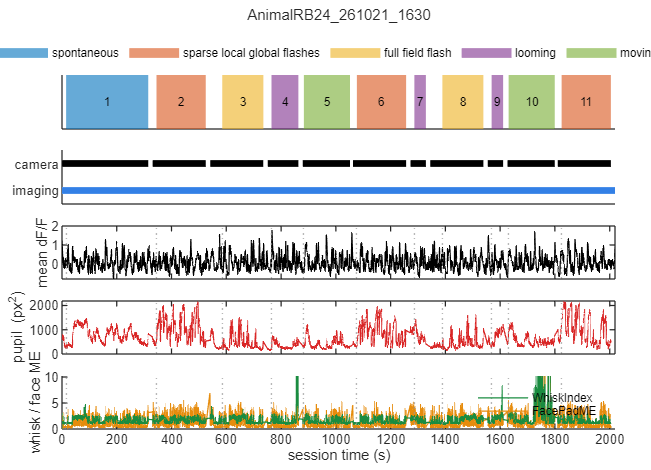

types  = unique(b_type, 'stable');
tcols  = lines(numel(types));
[~, tix] = ismember(b_type, types);

fh = newfig('Session overview', 18, 13);
tl = tiledlayout(fh, 5, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl, strrep(session, '_', '\_'), 'FontSize', 9, 'FontWeight', 'normal');
ax(1) = nexttile(tl);  hold on;
tp = gobjects(numel(types), 1);
for k = 1:nB
    if b_pre(k) > 0 || b_post(k) > 0        % recorded grey screens around the block, lighter than the stimulus
        patch([b_a0(k) b_a1(k) b_a1(k) b_a0(k)], [0 0 1 1], tcols(tix(k), :), 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    end
    tp(tix(k)) = patch([b_t0(k) b_t1(k) b_t1(k) b_t0(k)], [0 0 1 1], tcols(tix(k), :), 'FaceAlpha', 0.6, 'EdgeColor', 'none');
    blab = sprintf('%d', k);  if bracketed && ~isempty(b_dir{k}); blab = sprintf('%d%s', k, upper(b_dir{k}(1))); end         % 4E = expanding, 6R = receding disc
    text(mean([b_t0(k) b_t1(k)]), 0.5, blab, 'HorizontalAlignment', 'center', 'FontSize', 7);
end
ylim([0 1]);  yticks([]);  legend(tp, strrep(types, '_', ' '), 'Orientation', 'horizontal', 'Location', 'northoutside', 'FontSize', 7);
ax(2) = nexttile(tl);  hold on;
if has_beh
    seg_s = [tcam(1) tcam(gi + 1)];  seg_e = [tcam(gi) tcam(end)];
    for j = 1:numel(seg_s); plot([seg_s(j) seg_e(j)], [1 1], 'k', 'LineWidth', 4); end
end
plot([tCa(1) tCa(end)], [0 0], 'Color', [0.2 0.5 0.9], 'LineWidth', 4);
ylim([-0.5 1.5]);  yticks([0 1]);  yticklabels({'imaging', 'camera'});
ax(3) = nexttile(tl);  plot(tCa, movmean(mean(dFF, 1), round(fs)), 'Color', col.dff);  ylabel('mean dF/F');
ax(4) = nexttile(tl);
if has_beh && isfield(data.Behav, 'PupilArea'); plot(tcam, data.Behav.PupilArea, 'Color', col.pupil); end
ylabel('pupil (px^2)');
ax(5) = nexttile(tl);  hold on;  h_face = gobjects(0);  h_whisk = gobjects(0);
if has_beh && isfield(data.Behav, 'FacePadME'); h_face = plot(tcam, data.Behav.FacePadME, 'Color', col.face); end          % drawn first, whisking on top
if has_beh && isfield(data.Behav, 'WhiskIndex'); h_whisk = plot(tcam, data.Behav.WhiskIndex, 'Color', col.whisk); end
ax5_lines = [h_whisk, h_face];
ylabel('whisk / face ME');  xlabel('session time (s)');
if has_beh && all(isfield(data.Behav, {'WhiskIndex', 'FacePadME'}))
    ylim([0 1.5 * prctile([data.Behav.WhiskIndex(:); data.Behav.FacePadME(:)], 99.5)]);          % a few movement spikes would flatten everything else
    legend(ax5_lines, {'WhiskIndex', 'FacePadME'}, 'Location', 'northeast', 'FontSize', 7);
end
for a = 3:5; xline(ax(a), b_t0, 'Color', [0.6 0.6 0.6], 'LineStyle', ':', 'HandleVisibility', 'off'); end
linkaxes(ax, 'x');  xlim(ax(1), [tCa(1) tCa(end)]);
set(ax(1:4), 'XTickLabel', []);  set(ax(1:2), 'XTick', []);

if save_figs; savef(fh, '01_overview'); end

## 5. ROI signal quality (checks; the figures are in part C)

% Noise-referenced metrics (the pipeline dFF has median ~0 and std ~0.7 for pure noise, see header):
%   hf_noise   : per-frame noise = MAD of diff(dFF)/sqrt(2); events are slow compared with one frame, so they barely enter it
%   slow_ratio : var(smoothed dFF) / (hf_noise^2 / n_smooth) = variance of the smoothed trace relative to what white noise of
%                that per-frame level would leave after smoothing. White noise = 1 (checked by simulation), slow transients >> 1.
%                Independent of the dF/F scale, so bright ROIs with small relative events are not penalised.
%   sig_neg    : noise sigma of the smoothed trace measured on the LOWER half only (calcium events only go up)
%   snr_slow   : (p99.9 - median)/sig_neg of the smoothed trace (Gaussian noise alone gives 3.1); reported, not used for the verdict
%   ev_pos / ev_neg : upward crossings of +3*sig_neg vs downward crossings of -3*sig_neg; events go up, so ev_pos >> ev_neg
%                that is how a real transient differs from a dip (motion) or from symmetric noise
Fc    = F - neuropil_factor * Fneu;
w_sm  = max(1, round(smooth_s * fs));
dsm   = movmean(dFF, w_sm, 2);
med_s = median(dsm, 2);
dev   = dsm - med_s;
neg   = dev < 0;
sig_neg  = max(sqrt(sum(dev.^2 .* neg, 2) ./ max(sum(neg, 2), 1)), eps('single'));
snr_slow = (prctile(dsm, 99.9, 2) - med_s) ./ sig_neg;
dd       = diff(dFF, 1, 2);
hf_noise = 1.4826 * median(abs(dd - median(dd, 2)), 2) / sqrt(2);
slow_ratio = var(dsm, 0, 2) ./ (hf_noise .^ 2 / w_sm);
up = dev >  3 * sig_neg;  dn = dev < -3 * sig_neg;
ev_pos = sum(diff([false(nROI, 1) up], 1, 2) == 1, 2);
ev_neg = sum(diff([false(nROI, 1) dn], 1, 2) == 1, 2);
frac_Fc_le0 = mean(Fc <= 0, 2);

% does the stored dFF follow from the stored F / Fneu / baseline with the settings above?
rows = 1:min(nROI, 30);
Fcr  = double(Fc(rows, :)) - double(F0(rows, :));
win_med = 2 * ceil(dff_window_s / median(dtc)) + 1;
den  = movmedian(Fcr, win_med, 2);
dFF_re = Fcr ./ den - 1;
re_err = median(abs(dFF_re - double(dFF(rows, :))), 2);
chk = addchk(chk, 'dFF: reproduces from F/Fneu/baseline', grade(max(re_err) < 1e-3, 1), sprintf('median |recomputed - stored| <= %.1e (neuropil %.2f, +-%g s). Larger = other settings were used', max(re_err), neuropil_factor, dff_window_s));
den_bad = false(nROI, 1);  den_bad(rows) = any(den <= 0, 2);
chk = addchk(chk, 'dFF: denominator > 0', grade(~any(den_bad), 1), sprintf('%d ROIs with movmedian(Fc - baseline) <= 0 (dF/F sign flips / explodes): %s', sum(den_bad), lst(find(den_bad)')));
chk = addchk(chk, 'F: neuropil over-subtraction', grade(~any(frac_Fc_le0 > 0.01), 1), sprintf('%d ROIs with Fc = F - %.1f*Fneu <= 0 in >1%% of frames: %s', sum(frac_Fc_le0 > 0.01), neuropil_factor, lst(find(frac_Fc_le0 > 0.01)')));

bad_F       = frac_Fc_le0 > 0.01 | den_bad;
noise_like  = slow_ratio < slow_ratio_thr | ev_pos < 2 * max(ev_neg, 1);
signal_like = ~bad_F & ~noise_like;
roiq = table((1:nROI)', cent(:, 1), cent(:, 2), arrayfun(@(c) c.npix, ca.Ca_cellstats(:)), median(F, 2), median(Fneu, 2), median(F0, 2), 100*frac_Fc_le0, ...
    std(dFF, 0, 2), skewness(double(dFF), 0, 2), hf_noise, slow_ratio, snr_slow, ev_pos, ev_neg, ev_pos / (nT/fs/60), signal_like, ...
    'VariableNames', {'roi','y','x','npix','F_med','Fneu_med','F0_med','pct_Fc_le0','std_dff','skew','hf_noise','slow_ratio','snr_slow','ev_pos','ev_neg','ev_per_min','signal_like'});
disp(roiq);

    roi     y      x     npix    F_med     Fneu_med    F0_med     pct_Fc_le0    std_dff     skew      hf_noise    slow_ratio    snr_slow    ev_pos    ev_neg    ev_per_min    signal_like
    ___    ___    ___    ____    ______    ________    _______    __________    _______    _______    ________    __________    ________    ______    ______    __________    ___________

     1     276    419     183    43.265     18.01

chk = addchk(chk, 'ROIs: signal-like', grade(sum(signal_like) >= max(3, 0.25 * nROI), 1), sprintf('%d/%d ROIs pass (slow_ratio >= %g, ev_pos >= 2*ev_neg, Fc > 0 in >99%% of frames). Noise-like: %s; neuropil-limited: %s', sum(signal_like), nROI, slow_ratio_thr, lst(find(noise_like & ~bad_F)'), lst(find(bad_F)')));
chk = addchk(chk, 'ROIs: pure-noise std level', grade(true, 1), sprintf('median std(dFF) %.2f (pure noise gives ~0.71 under this dF/F definition), median per-frame noise %.2f', median(std(dFF, 0, 2)), median(hf_noise)));
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] dFF: reproduces from F/Fneu/baseline median |recomputed - stored| <= 3.0e-08 (neuropil 0.50, +-15 s). Larger = other settings were used
  [PASS] dFF: denominator > 0                 0 ROIs with movmedian(Fc - baseline) <= 0 (dF/F sign flips / explodes): []
  [WARN] F: neuropil over-subtraction         3 ROIs with Fc = F - 0.5*Fneu <= 0 in >1% of frames: [13 15 16]
  [PASS] ROIs: signal-like                    20/27 ROIs pass (slow_ratio >= 4, ev_pos >= 2*ev_neg, Fc > 0 in >99% of frames). Noise-like: [12 17 19 22]; neuropil-limited: [13 15 16]
  [PASS] ROIs: pure-noise std level           median std(dFF) 0.80 (pure noise gives ~0.71 under this dF/F definition), median per-frame noise 0.63


## 6. Registration offset, FOV-wide events, drift and motion (checks; the figures are in part C)

% 6a. suite2p crops max_proj to the valid registered area, while ROI pixel coordinates (ypix/xpix, centroids) are in full-frame
% coordinates. Overlaying them directly shifts every ROI. The shift is found by maximising the mean Img_max intensity under the ROI pixels.
off = [0 0];  pl_rois = [];  yp = {};  xp = {};
if has_img
    pl_i = min(plane_show, numel(planes));
    im   = double(data.Img_max{pl_i, 1});  [Ly, Lx] = size(im);
    pl_rois = find(cent(:, 3) == planes(pl_i))';
    cs   = ca.Ca_cellstats;
    yp = cell(numel(pl_rois), 1);  xp = yp;
    for j = 1:numel(pl_rois); yp{j} = double(cs(pl_rois(j)).ypix(:)); xp{j} = double(cs(pl_rois(j)).xpix(:)); end
    allY = vertcat(yp{:});  allX = vertcat(xp{:});
    pick = round(linspace(1, numel(allY), min(numel(allY), 20000)));
    sy = allY(pick);  sx = allX(pick);
    shifts = -25:25;
    reg_score = nan(numel(shifts));
    for a = 1:numel(shifts)
        for b = 1:numel(shifts)
            yy = sy + 1 + shifts(a);  xx = sx + 1 + shifts(b);          % +1: suite2p pixels are 0-based
            okp = yy >= 1 & yy <= Ly & xx >= 1 & xx <= Lx;
            if mean(okp) > 0.9; reg_score(a, b) = mean(im(sub2ind([Ly Lx], yy(okp), xx(okp)))); end
        end
    end
    [mx, ix] = max(reg_score(:));  [ia, ib] = ind2sub(size(reg_score), ix);
    auto_off = [shifts(ia) shifts(ib)];
    score0   = reg_score(shifts == 0, shifts == 0);
    if ischar(roi_img_offset); off = auto_off; else; off = roi_img_offset; end
    full_sz  = [NaN NaN];
    if has_si; full_sz = double([data.SI_Info.hRoiManager.linesPerFrame data.SI_Info.hRoiManager.pixelsPerLine]); end
    chk = addchk(chk, 'ROI map: Img_max registration', grade(all(auto_off == 0) || mx / score0 > 1.05, 1), ...
        sprintf('Img_max %dx%d (frame %dx%d); ROI pixels land best at shift dy=%d dx=%d, mean intensity under ROIs %.1f vs %.1f unshifted (x%.2f); using [%d %d]', Ly, Lx, full_sz(1), full_sz(2), auto_off(1), auto_off(2), mx, score0, mx / score0, off(1), off(2)));
end

% 6b. FOV-wide events (many ROIs up at the same time) are typically motion, neuropil or arousal, not single-axon activity.
sl = find(signal_like)';  if numel(sl) < 3; sl = 1:nROI; end
co = mean(up(sl, :), 1);                                    % fraction of (signal-like) ROIs above +3 sigma at each frame
null_co = zeros(1, n_perm);
for p = 1:n_perm
    sh = randi([round(30*fs), nT - round(30*fs)], numel(sl), 1);
    idx = mod((0:nT-1) + sh, nT) + 1;                       % independent circular shift per ROI
    null_co(p) = max(mean(up(sub2ind(size(up), repmat(sl(:), 1, nT), idx)), 1));
end
co_thr = max(0.4, 1.2 * max(null_co));
g_on   = find(diff([0 co >= co_thr]) == 1);
if ~isempty(g_on); g_on = g_on([true, diff(tCa(g_on)) > 1]); end    % merge events closer than 1 s
g_t    = tCa(g_on);
g_blk  = arrayfun(@(t) find(t >= b_a0 & t <= b_a1, 1), g_t, 'UniformOutput', false);
g_blk(cellfun(@isempty, g_blk)) = {0};
chk = addchk(chk, 'population: FOV-wide events', grade(numel(g_t) <= 3, 1), sprintf('%d events with >= %.0f%% of %d ROIs up together (chance max %.0f%%), at s: %s (blocks %s)', numel(g_t), 100*co_thr, numel(sl), 100*max(null_co), lst(round(g_t(1:min(end, 12)))), lst(cell2mat(g_blk(1:min(end, 12))))));
ev_in_glob = nan(nROI, 1);
for r = 1:nROI
    on_t = tCa(diff([0 up(r, :)]) == 1);
    if ~isempty(on_t) && ~isempty(g_t); ev_in_glob(r) = mean(min(abs(on_t(:) - g_t(:)'), [], 2) <= 1); elseif ~isempty(on_t); ev_in_glob(r) = 0; end
end
chk = addchk(chk, 'population: events during FOV-wide events', grade(~(median(ev_in_glob(signal_like), 'omitnan') > 0.3), 1), sprintf('median %.0f%% of signal-like ROI events fall within 1 s of a FOV-wide event', 100*median(ev_in_glob(signal_like), 'omitnan')));

% correlation between ROIs (smoothed dFF): ROIs on the same axon share their events (r close to 1) and are NOT independent samples
ids = sl;  if numel(ids) < 3; ids = 1:min(nROI, 300); end
[~, so] = sort(slow_ratio(ids), 'descend');  ids = ids(so);
Cm = corrcoef(double(dsm(ids, :))');
px_um = NaN;  if has_si; px_um = abs(diff(data.SI_Info.hRoiManager.imagingFovUm([1 2]))) / data.SI_Info.hRoiManager.pixelsPerLine; end
[pa, pb] = find(triu(Cm > 0.8, 1));
pair_d = hypot(cent(ids(pa), 1) - cent(ids(pb), 1), cent(ids(pa), 2) - cent(ids(pb), 2));
chk = addchk(chk, 'ROIs: strongly correlated pairs', grade(isempty(pa), 1), sprintf('%d of %d pairs among the %d signal-like ROIs have r > 0.8 (same axon / shared signal, not independent); median centroid distance %.0f px = %.0f um', numel(pa), numel(ids)*(numel(ids)-1)/2, numel(ids), median(pair_d), median(pair_d) * px_um));
if ~isempty(pa)
    pr = Cm(sub2ind(size(Cm), pa, pb));  [~, po] = sort(pr, 'descend');  po = po(1:min(10, numel(po)));
    disp(table(ids(pa(po))', ids(pb(po))', pr(po), pair_d(po), 'VariableNames', {'roiA','roiB','r','dist_px'}));
end

    roiA    roiB       r       dist_px
    ____    ____    _______    _______

     25      24     0.97634    45.188 
     23      24     0.95068    72.367 
     25      23     0.94277     75.69 
     25      27      0.9353    126.24 
     24      27     0.92582    97.082 
     23      27     0.90946    67.912 
     26       3     0.88949    164.73 
     25      14     0.88508    86.533 
     27      18     0.88449    9.4868 
     23      14     0.88301    17.464 




% bleaching / drift of the raw ROI fluorescence (median per minute, relative to the first minute)
bn = round(60 * fs);  nb = floor(nT / bn);
Fb = reshape(median(reshape(double(Fc(:, 1:nb*bn)), nROI, bn, nb), 2), nROI, nb);
Fb_rel = Fb ./ Fb(:, 1);  Fb_rel(Fb(:, 1) <= 0, :) = NaN;
drift_pct = 100 * (median(Fb_rel(:, end), 'omitnan') - 1);
chk = addchk(chk, 'F: drift over session', grade(abs(drift_pct) < 30, 1), sprintf('median ROI Fc changes %.0f%% from first to last minute (bleaching / z-drift)', drift_pct));

% 6c. motion (optional: needs suite2p Fall.mat, not stored in the aggregated file)
% Rigid shift = ops.xoff/yoff, non-rigid deformation = spread of the block shifts ops.xoff1/yoff1. ROIs whose dFF follows motion are not axon signal.
motion_r = nan(nROI, 2);  mot_flag = false(nROI, 1);  have_motion = false;
fall_file = fullfile(s2p_dir, 'Fall.mat');
if isfile(fall_file)
    o   = load(fall_file, 'ops');  ops = o.ops;
    xo  = double(ops.xoff(:))';  yo = double(ops.yoff(:))';
    len_ok = numel(xo) == nT;
    chk = addchk(chk, 'motion: ops length', grade(len_ok, 1), sprintf('%d motion samples vs %d frames', numel(xo), nT));
    if len_ok
        have_motion = true;
        rigid = hypot(xo - median(xo), yo - median(yo));
        nonr  = hypot(std(double(ops.xoff1), 0, 2), std(double(ops.yoff1), 0, 2))';
        bad_f = false(1, nT);  if isfield(ops, 'badframes'); bad_f = logical(ops.badframes(:))'; end
        mot_lim_px = 1 / px_um;  if ~isfinite(mot_lim_px); mot_lim_px = 6; end             % 1 um, about the width of an axon
        chk = addchk(chk, 'motion: rigid shift', grade(prctile(rigid, 99) < mot_lim_px, 1), sprintf('p99 %.1f px = %.2f um, max %.1f px (x %d..%d, y %d..%d px); WARN above %.1f px (1 um); %.2f%% frames flagged bad by suite2p', prctile(rigid, 99), prctile(rigid, 99) * px_um, max(rigid), min(xo), max(xo), min(yo), max(yo), mot_lim_px, 100*mean(bad_f)));
        mots = {rigid, nonr};  mot_names = {'rigid', 'non-rigid'};
        null_r = zeros(nROI, n_perm, 2);
        for m = 1:2
            mv = movmean(mots{m}, w_sm);
            mz = (mv - mean(mv)) / std(mv);
            dz = (double(dsm) - mean(double(dsm), 2)) ./ std(double(dsm), 0, 2);
            motion_r(:, m) = dz * mz' / (nT - 1);
            for p = 1:n_perm
                null_r(:, p, m) = dz * circshift(mz, randi([round(30*fs), nT - round(30*fs)]))' / (nT - 1);
            end
        end
        thr99 = squeeze(prctile(abs(null_r), 99, 2));                              % [nROI x 2]
        mot_flag = any(abs(motion_r) > max(thr99, mot_r_thr), 2);
        chk = addchk(chk, 'motion: ROIs coupled to motion', grade(~any(mot_flag & signal_like), 1), sprintf('%d ROIs follow rigid / non-rigid motion beyond shuffle (|r| > shuffle p99 and > %.2f); %d of them signal-like: %s. Median |r| rigid %.2f, non-rigid %.2f', sum(mot_flag), mot_r_thr, sum(mot_flag & signal_like), lst(find(mot_flag & signal_like)'), median(abs(motion_r(:, 1))), median(abs(motion_r(:, 2)))));
    end
else
    chk = addchk(chk, 'motion: suite2p ops', grade(false, 1), sprintf('not checked: %s not found', fall_file));
end
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] ROI map: Img_max registration        Img_max 494x1008 (frame 512x1024); ROI pixels land best at shift dy=-10 dx=-7, mean intensity under ROIs 51.1 vs 38.8 unshifted (x1.32); using [-10 -7]
  [WARN] population: FOV-wide events          65 events with >= 42% of 20 ROIs up together (chance max 35%), at s: [0 23 40 158 199 220 227 318 407 470 575 581] (blocks [0 1 1 1 1 1 1 0 2 2 0 0])
  [WARN] population: events during FOV-wide events median 46% of signal-like ROI events fall within 1 s of a FOV-wide event
  [WARN] ROIs: strongly correlated pairs      23 of 190 pairs among the 20 signal-like ROIs have r > 0.8 (same axon / shared signal, not independent); median centroid distance 97 px = 15 um
  [PASS] F: drift over session                median ROI Fc changes -25% from first to last minute (bleaching / z-drift)
  [PASS] motion: ops length                   60574 motion samples vs 60574 frames
  [PASS] motion: rigid shift                  p99 5.8 px = 0.90 um, max 12.8 px (x -5..8

## 7. ROI selection

% Everything in part B (figures, correlation table) uses sel_roi. Part A stays on all ROIs so the checks are unchanged.
good_roi = find(signal_like & ~mot_flag)';
if ischar(roi_sel) || isstring(roi_sel)
    switch lower(char(roi_sel))
        case 'all';  sel_roi = 1:nROI;
        case 'good'; sel_roi = good_roi;
        otherwise;   error('roi_sel must be ''all'', ''good'' or a list of ROI numbers');
    end
else
    sel_roi = unique(double(roi_sel(:)'));
    assert(all(sel_roi >= 1 & sel_roi <= nROI & sel_roi == round(sel_roi)), 'roi_sel: ROI numbers must be integers between 1 and %d', nROI);
end
assert(~isempty(sel_roi), 'roi_sel selects no ROIs (''good'' found none: check the part A output)');
nSel = numel(sel_roi);
flagged = sel_roi(noise_like(sel_roi) | bad_F(sel_roi) | mot_flag(sel_roi));
chk = addchk(chk, 'ROI selection', grade(isempty(flagged) || ischar(roi_sel) || isstring(roi_sel), 1), ...
    sprintf('%d/%d ROIs selected (roi_sel = %s): %s. Flagged by the checks (noise-like / Fc<=0 / motion-coupled): %s', nSel, nROI, strtrim(evalc('disp(roi_sel)')), lst(sel_roi), lst(flagged)));
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] ROI selection                        8/27 ROIs selected (roi_sel = good): [9 18 20 21 23 24 25 27]. Flagged by the checks (noise-like / Fc<=0 / motion-coupled): []



% ROI groups: one axon branching over the field gives several ROIs with the same signal (r > 0.9 for the bundle), which are not independent samples.
% sel_roi is clustered on the correlation of the smoothed dF/F (average linkage, cut at 1 - grp_r_thr); group 1 = the largest group. Sections 9b, 9c
% and part D (12-16) use the group means.
[gid, grp_rois] = roi_groups(dsm, sel_roi, grp_r_thr);
ng       = numel(grp_rois);
grp_lab  = cellfun(@(r) ['ROI ' regexprep(num2str(r), '\s+', ',')], grp_rois, 'UniformOutput', false);
grp_mean = cell2mat(cellfun(@(r) mean(double(dFF(r, :)), 1), grp_rois(:), 'UniformOutput', false));     % [ng x nT]
gcol     = lines(ng);  gcol(1, :) = [0 0 0];

## 8. Stimulus chunking: trials of every stimulus type present

% Onsets: Frameinfo.subtrial_frame_count==1 (FFF, looming, moving bar); flash onsets and moving-bar directions by RNG replay
% (analysis_functions/get_flash_onsets, reconstruct_direction_order). Blocks of the same type are pooled; V2's  trials = frames / n  is gone.
% Reliability = mean pairwise correlation between trials (per direction for the bar), tested against independently circularly
% shifted trials (n_perm). With nROI ROIs, p < 0.01 is expected for ~1% of them by chance. Computed for all ROIs; the figures use sel_roi.
dFFd = double(dFF);
stim_types = {'full_field_flash', 'looming', 'moving_bar', 'sparse_local_global_flashes'};
win  = struct('full_field_flash', [-2 32], 'looming', [-2 8], 'moving_bar', [-1 6], 'sparse_local_global_flashes', [-1 4]);
bwin = struct('full_field_flash', [0 2],   'looming', [-2 0], 'moving_bar', [-1 0], 'sparse_local_global_flashes', [-1 0]);
awin = struct('full_field_flash', [2 32],  'looming', [0 8],  'moving_bar', [0.5 4], 'sparse_local_global_flashes', [0 2]);   % window of the evoked amplitude (section 9 exploration figures)
for q = {'looming_expand', 'looming_recede'}       % the bracketed design analyses the two disc directions separately, with the windows of looming
    win.(q{1}) = win.looming;  bwin.(q{1}) = bwin.looming;  awin.(q{1}) = awin.looming;
end
BZ   = nan(numel(beh_names), nT);                                                   % behaviour on the imaging grid, z-scored over the session
for si = 1:numel(beh_names); x = beh_ca.(beh_names{si}); BZ(si, :) = (x - mean(x, 'omitnan')) / std(x, 'omitnan'); end
other_types = setdiff(unique(b_type), [stim_types, {'spontaneous'}]);
chk = addchk(chk, 'stimulus: types analysed', grade(isempty(other_types), 1), sprintf('trial analysis for %s; no trial analysis for: %s', strjoin(intersect(stim_types, b_type, 'stable'), ', '), strjoin(other_types, ', ')));
resp = struct();
for ti = 1:numel(stim_types)
    ty = stim_types{ti};
    ks = find(strcmp(b_type, ty))';
    if isempty(ks); continue; end
    w = win.(ty);  n_com = round(diff(w) * fs) + 1;  tcom = linspace(w(1), w(2), n_com);
    Ca = [];  blk_of = [];  dir_of = [];  ons = [];
    for k = ks
        switch ty
            case 'moving_bar'
                [Cak, ~, dk] = extract_direction_trials(S(k), dFFd, tCa, ty, 'bar_orientations', -w(1), w(2), n_com);
                sfc = S(k).Frameinfo.subtrial_frame_count(~isnan(S(k).Frameinfo.frame_count));
                onk = S(k).TimeStimulusFrame(find(sfc == 1));
                [r_same, r_shift] = verify_direction_reconstruction(S(k), dFFd, tCa, ty, 'bar_orientations');
                chk = addchk(chk, sprintf('bar blk %d: direction order', k), grade(isnan(r_same) || r_same > r_shift + 0.05, 1), sprintf('RNG-replayed order: same-position corr %.2f vs shifted control %.2f (needs responsive ROIs to separate)', r_same, r_shift));
            case 'sparse_local_global_flashes'
                onk = get_flash_onsets(S(k));
                Cak = align_trials_to_onsets(onk, dFFd, tCa, -w(1), w(2), n_com);
                dk  = nan(1, numel(onk));
                gaps = diff([0; onk(:) - S(k).TimeStimulusFrame(1)]);  iv = S(k).specParams.interval;
                chk = addchk(chk, sprintf('flashes blk %d: onset timing', k), grade(all(gaps >= iv(1) - 2*S(k).ifi(1) & gaps <= iv(2) + 2*S(k).ifi(1)), 1), sprintf('%d flashes, gaps %.1f-%.1f s (specParams.interval %g-%g s)', numel(onk), min(gaps), max(gaps), iv(1), iv(2)));
            otherwise
                sfc = S(k).Frameinfo.subtrial_frame_count(~isnan(S(k).Frameinfo.frame_count));
                onk = S(k).TimeStimulusFrame(find(sfc == 1));
                Cak = align_trials_to_onsets(onk, dFFd, tCa, -w(1), w(2), n_com);
                dk  = nan(1, numel(onk));
                chk = addchk(chk, sprintf('%s blk %d: trial count', ty, k), grade(numel(onk) == S(k).trials, 1), sprintf('%d onsets, expected %d trials', numel(onk), S(k).trials));
                if strcmp(ty, 'looming')
                    PTb = data.Triggers.TimeProjector(data.Triggers.TimeProjector >= b_t0(k) - 1e-3 & data.Triggers.TimeProjector <= b_t1(k) + 1e-3);
                    if numel(PTb) == numel(onk)
                        chk = addchk(chk, sprintf('looming blk %d: onset = projector pulse', k), grade(max(abs(PTb(:) - onk(:))) < 0.005, 1), sprintf('max |onset - pulse| = %.1f ms', 1e3*max(abs(PTb(:) - onk(:)))));
                    end
                end
        end
        Ca = cat(3, Ca, Cak);  blk_of = [blk_of, repmat(k, 1, numel(onk))];  dir_of = [dir_of, dk(:)'];  ons = [ons; onk(:)]; %#ok<AGROW>
    end
    inwin = ons + w(1) >= tCa(1) & ons + w(2) <= tCa(end);
    chk = addchk(chk, sprintf('%s: trial windows', ty), grade(all(inwin), 1), sprintf('%d trials from %d block(s), %d windows reach outside the recording', numel(ons), numel(ks), sum(~inwin)));
    bidx = tcom >= bwin.(ty)(1) & tcom < bwin.(ty)(2);
    Cb   = Ca - mean(Ca(:, bidx, :), 2, 'omitnan');
    if strcmp(ty, 'moving_bar'); grp = findgroups(dir_of); else; grp = ones(1, numel(ons)); end
    [rel, p_rel] = trial_reliability(Cb, tcom, grp, n_perm);
    % the same onsets applied to the behaviour: a stimulus that makes the animal whisk / move will drive ROIs through arousal or motion
    Bal = [];  Braw = [];
    if ~isempty(beh_names)
        Bal = align_trials_to_onsets(ons, BZ, tCa, -w(1), w(2), n_com);              % [behaviour x time x trials]
        Braw = Bal;                                                                  % before the baseline subtraction: keeps the pre-stimulus state
        Bal = Bal - mean(Bal(:, bidx, :), 2, 'omitnan');
        ev_beh = mean(reshape(mean(Bal(:, tcom >= 0 & tcom <= 1, :), 2, 'omitnan'), numel(beh_names), []), 2, 'omitnan')';
        chk = addchk(chk, [ty ': stimulus-evoked behaviour'], grade(all(abs(ev_beh) < 0.3), 1), ['mean change in the 1 s after onset, in session SD: ' strjoin(arrayfun(@(i) sprintf('%s %+.2f', beh_names{i}, ev_beh(i)), 1:numel(beh_names), 'UniformOutput', false), ', ')]);
    end
    resp.(ty) = struct('Ca', Ca, 'Cb', Cb, 'Bal', Bal, 'Braw', Braw, 'tcom', tcom, 'blk', blk_of, 'dir', dir_of, 'onsets', ons, 'rel', rel, 'p', p_rel);
    sig = p_rel < 0.01;
    % a response shared by (almost) every ROI, flat ones included, points to something common (light from the stimulus, motion, neuropil)
    chk = addchk(chk, [ty ': response common to all ROIs?'], grade(mean(sig) < 0.8, 1), sprintf('%.0f%% of all ROIs and %.0f%% of the noise-like ROIs are reliable (p < 0.01)', 100*mean(sig), 100*mean(sig(noise_like & ~bad_F))));
    chk = addchk(chk, [ty ': reproducible ROIs'], grade(sum(sig) > max(1, 3 * 0.01 * nROI), 1), sprintf('%d/%d ROIs with trial-to-trial reliability p < 0.01 (chance ~%.1f); of those signal-like: %d. Median reliability r = %.2f. ROIs: %s', sum(sig), nROI, 0.01*nROI, sum(sig & signal_like), median(rel, 'omitnan'), lst(find(sig)')));
end

  [verify moving_bar] same-position corr = -0.125, shifted-position control = 0.124 (n_dir=8, n_repeats=3, n_cells=27) -- WARNING -- same-position correlation not clearly above shifted control, inspect manually
  [verify moving_bar] same-position corr = 0.380, shifted-position control = -0.166 (n_dir=8, n_repeats=3, n_cells=27) -- PASS (reconstruction looks correct)


% bracketed design: the two disc directions as own trial sets (resp.looming stays the pooled set for part D)
if bracketed && isfield(resp, 'looming')
    R0 = resp.looming;
    for tyc = {'looming_expand', 'looming_recede'}
        ty = tyc{1};
        m  = ismember(R0.blk, find(strcmp(b_stim, ty))');
        if ~any(m); continue; end
        R1 = R0;
        R1.Ca = R0.Ca(:, :, m);  R1.Cb = R0.Cb(:, :, m);  R1.blk = R0.blk(m);  R1.dir = R0.dir(m);  R1.onsets = R0.onsets(m);
        if ~isempty(R0.Bal); R1.Bal = R0.Bal(:, :, m);  R1.Braw = R0.Braw(:, :, m); end
        [R1.rel, R1.p] = trial_reliability(R1.Cb, R1.tcom, ones(1, nnz(m)), n_perm);
        resp.(ty) = R1;
        sig = R1.p < 0.01;
        chk = addchk(chk, [ty ': response common to all ROIs?'], grade(mean(sig) < 0.8, 1), sprintf('%.0f%% of all ROIs and %.0f%% of the noise-like ROIs are reliable (p < 0.01)', 100*mean(sig), 100*mean(sig(noise_like & ~bad_F))));
        chk = addchk(chk, [ty ': reproducible ROIs'], grade(sum(sig) > max(1, 3 * 0.01 * nROI), 1), sprintf('%d/%d ROIs with trial-to-trial reliability p < 0.01 (chance ~%.1f); of those signal-like: %d. Median reliability r = %.2f. ROIs: %s', sum(sig), nROI, 0.01*nROI, sum(sig & signal_like), median(R1.rel, 'omitnan'), lst(find(sig)')));
    end
    n_e = sum(strcmp(b_stim, 'looming_expand'));  n_r = sum(strcmp(b_stim, 'looming_recede'));
    chk = addchk(chk, 'looming: both disc directions', grade(n_e > 0 && n_r > 0, 1), sprintf('%d expanding block(s) %s, %d receding block(s) %s (section 9c compares them)', n_e, lst(find(strcmp(b_stim, 'looming_expand'))'), n_r, lst(find(strcmp(b_stim, 'looming_recede'))')));
end
resp_types = fieldnames(resp);
blocks_of  = @(f) find(strcmp(b_type, f) | strcmp(b_stim, f))';          % blocks that contribute to resp.(f)
disp(table(resp_types, cellfun(@(f) numel(blocks_of(f)), resp_types), cellfun(@(f) numel(resp.(f).onsets), resp_types), cellfun(@(f) sprintf('%g to %g s', win.(f)), resp_types, 'UniformOutput', false), ...
    'VariableNames', {'type', 'blocks', 'trials', 'window'}));

                 type                  blocks    trials        window    
    _______________________________    ______    ______    ______________

    {'full_field_flash'           }      2         10      {'-2 to 32 s'}
    {'looming'                    }      3         15      {'-2 to 8 s' }
    {'moving_bar'                 }      2         48      {'-1 to 6 s' }
    {'sparse_local_global_flashes'}      3         50      {'-1 to 4 s' }



printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] stimulus: types analysed             trial analysis for full_field_flash, looming, moving_bar, sparse_local_global_flashes; no trial analysis for: 
  [PASS] full_field_flash blk 3: trial count  5 onsets, expected 5 trials
  [PASS] full_field_flash blk 8: trial count  5 onsets, expected 5 trials
  [PASS] full_field_flash: trial windows      10 trials from 2 block(s), 0 windows reach outside the recording
  [PASS] full_field_flash: stimulus-evoked behaviour mean change in the 1 s after onset, in session SD: PupilArea -0.21, WhiskIndex -0.01, FacePadME +0.01, EyeLidOpening -0.01
  [PASS] full_field_flash: response common to all ROIs? 4% of all ROIs and 25% of the noise-like ROIs are reliable (p < 0.01)
  [WARN] full_field_flash: reproducible ROIs  1/27 ROIs with trial-to-trial reliability p < 0.01 (chance ~0.3); of those signal-like: 0. Median reliability r = 0.00. ROIs: [22]
  [PASS] looming blk 4: trial count           5 onsets, expected 5 trials
  [PASS] looming blk 4: onset =

## 9. One figure per stimulus type (selected ROIs)

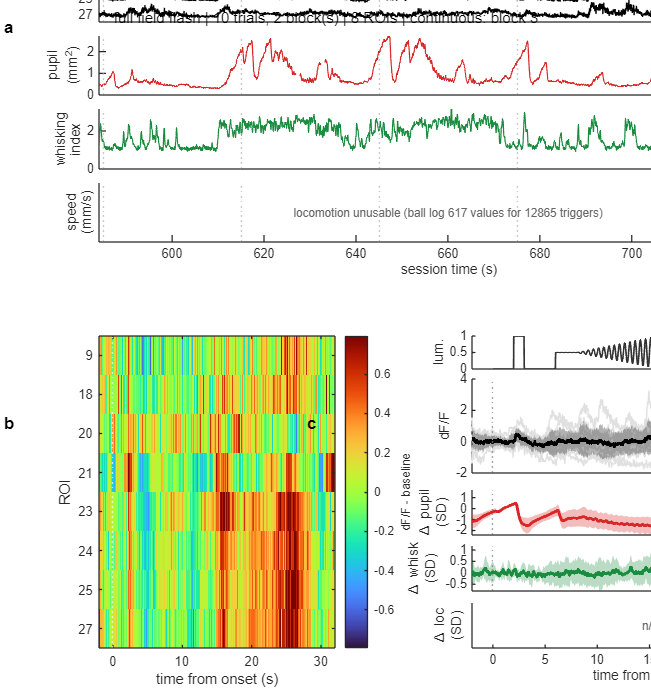

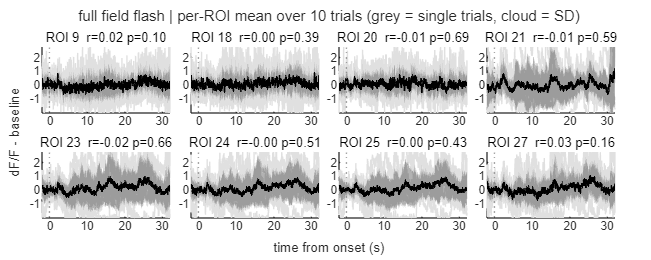

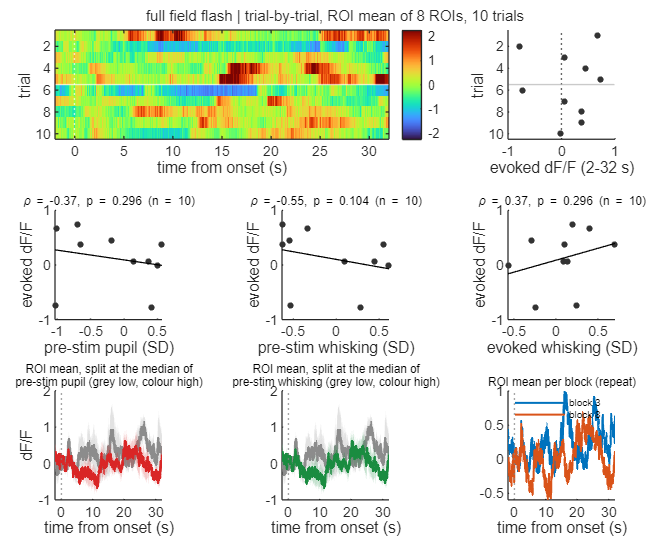

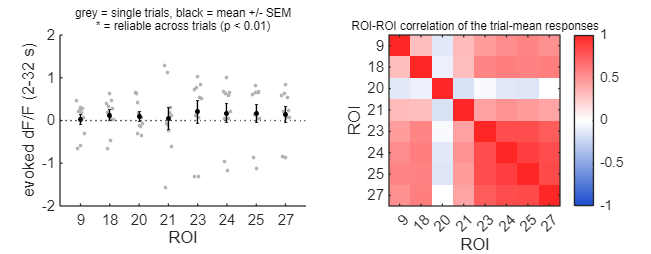

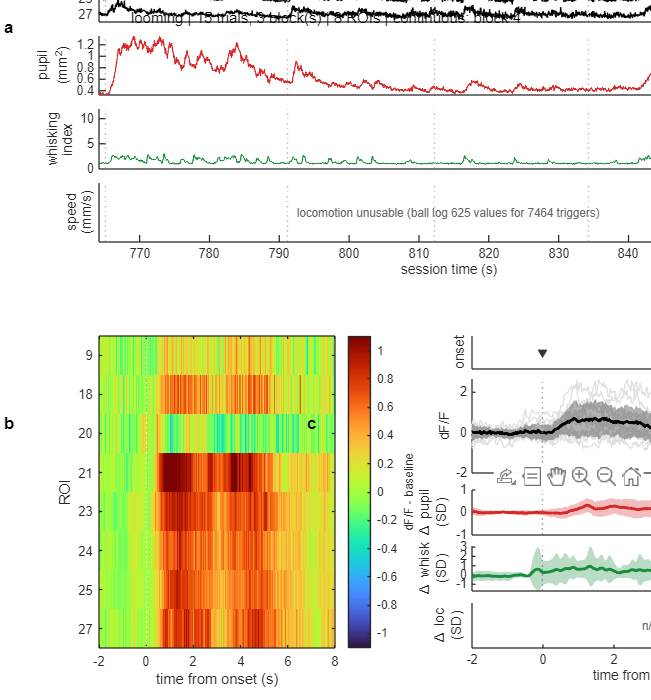

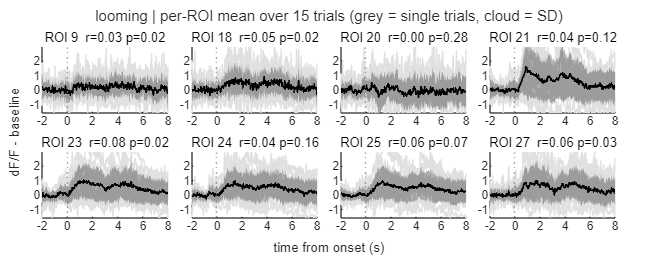

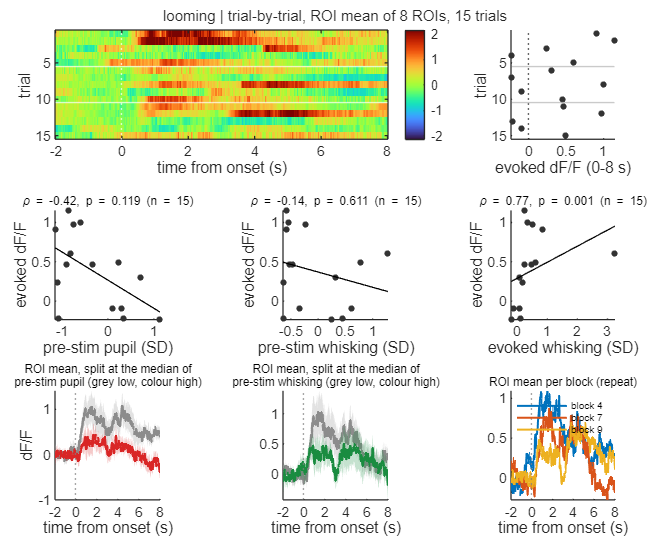

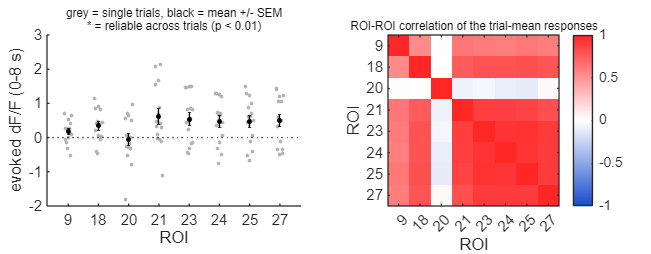

% top: stimulus, raw dF/F of every selected ROI, pupil, whisking, locomotion over the whole block show_block of that type
% bottom: trial-averaged heatmap (ROI x time from onset) and the ROI-mean response, thick line = mean over ALL repeats of the type,
% cloud = SD across repeats, grey = single repeats; below it the same onsets applied to pupil / whisking / locomotion (session SD)
pup_scale = 1;  pup_unit = 'px^2';
if has_beh && isfield(data, 'VideoParams') && isfield(data.VideoParams, 'Eye') && isfield(data.VideoParams.Eye, 'px_per_mm') && data.VideoParams.Eye.px_per_mm > 0
    pup_scale = 1 / data.VideoParams.Eye.px_per_mm ^ 2;  pup_unit = 'mm^2';
end
roi_lab = string(sel_roi);  roi_skip = max(1, ceil(nSel / 40));
FW = 18;  x0 = 2.1;
fig_types = resp_types;
if bracketed; fig_types = setdiff(resp_types, {'looming'}, 'stable'); end        % bracketed: expanding and receding discs get their own figures, pooled looming only feeds part D
for ti = 1:numel(fig_types)
    ty = fig_types{ti};  R = resp.(ty);
    ks = find(strcmp(b_stim, ty))';  kshow = ks(min(show_block, numel(ks)));
    tw = [max(tCa(1), b_a0(kshow) - 1), min(tCa(end), b_a1(kshow) + 1)];          % incl. the recorded grey screens of the block
    iw = tCa >= tw(1) & tCa <= tw(2);
    ons_k = R.onsets(R.blk == kshow);
    nTr = size(R.Cb, 3);

    h_st = 0.8;  h_roi = min(9, max(3, 0.3 * nSel));  h_b = 1.25;  g = 0.3;
    h_top = h_st + g + h_roi + g + 3 * (h_b + g);
    h_bot = 6.6;  mT = 0.9;  mid = 1.7;  mB = 1.1;
    FH = mT + h_top + mid + h_bot + mB;
    fh = newfig(['Stimulus: ' ty], FW, FH);
    annotation(fh, 'textbox', [0, 1 - 0.7 / FH, 1, 0.6 / FH], 'String', sprintf('%s | %d trials, %d block(s) | %d ROIs | continuous: block %d', strrep(ty, '_', ' '), nTr, numel(ks), nSel, kshow), ...
        'EdgeColor', 'none', 'HorizontalAlignment', 'center', 'FontName', 'Arial', 'FontSize', 9, 'Interpreter', 'none');
    wTop = FW - x0 - 1.1;  y = FH - mT;

    % stimulus
    y = y - h_st;  axs = axes('Units', 'centimeters', 'Position', [x0 y wTop h_st]);  hold on;
    if strcmp(ty, 'full_field_flash')
        [fb, ~] = mk_fff_curve(S(kshow), S(kshow).ifi(1), S(kshow).TimeStimulusFrame(1));
        nfr = round(S(kshow).stimulus_trial_t / S(kshow).ifi(1));
        fbv = fb(1:nfr+1);  fbv = fbv(:)';  no = numel(ons_k);
        xs = ons_k(:) + (0:nfr) * S(kshow).ifi(1);
        plot(reshape([xs, nan(no, 1)]', 1, []), reshape([repmat(fbv, no, 1), nan(no, 1)]', 1, []), 'Color', [0.2 0.2 0.2], 'LineWidth', 1);
        ylabel('lum.');
    else
        plot(repmat(ons_k(:)', 2, 1), repmat([0; 1], 1, numel(ons_k)), 'Color', [0.2 0.2 0.2], 'LineWidth', 1);
        ylim([0 1]);  yticks([]);  ylabel('onsets');
    end
    xlim(tw);  set(axs, 'XTick', []);
    y = y - g;

    % raw dF/F of every selected ROI
    X = dFFd(sel_roi, iw);
    ptp = prctile(X, [0.5 99.5], 2);  step = max(2, 1.2 * median(ptp(:, 2) - ptp(:, 1)));
    y = y - h_roi;  axr = axes('Units', 'centimeters', 'Position', [x0 y wTop h_roi]);  hold on;
    for j = 1:nSel; plot(tCa(iw), X(j, :) - median(X(j, :)) + (nSel - j) * step, 'Color', col.dff, 'LineWidth', 0.5); end
    sbar = max(1, round(step / 2));  xb = tw(2) + 0.008 * diff(tw);                          % scale bar just right of the axes
    plot(xb * [1 1], [0 sbar], 'k', 'LineWidth', 1.5, 'Clipping', 'off');
    text(xb + 0.008 * diff(tw), sbar / 2, sprintf('%g dF/F', sbar), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 7, 'Clipping', 'off');
    yticks((0:nSel-1) * step);  yticklabels(flip(roi_lab));  set(axr, 'FontSize', min(8, 8 - (nSel > 12)));
    xlim(tw);  ylim([-0.5 * step, (nSel - 0.3) * step + 0.5 * step]);  set(axr, 'XTick', []);  ylabel('raw dF/F, ROI');
    y = y - g;

    % behaviour: pupil, whisking, locomotion
    bnames = {'PupilArea', 'WhiskIndex', 'LocSpeed'};  bax = gobjects(1, 3);
    for q = 1:3
        y = y - h_b;  bax(q) = axes('Units', 'centimeters', 'Position', [x0 y wTop h_b]);  hold on;
        bq = bnames{q};  cc = beh_cmap.(bq);
        if strcmp(bq, 'LocSpeed')
            if loc_ok(kshow) && any(isfinite(loc_speed(iw)))
                plot(tCa(iw), loc_speed(iw), 'Color', cc);  ylabel({'speed', '(mm/s)'});
            else
                text(mean(tw), 0.5, sprintf('locomotion unusable (ball log %g values for %g triggers)', loc_n(kshow, 1), loc_n(kshow, 2)), 'HorizontalAlignment', 'center', 'FontSize', 7, 'Color', [0.4 0.4 0.4]);
                ylim([0 1]);  yticks([]);  ylabel({'speed', '(mm/s)'});
            end
        elseif has_beh && isfield(Bh, bq)
            ic = tcam >= tw(1) & tcam <= tw(2);
            v  = double(Bh.(bq)(:))';
            if strcmp(bq, 'PupilArea'); v = v * pup_scale;  ylabel({'pupil', ['(' pup_unit ')']}); else; ylabel({'whisking', 'index'}); end
            plot(tcam(ic), v(ic), 'Color', cc);
            if strcmp(bq, 'WhiskIndex'); ylim([0, 1.1 * max(1, prctile(v(ic), 99.7))]); end
        else
            text(mean(tw), 0.5, 'not available', 'HorizontalAlignment', 'center', 'FontSize', 7, 'Color', [0.4 0.4 0.4]);  yticks([]);  ylim([0 1]);
        end
        xlim(tw);
        if q < 3; set(bax(q), 'XTick', []); else; xlabel('session time (s)'); end
        y = y - g;
    end
    for a = [axr, bax]; xline(a, ons_k, ':', 'Color', [0.7 0.7 0.7], 'HandleVisibility', 'off'); end
    plabel(fh, FW, FH, 0.1, FH - mT + 0.3, 'a');

    % bottom left: trial-averaged heatmap
    ybot = mB;
    wH = 5.0;  ph = [x0 ybot wH h_bot];
    axh = axes('Units', 'centimeters', 'Position', ph);
    Mh = mean(R.Cb(sel_roi, :, :), 3, 'omitnan');
    imagesc(R.tcom, 1:nSel, Mh);  cm = max(0.5, prctile(abs(Mh(:)), 99));  clim([-cm cm]);  colormap(axh, turbo);
    cb = colorbar(axh);  cb.Label.String = 'dF/F - baseline';  cb.FontSize = 7;  set(axh, 'Units', 'centimeters', 'Position', ph);           % colorbar must not shrink the axes
    yticks(1:roi_skip:nSel);  yticklabels(roi_lab(1:roi_skip:nSel));  set(axh, 'FontSize', min(8, 8 - (nSel > 12)));
    xlabel('time from onset (s)');  ylabel('ROI');  xline(0, 'w:');
    plabel(fh, FW, FH, 0.1, ybot + h_bot + 0.1, 'b');

    % bottom right: stimulus marker, ROI-mean response, behaviour at the same onsets
    xR = x0 + wH + 2.9;  wR = FW - xR - 0.5;
    yr = ybot + h_bot;
    yr = yr - 0.7;  axs2 = axes('Units', 'centimeters', 'Position', [xR yr wR 0.7]);  hold on;
    if strcmp(ty, 'full_field_flash')
        plot((0:nfr) * S(kshow).ifi(1), fbv, 'Color', [0.2 0.2 0.2], 'LineWidth', 1);  ylabel('lum.');
    else
        plot(0, 0.5, 'v', 'Color', [0.2 0.2 0.2], 'MarkerFaceColor', [0.2 0.2 0.2], 'MarkerSize', 4);  ylim([0 1]);  yticks([]);  ylabel('onset');
    end
    xlim(R.tcom([1 end]));  set(axs2, 'XTick', []);
    yr = yr - 0.2 - 2.0;  axt = axes('Units', 'centimeters', 'Position', [xR yr wR 2.0]);
    Mt = reshape(mean(R.Cb(sel_roi, :, :), 1, 'omitnan'), numel(R.tcom), []);                 % [time x trials], ROI-mean per trial
    shade_trace(axt, R.tcom, Mt, col.dff, true);  xline(axt, 0, ':', 'Color', [0.5 0.5 0.5]);
    xlim(R.tcom([1 end]));  ylabel('dF/F');  set(axt, 'XTick', []);
    yr = yr - 0.35;
    for q = 1:3
        yr = yr - 0.95;  axq = axes('Units', 'centimeters', 'Position', [xR yr wR 0.95]);  hold on;
        bi = find(strcmp(beh_names, bnames{q}), 1);
        if ~isempty(R.Bal) && ~isempty(bi) && any(isfinite(R.Bal(bi, :, :)), 'all')
            shade_trace(axq, R.tcom, reshape(R.Bal(bi, :, :), numel(R.tcom), []), beh_cmap.(bnames{q}), false);
            xline(axq, 0, ':', 'Color', [0.5 0.5 0.5]);  ylabel({['\Delta ' beh_short.(bnames{q})], '(SD)'});
        else
            text(0.5, 0.5, 'n/a', 'Units', 'normalized', 'HorizontalAlignment', 'center', 'FontSize', 7, 'Color', [0.4 0.4 0.4]);  yticks([]);  ylabel({['\Delta ' beh_short.(bnames{q})], '(SD)'});
        end
        xlim(R.tcom([1 end]));
        if q < 3; set(axq, 'XTick', []); else; xlabel('time from onset (s)'); end
        yr = yr - 0.25;
    end
    plabel(fh, FW, FH, xR - 1.5, ybot + h_bot + 0.1, 'c');
    if save_figs; savef(fh, sprintf('02_%s', ty)); end

    if strcmp(ty, 'moving_bar')
        dirs = unique(R.dir);  amp = nan(nSel, numel(dirs));
        pk = R.tcom >= 0.5 & R.tcom <= 4;
        for d = 1:numel(dirs); amp(:, d) = mean(mean(R.Cb(sel_roi, pk, R.dir == dirs(d)), 2, 'omitnan'), 3, 'omitnan'); end
        fh = newfig('Moving bar tuning', 9, 4 + 0.2 * nSel);
        pd = [1.7 1.1 5.4 2.2 + 0.2 * nSel];
        axd = axes('Units', 'centimeters', 'Position', pd);
        imagesc(1:numel(dirs), 1:nSel, amp);  clim([-1 1] * max(0.5, prctile(abs(amp(:)), 98)));  colormap(axd, turbo);
        cb = colorbar(axd);  cb.Label.String = 'dF/F, 0.5-4 s';  cb.FontSize = 7;  set(axd, 'Units', 'centimeters', 'Position', pd);
        xticks(1:numel(dirs));  xticklabels(string(dirs));  yticks(1:roi_skip:nSel);  yticklabels(roi_lab(1:roi_skip:nSel));
        xlabel('bar direction (deg, RNG-reconstructed)');  ylabel('ROI');  title('mean response after sweep onset', 'FontWeight', 'normal');
        if save_figs; savef(fh, '03_moving_bar_tuning'); end
    end

    % ---- exploration figures of this stimulus type: 02b per-ROI mean traces, 02c trial-by-trial + arousal state, 02d ROI summary
    if ~explore_figs; continue; end
    tcom = R.tcom;  nTr = size(R.Cb, 3);  nTc = numel(tcom);
    is_bar = strcmp(ty, 'moving_bar');
    Csel = R.Cb(sel_roi, :, :);                                                  % [nSel x time x trials], baseline-subtracted dF/F
    ia   = tcom >= awin.(ty)(1) & tcom <= awin.(ty)(2);
    Mtr  = reshape(mean(Csel, 1, 'omitnan'), nTc, nTr);                          % ROI mean of every trial [time x trials]
    A    = reshape(mean(Csel(:, ia, :), 2, 'omitnan'), nSel, nTr);               % evoked amplitude per ROI and trial
    amp_tr = mean(A, 1, 'omitnan');                                              % ... of the ROI mean
    dirs_x = unique(R.dir(~isnan(R.dir)));  dcols = hsv(max(1, numel(dirs_x))) * 0.85;
    trial_col = repmat([0.2 0.2 0.2], nTr, 1);
    if is_bar; [~, di] = ismember(R.dir(:), dirs_x);  trial_col = dcols(di, :); end    % moving bar: colour = direction
    edges = find(diff(R.blk) ~= 0) + 0.5;                                        % block boundaries on the trial axis

    % 02b: mean +/- SD of every selected ROI over the trials (moving bar: one mean trace per direction instead)
    nc = min(6, ceil(sqrt(1.4 * (nSel + is_bar))));  nr = ceil((nSel + is_bar) / nc);
    fh = newfig(['Per-ROI mean: ' ty], 18, 1.6 + 2.8 * nr);
    tl = tiledlayout(fh, nr, nc, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, sprintf('%s | per-ROI mean over %d trials (grey = single trials, cloud = SD)', strrep(ty, '_', ' '), nTr), 'FontSize', 9, 'FontWeight', 'normal');
    if is_bar; title(tl, sprintf('%s | per-ROI mean over the trials of each direction (0.3 s smoothing)', strrep(ty, '_', ' ')), 'FontSize', 9, 'FontWeight', 'normal'); end
    xlabel(tl, 'time from onset (s)', 'FontSize', 8);  ylabel(tl, 'dF/F - baseline', 'FontSize', 8);
    if is_bar                                                                    % per-direction means, smoothed (a direction has only a few trials)
        Md = nan(nSel, nTc, numel(dirs_x));
        for d = 1:numel(dirs_x); Md(:, :, d) = movmean(mean(Csel(:, :, R.dir == dirs_x(d)), 3, 'omitnan'), max(1, round(0.3 * fs)), 2); end
        yl = prctile(Md(:), [1 99]);
    else
        mu_all = mean(Csel, 3, 'omitnan');  sd_all = std(Csel, 0, 3, 'omitnan');
        yl = [prctile(mu_all(:) - sd_all(:), 1), prctile(mu_all(:) + sd_all(:), 99)];
    end
    yl = yl + 0.05 * diff(yl) * [-1 1];                                          % same y range in every panel
    for j = 1:nSel
        axj = nexttile(tl);  hold(axj, 'on');
        if is_bar
            for d = 1:numel(dirs_x); plot(axj, tcom, squeeze(Md(j, :, d)), 'Color', dcols(d, :), 'LineWidth', 0.9); end
        else
            shade_trace(axj, tcom, reshape(Csel(j, :, :), nTc, nTr), col.dff, true, 1);
        end
        xline(axj, 0, ':', 'Color', [0.5 0.5 0.5]);  xlim(axj, tcom([1 end]));  ylim(axj, yl);
        title(axj, sprintf('ROI %d  r=%.2f p=%.2f', sel_roi(j), R.rel(sel_roi(j)), R.p(sel_roi(j))), 'FontSize', 7, 'FontWeight', 'normal');
        set(axj, 'FontSize', 7);
    end
    if is_bar
        axl = nexttile(tl);  hold(axl, 'on');  hl = gobjects(1, numel(dirs_x));
        for d = 1:numel(dirs_x); hl(d) = plot(axl, nan, nan, 'Color', dcols(d, :), 'LineWidth', 1.5); end
        legend(axl, hl, compose('%g deg', dirs_x(:)'), 'Location', 'west', 'FontSize', 7);  axis(axl, 'off');
    end
    if save_figs; savef(fh, sprintf('02b_%s_per_roi', ty)); end

    % 02c: trial-by-trial. a/b: trials x time heatmap of the ROI mean and the evoked amplitude per trial; c-e: amplitude against the
    % arousal state (pre-stimulus pupil, pre-stimulus whisking, whisking evoked by the stimulus; Spearman); f-h: ROI mean split at the
    % median of that state, and per block (repeat). Pre-stimulus state = mean of the session-z-scored behaviour before onset.
    nBeh_ = numel(beh_names);
    bi_p = find(strcmp(beh_names, 'PupilArea'), 1);  bi_w = find(strcmp(beh_names, 'WhiskIndex'), 1);
    pre = nan(nBeh_, nTr);  evb = pre;
    if ~isempty(R.Bal)
        pre = reshape(mean(R.Braw(:, tcom < 0, :), 2, 'omitnan'), nBeh_, nTr);
        evb = reshape(mean(R.Bal(:, ia, :), 2, 'omitnan'), nBeh_, nTr);
    end
    x_pp = nan(1, nTr);  x_pw = x_pp;  x_ew = x_pp;
    if ~isempty(bi_p); x_pp = pre(bi_p, :); end
    if ~isempty(bi_w); x_pw = pre(bi_w, :);  x_ew = evb(bi_w, :); end
    fh = newfig(['Trials: ' ty], 18, 15);
    tl = tiledlayout(fh, 3, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, sprintf('%s | trial-by-trial, ROI mean of %d ROIs, %d trials', strrep(ty, '_', ' '), nSel, nTr), 'FontSize', 9, 'FontWeight', 'normal');
    axa = nexttile(tl, 1, [1 2]);
    imagesc(axa, tcom, 1:nTr, Mtr');  cmx = max(0.5, prctile(abs(Mtr(:)), 99));  clim(axa, [-cmx cmx]);  colormap(axa, turbo);  colorbar(axa);
    set(axa, 'YDir', 'reverse');  hold(axa, 'on');  xline(axa, 0, 'w:');
    if ~isempty(edges); yline(axa, edges, 'w-'); end
    ylabel(axa, 'trial');  xlabel(axa, 'time from onset (s)');
    axb = nexttile(tl, 3);  hold(axb, 'on');
    scatter(axb, amp_tr, 1:nTr, 14, trial_col, 'filled');  set(axb, 'YDir', 'reverse');  ylim(axb, [0.5 nTr + 0.5]);  xline(axb, 0, ':');
    if ~isempty(edges); yline(axb, edges, 'Color', [0.7 0.7 0.7]); end
    xlabel(axb, sprintf('evoked dF/F (%g-%g s)', awin.(ty)));  ylabel(axb, 'trial');
    xs = {x_pp, x_pw, x_ew};  xlb = {'pre-stim pupil (SD)', 'pre-stim whisking (SD)', 'evoked whisking (SD)'};
    for q = 1:3
        axq = nexttile(tl, 3 + q);  hold(axq, 'on');
        scatter(axq, xs{q}, amp_tr, 14, trial_col, 'filled');
        v = isfinite(xs{q}) & isfinite(amp_tr);
        if sum(v) >= 3; pf = polyfit(xs{q}(v), amp_tr(v), 1);  xx = [min(xs{q}(v)) max(xs{q}(v))];  plot(axq, xx, polyval(pf, xx), 'k-'); end
        xlabel(axq, xlb{q});  ylabel(axq, 'evoked dF/F');  title(axq, spear_str(xs{q}, amp_tr), 'FontSize', 7, 'FontWeight', 'normal');
    end
    ax6 = nexttile(tl, 7);  split_plot(ax6, tcom, Mtr, x_pp, col.pupil);
    title(ax6, {'ROI mean, split at the median of', 'pre-stim pupil (grey low, colour high)'}, 'FontSize', 7, 'FontWeight', 'normal');  xlabel(ax6, 'time from onset (s)');  ylabel(ax6, 'dF/F');
    ax7 = nexttile(tl, 8);  split_plot(ax7, tcom, Mtr, x_pw, col.whisk);
    title(ax7, {'ROI mean, split at the median of', 'pre-stim whisking (grey low, colour high)'}, 'FontSize', 7, 'FontWeight', 'normal');  xlabel(ax7, 'time from onset (s)');
    ax8 = nexttile(tl, 9);  hold(ax8, 'on');
    blks = unique(R.blk, 'stable');  bcols = lines(numel(blks));  hb = gobjects(1, numel(blks));
    for q = 1:numel(blks); hb(q) = plot(ax8, tcom, mean(Mtr(:, R.blk == blks(q)), 2, 'omitnan'), 'Color', bcols(q, :), 'LineWidth', 1.2); end
    xline(ax8, 0, ':', 'Color', [0.5 0.5 0.5]);  legend(ax8, hb, compose('block %d', blks(:)'), 'FontSize', 6, 'Location', 'best');
    title(ax8, 'ROI mean per block (repeat)', 'FontSize', 7, 'FontWeight', 'normal');  xlabel(ax8, 'time from onset (s)');
    for a = [ax6, ax7, ax8]; xlim(a, tcom([1 end])); end
    if save_figs; savef(fh, sprintf('02c_%s_trials', ty)); end

    % 02d: evoked amplitude of every ROI (single trials + mean +/- SEM) and how alike the ROIs respond (correlation of the trial means)
    fh = newfig(['ROI summary: ' ty], 18, 7);
    tl = tiledlayout(fh, 1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    axa = nexttile(tl);  hold(axa, 'on');
    jit = linspace(-0.12, 0.12, nTr);
    for j = 1:nSel; scatter(axa, j + jit, A(j, :), 5, [0.7 0.7 0.7], 'filled'); end
    errorbar(axa, 1:nSel, mean(A, 2, 'omitnan'), std(A, 0, 2, 'omitnan') ./ sqrt(nTr), 'k.', 'MarkerSize', 9, 'CapSize', 2);
    yline(axa, 0, ':');  xlim(axa, [0.3 nSel + 0.7]);  xticks(axa, 1:roi_skip:nSel);  xticklabels(axa, roi_lab(1:roi_skip:nSel));
    xlabel(axa, 'ROI');  ylabel(axa, sprintf('evoked dF/F (%g-%g s)', awin.(ty)));
    sigx = find(R.p(sel_roi) < 0.01)';
    if ~isempty(sigx); plot(axa, sigx, repmat(max(A(:)) * 1.03, size(sigx)), 'k*', 'MarkerSize', 4); end
    title(axa, {'grey = single trials, black = mean +/- SEM', '* = reliable across trials (p < 0.01)'}, 'FontSize', 7, 'FontWeight', 'normal');
    axb = nexttile(tl);
    if nSel >= 2
        imagesc(axb, corrcoef(mean(Csel, 3, 'omitnan')'));  axis(axb, 'image');  clim(axb, [-1 1]);  colormap(axb, div_cmap);  colorbar(axb);
        xticks(axb, 1:roi_skip:nSel);  xticklabels(axb, roi_lab(1:roi_skip:nSel));  yticks(axb, 1:roi_skip:nSel);  yticklabels(axb, roi_lab(1:roi_skip:nSel));
        if nSel > 12; xtickangle(axb, 90); end
        xlabel(axb, 'ROI');  ylabel(axb, 'ROI');  title(axb, 'ROI-ROI correlation of the trial-mean responses', 'FontSize', 7, 'FontWeight', 'normal');
    else
        axis(axb, 'off');
    end
    if save_figs; savef(fh, sprintf('02d_%s_roi_summary', ty)); end
end

## 9b. Spontaneous activity before vs after the looming (bracketed design)

% Every looming block is preceded and followed by a recorded grey screen (specParams.pre_grey_t / post_grey_t, 120 s each). Did the looming itself change
% the spontaneous axon activity? The last grey_win_s of the pre period (ending grey_gap_pre_s before the first disc) are compared with the first grey_win_s of
% the post period (starting grey_gap_post_s after the last stimulus frame). Both windows are cut into chunks of grey_chunk_s. Per chunk and unit (the ROI groups
% of section 7, plus the mean of all selected ROIs if there are several groups):
%   event rate        upward crossings of 3 SD of the lower half of the 0.5 s smoothed trace (as in section 5), per minute
%   SD of dF/F        fluctuation amplitude of the smoothed trace
%   time above 3 SD   fraction of the chunk above that threshold
%   raw F change      mean Fc = F - 0.5 Fneu relative to the mean of the pre window (dF/F is divided by a +-15 s running median, so a slow tonic
%                     shift is invisible in it); this one also contains bleaching / z-drift
% and the behaviour as covariates (whisking amplitude = WhiskIndex - 1, pupil, face motion, locomotion if usable).
% Per class of block (expanding / receding / all): delta = mean over the blocks of (mean post - mean pre); 95% CI from resampling chunks with replacement inside
% each window of each block; p from exchanging the pre / post labels of the chunks inside each block (two-sided). The test cannot tell the looming from time:
% 'ref_pre_halves' is the same delta between the second and the first half of the PRE window, when nothing happened in between, i.e. the scale of change
% that drift / arousal alone produce. 'delta_whisk_adj' repeats the test after removing what the chunk-wise whisking amplitude explains (linear fit over all
% chunks of all looming blocks), 'p_whisk_adj' is its p. There is no no-looming control block in this design.
loom_tbl = table();  cmp_tbl = table();
cls_col = struct('expand', [0.85 0.45 0.05], 'recede', [0.1 0.4 0.8]);        % colour of the disc direction in 9b / 9c (orange: expanding, blue: receding)
if bracketed
    rng(3);
    lm_lab = grp_lab;  lm_U = grp_mean;  lm_rois = grp_rois;                  % units: the ROI groups and, with several groups, the mean of all selected ROIs
    if ng > 1; lm_lab = [lm_lab, {'all selected'}]; lm_U = [lm_U; mean(dFFd(sel_roi, :), 1)]; lm_rois = [lm_rois, {sel_roi}]; end
    nU = size(lm_U, 1);
    % behaviour covariates, one value per chunk: whisking from the artifact-free Behav.WhiskAmp (WhiskIndex - 1, floored at 0, NaN on grooming frames) and WhiskOn,
    % averaged over the camera frames of the chunk; pupil, face motion and locomotion from the imaging grid (section 3)
    bh_sig = {};  bh_lab = {};  bh_cam = false(1, 0);
    if has_beh && isfield(data.Behav, 'WhiskAmp'); bh_sig{end+1} = double(data.Behav.WhiskAmp(:))';  bh_lab{end+1} = 'whisking amplitude';  bh_cam(end+1) = true; end
    if has_beh && isfield(data.Behav, 'WhiskOn');  bh_sig{end+1} = double(data.Behav.WhiskOn(:))';   bh_lab{end+1} = 'time whisking (fraction)';  bh_cam(end+1) = true; end
    if isfield(beh_ca, 'PupilArea');  bh_sig{end+1} = beh_ca.PupilArea * pup_scale;    bh_lab{end+1} = ['pupil (' pup_unit ')'];  bh_cam(end+1) = false; end
    if isfield(beh_ca, 'FacePadME');  bh_sig{end+1} = beh_ca.FacePadME;                bh_lab{end+1} = 'face motion';  bh_cam(end+1) = false; end
    if isfield(beh_ca, 'LocSpeed');   bh_sig{end+1} = beh_ca.LocSpeed;                 bh_lab{end+1} = 'locomotion (mm/s)';  bh_cam(end+1) = false; end
    nBh = numel(bh_sig);  wh_row = find(strcmp(bh_lab, 'whisking amplitude'), 1);
    ucol = [0 0 0; 0.5 0.5 0.5; 0 0.6 0.5; 0.6 0.25 0.65];                        % unit colours in figures 08 / 09 (the class colours are orange and blue)
end
if bracketed && isempty(lk)
    fprintf('9b skipped: no looming block has a recorded grey period before and after\n');
end
if bracketed && ~isempty(lk)
    nL = numel(lk);  nch = floor(grey_win_s / grey_chunk_s);
    lm_s   = movmean(lm_U, w_sm, 2);
    lm_dev = lm_s - median(lm_s, 2);
    lm_sig = sqrt(sum(lm_dev .^ 2 .* (lm_dev < 0), 2) ./ max(sum(lm_dev < 0, 2), 1));      % noise sigma from the lower half of the smoothed trace
    lm_up  = lm_dev > 3 * lm_sig;
    lm_ev  = [false(nU, 1), diff(lm_up, 1, 2) == 1];                                        % onsets of upward events
    lm_fc  = cell2mat(cellfun(@(r) mean(double(Fc(r, :)), 1), lm_rois(:), 'UniformOutput', false));          % raw corrected fluorescence of the unit
    % chunk values, dimensions [unit (or behaviour) x block x window (1 pre, 2 post) x chunk]
    ev_c = nan(nU, nL, 2, nch);  sd_c = ev_c;  act_c = ev_c;  fc_c = ev_c;  bh_c = nan(max(nBh, 1), nL, 2, nch);
    for i = 1:nL
        fc_ref = mean(lm_fc(:, tCa >= pre_w(i, 1) & tCa < pre_w(i, 2)), 2);
        for w = 1:2
            if w == 1; t_s = pre_w(i, 1); else; t_s = post_w(i, 1); end
            for c = 1:nch
                t_a = t_s + (c - 1) * grey_chunk_s;  t_b = t_s + c * grey_chunk_s;
                ic = tCa >= t_a & tCa < t_b;
                if nnz(ic) < 0.5 * grey_chunk_s * fs; continue; end
                ev_c(:, i, w, c)  = sum(lm_ev(:, ic), 2) * 60 / grey_chunk_s;
                sd_c(:, i, w, c)  = std(lm_s(:, ic), 0, 2);
                act_c(:, i, w, c) = mean(lm_up(:, ic), 2);
                fc_c(:, i, w, c)  = 100 * (mean(lm_fc(:, ic), 2) ./ fc_ref - 1);
                if has_beh; icm = tcam >= t_a & tcam < t_b; end
                for q = 1:nBh
                    if bh_cam(q); bh_c(q, i, w, c) = mean(bh_sig{q}(icm), 'omitnan'); else; bh_c(q, i, w, c) = mean(bh_sig{q}(ic), 'omitnan'); end
                end
            end
        end
    end
    mt_name = {'event rate (/min)', 'SD of dF/F', 'time above 3 SD', 'raw F change (%)'};
    mt_dat  = {ev_c, sd_c, act_c, fc_c};
    nMt     = numel(mt_name);
    cls_def = {'expand', strcmp(b_dir(lk), 'expand')'; 'recede', strcmp(b_dir(lk), 'recede')'; 'all', true(1, nL)};
    W_all   = [];  if ~isempty(wh_row); W_all = reshape(bh_c(wh_row, :, :, :), nL, 2, nch); end
    rows = cell(0, 13);
    for ci = 1:size(cls_def, 1)
        bm = cls_def{ci, 2};  if ~any(bm); continue; end
        nbk = nnz(bm);
        for mi = 1:nMt + nBh
            if mi <= nMt; u_list = 1:nU; else; u_list = 1; end
            for u = u_list
                if mi <= nMt
                    Dm = reshape(mt_dat{mi}(u, :, :, :), nL, 2, nch);  nm = mt_name{mi};  ul = lm_lab{u};
                else
                    Dm = reshape(bh_c(mi - nMt, :, :, :), nL, 2, nch);  nm = bh_lab{mi - nMt};  ul = 'behaviour';
                end
                st = prepost_stats(reshape(Dm(bm, 1, :), nbk, nch), reshape(Dm(bm, 2, :), nbk, nch), n_boot);
                st_a = struct('delta', NaN, 'p', NaN);                              % the same after removing what whisking explains (axon metrics only)
                if ~isempty(W_all) && mi <= nMt
                    Dr = whisk_resid(Dm, W_all);
                    st_a = prepost_stats(reshape(Dr(bm, 1, :), nbk, nch), reshape(Dr(bm, 2, :), nbk, nch), n_boot);
                end
                rows(end+1, :) = {cls_def{ci, 1}, ul, nm, st.pre, st.post, st.delta, st.ci(1), st.ci(2), st.p, st.ref, st_a.delta, st_a.p, nbk}; %#ok<SAGROW>
            end
        end
    end
    loom_tbl = cell2table(rows, 'VariableNames', {'disc', 'unit', 'metric', 'pre', 'post', 'delta', 'ci_lo', 'ci_hi', 'p', 'ref_pre_halves', 'delta_whisk_adj', 'p_whisk_adj', 'n_blocks'});
    fprintf('\n9b spontaneous activity, %g s before the first disc vs %g s after the last frame; %d block(s) with grey before and after: %s; chunks of %g s, %d resamples\n', ...
        grey_win_s, grey_win_s, nL, strjoin(arrayfun(@(k) sprintf('%d (%s)', k, b_dir{k}), lk, 'UniformOutput', false), ', '), grey_chunk_s, n_boot);
    disp(loom_tbl);
    pk_ = loom_tbl.p < 0.05 & strcmp(loom_tbl.unit, lm_lab{1}) & ~strcmp(loom_tbl.disc, 'all');
    chk = addchk(chk, '9b: spontaneous pre vs post', grade(~any(pk_), 1), sprintf('%s: %d of %d class x metric tests with p < 0.05 (%s). WARN = a change between the windows: the looming, or drift / arousal (compare ref_pre_halves, delta_whisk_adj and the behaviour rows of loom_tbl)', ...
        lm_lab{1}, sum(pk_), sum(strcmp(loom_tbl.unit, lm_lab{1}) & ~strcmp(loom_tbl.disc, 'all')), strjoin(strcat(loom_tbl.disc(pk_), {' '}, loom_tbl.metric(pk_))', '; ')));
    printchk(chk, n0);  n0 = size(chk, 1);

    % ---- figure 08: time course around every looming block, paired pre / post values of the first unit
    fh = newfig('Looming: spontaneous activity before vs after', 18, 4.3 * nL + 7.5);
    tl = tiledlayout(fh, 3 * nL + 5, 4, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, {sprintf('%s | spontaneous activity around the looming blocks', session), 'orange: expanding, blue: receding disc; grey: the windows compared (pre / post)'}, 'FontSize', 8, 'FontWeight', 'normal', 'Interpreter', 'none');
    lm_1s = movmean(lm_U, max(1, round(fs)), 2);
    show_u = 1:min(ng, 4);
    for i = 1:nL
        k = lk(i);  tr = [b_a0(k) b_a1(k)] - b_t0(k);  ia = tCa >= b_a0(k) & tCa <= b_a1(k);
        ax1 = nexttile(tl, [2 4]);  hold(ax1, 'on');
        stp = 1.1 * max(range(lm_1s(show_u, ia), 2));  top = numel(show_u) * stp;
        for wv = {pre_w(i, :), post_w(i, :)}; patch(ax1, [wv{1} fliplr(wv{1})] - b_t0(k), [0 0 top top], [0.5 0.5 0.5], 'FaceAlpha', 0.18, 'EdgeColor', 'none'); end
        patch(ax1, [b_t0(k) b_t1(k) b_t1(k) b_t0(k)] - b_t0(k), [0 0 top top], cls_col.(b_dir{k}), 'FaceAlpha', 0.25, 'EdgeColor', 'none');
        for q = 1:numel(show_u)
            plot(ax1, tCa(ia) - b_t0(k), lm_1s(show_u(q), ia) - median(lm_1s(show_u(q), ia)) + (numel(show_u) - q + 0.5) * stp, 'Color', ucol(mod(show_u(q) - 1, size(ucol, 1)) + 1, :));
            text(ax1, tr(1) + 0.004 * diff(tr), (numel(show_u) - q + 0.93) * stp, lm_lab{show_u(q)}, 'FontSize', 6, 'Color', ucol(mod(show_u(q) - 1, size(ucol, 1)) + 1, :), 'VerticalAlignment', 'top', 'Interpreter', 'none');
        end
        xlim(ax1, tr);  ylim(ax1, [0 top]);  yticks(ax1, []);  ylabel(ax1, 'dF/F (1 s)');
        title(ax1, sprintf('block %d, %s disc', k, b_dir{k}), 'FontSize', 7, 'FontWeight', 'normal');
        ax2 = nexttile(tl, [1 4]);  hold(ax2, 'on');
        if ~isempty(wh_row)
            ica = tcam >= b_a0(k) & tcam <= b_a1(k);  vw = bh_sig{wh_row}(ica);
            plot(ax2, tcam(ica) - b_t0(k), vw, 'Color', col.whisk);
            ylim(ax2, [0, max(0.5, 1.2 * prctile(vw(isfinite(vw)), 99.5))]);                   % a few extreme frames must not flatten the rest
        end
        xlim(ax2, tr);  ylabel(ax2, 'whisking');  set(ax1, 'XTickLabel', []);
        if i < nL; set(ax2, 'XTickLabel', []); else; xlabel(ax2, 'time from the first disc (s)'); end
    end
    getrow = @(cn, un, mn) loom_tbl(strcmp(loom_tbl.disc, cn) & strcmp(loom_tbl.unit, un) & strcmp(loom_tbl.metric, mn), :);
    pp_def = {mt_name{1}, lm_lab{1}, mt_dat{1}; mt_name{2}, lm_lab{1}, mt_dat{2}; mt_name{4}, lm_lab{1}, mt_dat{4}};
    if ~isempty(wh_row); pp_def(end+1, :) = {bh_lab{wh_row}, 'behaviour', []}; end
    for pq = 1:4
        axp = nexttile(tl, [5 1]);  hold(axp, 'on');
        if pq > size(pp_def, 1); axis(axp, 'off'); continue; end
        if strcmp(pp_def{pq, 2}, 'behaviour'); Dm = W_all; else; Dm = reshape(pp_def{pq, 3}(1, :, :, :), nL, 2, nch); end
        pre_m = mean(Dm(:, 1, :), 3, 'omitnan');  post_m = mean(Dm(:, 2, :), 3, 'omitnan');
        for i = 1:nL
            cc = cls_col.(b_dir{lk(i)});
            plot(axp, [1 2], [pre_m(i) post_m(i)], '-o', 'Color', cc, 'MarkerFaceColor', cc, 'MarkerSize', 4);
            text(axp, 2.08, post_m(i), sprintf('%d', lk(i)), 'FontSize', 6);
        end
        xlim(axp, [0.6 2.5]);  xticks(axp, [1 2]);  xticklabels(axp, {'pre', 'post'});
        title(axp, pp_def{pq, 1}, 'FontSize', 7, 'FontWeight', 'normal');
        txt = '';
        for ci = 1:2
            r_ = getrow(cls_def{ci, 1}, pp_def{pq, 2}, pp_def{pq, 1});
            if ~isempty(r_); txt = [txt, sprintf('%s %+.2g, p=%.3f (ref %+.2g)\n', cls_def{ci, 1}(1:3), r_.delta, r_.p, r_.ref_pre_halves)]; end %#ok<AGROW>
        end
        text(axp, 0.03, 0.98, txt, 'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 5.5);
        if pq == 1; ylabel(axp, ['unit: ' lm_lab{1}]); end
    end
    if save_figs; savef(fh, '08_loom_spontaneous'); end
end

## 9c. Expanding vs receding disc: looming-specific or any disc? (bracketed design)

% resp.looming_expand: the disc grows from 2 to 250 px in 1 s and disappears abruptly at 1 s (a large dark patch goes off). resp.looming_recede: the disc starts at
% 250 px (a large dark patch appears abruptly at 0 s) and shrinks to 0 in 1 s. Both are followed by grey. If the axons respond to a looming object, the expanding disc
% should drive them more than the receding one; a response that is the same for both, or that follows the abrupt edge (at 0 s for the receding, at 1 s for the expanding
% disc), is a response to a dark disc / a luminance edge. Per unit and window (loom_win_s, then the whole span):
%   * mean evoked dF/F (baseline -2..0 s) per trial; class mean vs chance: the mean of the same number of pseudo-trials placed at random times of the grey windows
%     (pre / post periods of all looming blocks, 0.5 s grid, n_boot random draws), two-sided p against the chance distribution
%   * receding minus expanding: bootstrap CI over trials of each class, p from exchanging the class labels of the trials; 'adj' = the coefficient of the class in
%     amplitude ~ 1 + evoked whisking + class (evoked whisking = WhiskIndex change in session SD over 0..end of the span)
% The trials of a class come from only 2 blocks: block-to-block differences inside a class (the per-block means printed below) are the scale against which
% to read a difference between the classes; a time-of-session effect cannot be separated from the disc direction.
if bracketed && ~isempty(grey_seg) && (isfield(resp, 'looming_expand') || isfield(resp, 'looming_recede'))
    cl_key  = {'expand', 'recede'};  lc_name = {'looming_expand', 'looming_recede'};
    lc_has  = [isfield(resp, 'looming_expand'), isfield(resp, 'looming_recede')];
    tc  = resp.looming.tcom;  nTc = numel(tc);
    lw  = [loom_win_s; loom_win_s(1, 1), loom_win_s(end, 2)];  nW = size(lw, 1);
    lw_lab = arrayfun(@(i) sprintf('%g-%g s', lw(i, 1), lw(i, 2)), 1:nW, 'UniformOutput', false);
    bi_w9  = find(strcmp(beh_names, 'WhiskIndex'), 1);
    UT = cell(1, 2);  WV = cell(1, 2);
    for c = find(lc_has)
        Rc = resp.(lc_name{c});
        UT{c} = cell2mat(cellfun(@(r) mean(Rc.Cb(r, :, :), 1, 'omitnan'), lm_rois(:), 'UniformOutput', false));          % [unit x time x trial], baseline-subtracted
        WV{c} = nan(1, size(Rc.Cb, 3));
        if ~isempty(Rc.Bal) && ~isempty(bi_w9); WV{c} = reshape(mean(Rc.Bal(bi_w9, tc >= 0 & tc < lw(end, 2), :), 2, 'omitnan'), 1, []); end
    end
    % chance: pseudo-trials at random times of the grey windows, aligned and baseline-subtracted like the real trials
    cand = zeros(1, 0);
    for q = 1:size(grey_seg, 1); cand = [cand, grey_seg(q, 1) + 2 : 0.5 : grey_seg(q, 2) - lw(end, 2)]; end %#ok<AGROW>
    Cn = align_trials_to_onsets(cand, lm_U, tCa, -tc(1), tc(end), nTc);                                                    % [unit x time x pseudo-trial]
    Cn = Cn - mean(Cn(:, tc >= bwin.looming(1) & tc < bwin.looming(2), :), 2, 'omitnan');
    nC = size(Cn, 3);
    ampf = @(T, w) reshape(mean(T(:, tc >= w(1) & tc < w(2), :), 2, 'omitnan'), size(T, 1), size(T, 3));                  % [unit x trial]
    An = arrayfun(@(wi) ampf(Cn, lw(wi, :)), 1:nW, 'UniformOutput', false);
    ch_idx = cell(1, 2);
    for c = find(lc_has); ch_idx{c} = cell2mat(arrayfun(@(b) randperm(nC, size(UT{c}, 3)), (1:n_boot)', 'UniformOutput', false)); end        % [n_boot x trials]
    ws_ = warning('off', 'MATLAB:rankDeficientMatrix');
    crow = cell(0, 17);
    for wi = 1:nW
        for u = 1:nU
            n_c = zeros(1, 2);  m_c = nan(1, 2);  ch_m = nan(1, 2);  p_c = nan(1, 2);
            for c = find(lc_has)
                a_c = ampf(UT{c}, lw(wi, :));  a_c = a_c(u, :);
                an_u = An{wi}(u, :);  nul = mean(an_u(ch_idx{c}), 2);                                                     % chance mean of the same number of trials [n_boot x 1]
                n_c(c) = numel(a_c);  m_c(c) = mean(a_c, 'omitnan');  ch_m(c) = mean(nul);
                p_c(c) = (1 + sum(abs(nul - ch_m(c)) >= abs(m_c(c) - ch_m(c)))) / (n_boot + 1);
            end
            d = NaN;  ci = [NaN NaN];  pp = NaN;  d_adj = NaN;  ci_adj = [NaN NaN];
            if all(lc_has)
                ae = ampf(UT{1}, lw(wi, :));  ae = ae(u, :);  ar = ampf(UT{2}, lw(wi, :));  ar = ar(u, :);
                ne = numel(ae);  nr = numel(ar);  d = mean(ar, 'omitnan') - mean(ae, 'omitnan');
                pool = [ae ar];  dn = zeros(n_boot, 1);  db = zeros(n_boot, 1);
                for b = 1:n_boot
                    o = randperm(ne + nr);  dn(b) = mean(pool(o(ne+1:end)), 'omitnan') - mean(pool(o(1:ne)), 'omitnan');
                    db(b) = mean(ar(randi(nr, 1, nr)), 'omitnan') - mean(ae(randi(ne, 1, ne)), 'omitnan');
                end
                ci = prctile(db, [2.5 97.5]);  pp = (1 + sum(abs(dn) >= abs(d))) / (n_boot + 1);
                X_ = [ones(ne + nr, 1), [WV{1}(:); WV{2}(:)], [zeros(ne, 1); ones(nr, 1)]];  y_ = pool(:);
                ok = all(isfinite([X_ y_]), 2);  Xo = X_(ok, :);  yo = y_(ok);  ie = find(Xo(:, 3) == 0);  ir = find(Xo(:, 3) == 1);
                if numel(ie) > 3 && numel(ir) > 3
                    b0 = Xo \ yo;  d_adj = b0(3);  ba = zeros(n_boot, 1);
                    for b = 1:n_boot; ii = [ie(randi(numel(ie), numel(ie), 1)); ir(randi(numel(ir), numel(ir), 1))]; bb = Xo(ii, :) \ yo(ii); ba(b) = bb(3); end
                    ci_adj = prctile(ba, [2.5 97.5]);
                end
            end
            crow(end+1, :) = {lm_lab{u}, lw_lab{wi}, n_c(1), m_c(1), ch_m(1), p_c(1), n_c(2), m_c(2), ch_m(2), p_c(2), d, ci(1), ci(2), pp, d_adj, ci_adj(1), ci_adj(2)}; %#ok<SAGROW>
        end
    end
    warning(ws_);
    cmp_tbl = cell2table(crow, 'VariableNames', {'unit', 'window', 'n_expand', 'mean_expand', 'chance_expand', 'p_expand', 'n_recede', 'mean_recede', 'chance_recede', 'p_recede', ...
        'recede_minus_expand', 'ci_lo', 'ci_hi', 'p_perm', 'adj_diff', 'adj_lo', 'adj_hi'});
    fprintf('\n9c expanding vs receding disc: mean evoked dF/F per trial (baseline -2..0 s); chance = %d random pseudo-trials per draw from %d grey positions, %d draws\n', max(n_c), nC, n_boot);
    disp(cmp_tbl);
    % latency (half-rise) of the class-mean response, and the per-block means that set the scale for the class difference
    lat = nan(nU, 2);
    for c = find(lc_has); for u = 1:nU; [~, lat(u, c)] = rise_stats(tc, reshape(mean(UT{c}(u, :, :), 3, 'omitnan'), 1, []), [0 lw(end, 2)]); end; end
    fprintf('half-rise latency of the class-mean response (s after disc onset; NaN = no peak above 3 SD of the baseline):\n');
    disp(array2table(lat, 'RowNames', lm_lab, 'VariableNames', {'expand', 'recede'}));
    for c = find(lc_has)
        Rc = resp.(lc_name{c});  bl = unique(Rc.blk, 'stable');
        a_all = ampf(UT{c}, lw(end, :));
        fprintf('  %s: per-block mean over %s, %s: %s\n', cl_key{c}, lw_lab{end}, lm_lab{1}, strjoin(arrayfun(@(k) sprintf('block %d %+.2f', k, mean(a_all(1, Rc.blk == k), 'omitnan')), bl, 'UniformOutput', false), ', '));
    end
    if all(lc_has)
        rw = cmp_tbl(strcmp(cmp_tbl.unit, lm_lab{1}), :);
        chk = addchk(chk, '9c: expanding vs receding', grade(true, 1), sprintf('%s, receding minus expanding (dF/F): %s', lm_lab{1}, strjoin(arrayfun(@(i) sprintf('%s %+.2f [%+.2f, %+.2f] p=%.3f', rw.window{i}, rw.recede_minus_expand(i), rw.ci_lo(i), rw.ci_hi(i), rw.p_perm(i)), 1:height(rw), 'UniformOutput', false), '; ')));
        printchk(chk, n0);  n0 = size(chk, 1);
    end

    % ---- figure 09
    fh = newfig('Looming: expanding vs receding disc', 18, 21.5);
    tl = tiledlayout(fh, 4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, {sprintf('%s | expanding (orange) vs receding (blue) disc', session), 'grey band: 95% of the means of the same number of pseudo-trials at random times of the grey windows'}, 'FontSize', 8, 'FontWeight', 'normal', 'Interpreter', 'none');
    axc = nexttile(tl);  hold(axc, 'on');                                                      % a: the stimulus
    for c = find(lc_has)
        kc = find(strcmp(b_stim, lc_name{c}), 1);  sp_c = S(kc).specParams;
        t_d = linspace(0, sp_c.loom_speed, round(sp_c.loom_speed / S(kc).ifi(1)));
        plot(axc, t_d, sp_c.loom_start_radius + sp_c.loom_maxexpand * t_d / sp_c.loom_speed, 'Color', cls_col.(cl_key{c}), 'LineWidth', 1.5);
    end
    xlim(axc, tc([1 end]));  xlabel(axc, 'time from disc onset (s)');  ylabel(axc, 'disc radius (px)');  title(axc, 'stimulus', 'FontSize', 7, 'FontWeight', 'normal');
    axc = nexttile(tl);  hold(axc, 'on');  hw = gobjects(1, 0);                                  % b: evoked whisking
    for c = find(lc_has)
        Rc = resp.(lc_name{c});
        if ~isempty(Rc.Bal) && ~isempty(bi_w9); hw(end+1) = sem_trace(axc, tc, reshape(Rc.Bal(bi_w9, :, :), nTc, []), cls_col.(cl_key{c}), true); end %#ok<SAGROW>
    end
    xline(axc, [0 1], ':', 'Color', [0.6 0.6 0.6]);  xlim(axc, tc([1 end]));  ylabel(axc, '\Delta whisking (session SD)');  title(axc, 'evoked whisking (mean \pm SEM over trials)', 'FontSize', 7, 'FontWeight', 'normal');
    for pnl = 1:2                                                                             % c, d: the first two units
        axc = nexttile(tl);  hold(axc, 'on');
        u = min(pnl, nU);
        if pnl == 2 && nU < 2; axis(axc, 'off'); continue; end
        ic0 = find(lc_has, 1);  idxs = ch_idx{ic0}(1:min(300, n_boot), :);  mt = zeros(size(idxs, 1), nTc);
        for b = 1:size(idxs, 1); mt(b, :) = mean(reshape(Cn(u, :, idxs(b, :)), nTc, []), 2, 'omitnan')'; end
        bnd = prctile(mt, [2.5 97.5]);
        fill(axc, [tc fliplr(tc)], [bnd(2, :) fliplr(bnd(1, :))], [0.82 0.82 0.82], 'EdgeColor', 'none');
        for c = find(lc_has); sem_trace(axc, tc, reshape(UT{c}(u, :, :), nTc, []), cls_col.(cl_key{c}), true); end
        xline(axc, [0 1], ':', 'Color', [0.6 0.6 0.6]);  yline(axc, 0, ':');  xlim(axc, tc([1 end]));  ylabel(axc, 'dF/F - baseline');
        title(axc, lm_lab{u}, 'FontSize', 7, 'FontWeight', 'normal', 'Interpreter', 'none');
        if pnl == 1; xlabel(axc, 'time from disc onset (s)'); end
    end
    Mh = cell(1, 2);
    for c = find(lc_has); Mh{c} = mean(resp.(lc_name{c}).Cb(sel_roi, :, :), 3, 'omitnan'); end
    cm = max(0.5, prctile(abs(cell2mat(cellfun(@(m) m(:), Mh(lc_has), 'UniformOutput', false)')), 99));
    for c = 1:2                                                                               % e, f: heatmaps of the selected ROIs
        axc = nexttile(tl);
        if ~lc_has(c); axis(axc, 'off'); continue; end
        imagesc(axc, tc, 1:nSel, Mh{c});  clim(axc, [-cm cm]);  colormap(axc, turbo);  xline(axc, [0 1], 'w:');
        yticks(axc, 1:roi_skip:nSel);  yticklabels(axc, roi_lab(1:roi_skip:nSel));  xlabel(axc, 'time from disc onset (s)');
        title(axc, sprintf('%s disc, %d trials', cl_key{c}, size(UT{c}, 3)), 'FontSize', 7, 'FontWeight', 'normal');
        if c == 1; ylabel(axc, 'ROI'); else; cb = colorbar(axc);  cb.Label.String = 'dF/F - baseline';  cb.FontSize = 7; end
    end
    axc = nexttile(tl);  hold(axc, 'on');                                                      % g: amplitude per trial, first unit
    mk_ = {'o', 's', '^', 'd', 'v', 'p'};
    for wi = 1:nW
        for c = find(lc_has)
            Rc = resp.(lc_name{c});  a_c = ampf(UT{c}, lw(wi, :));  a_c = a_c(1, :);  xc = wi + (c - 1.5) * 0.4;
            an_u = An{wi}(1, :);  nul = mean(an_u(ch_idx{c}), 2);  cil = prctile(nul, [2.5 97.5]);
            patch(axc, xc + [-0.18 0.18 0.18 -0.18], cil([1 1 2 2]), [0.82 0.82 0.82], 'EdgeColor', 'none');
            bl = unique(Rc.blk, 'stable');
            for q = 1:numel(bl); scatter(axc, xc + linspace(-0.1, 0.1, nnz(Rc.blk == bl(q))), a_c(Rc.blk == bl(q)), 14, cls_col.(cl_key{c}), mk_{mod(q - 1, numel(mk_)) + 1}, 'filled'); end
            plot(axc, xc + [-0.16 0.16], mean(a_c, 'omitnan') * [1 1], 'k-', 'LineWidth', 1.5);
        end
    end
    yline(axc, 0, ':');  xlim(axc, [0.4 nW + 0.6]);  xticks(axc, 1:nW);  xticklabels(axc, lw_lab);  ylabel(axc, 'mean dF/F per trial');
    title(axc, [lm_lab{1} ': single trials (marker = block), black = mean, grey = chance'], 'FontSize', 7, 'FontWeight', 'normal', 'Interpreter', 'none');
    axc = nexttile(tl);  hold(axc, 'on');                                                      % h: receding minus expanding
    if all(lc_has)
        ytk = [];  ylb = {};  yy = 0;  wcol = [0.2 0.2 0.2; 0.45 0.3 0.65; 0 0.6 0.5];  wcol = wcol(mod((1:nW) - 1, 3) + 1, :);        % one colour per window (not the class colours)
        for u = nU:-1:1
            for wi = 1:nW
                r_ = cmp_tbl(strcmp(cmp_tbl.unit, lm_lab{u}) & strcmp(cmp_tbl.window, lw_lab{wi}), :);
                yy = yy + 1;  ytk(end+1) = yy;  ylb{end+1} = sprintf('%s, %s', strrep(lm_lab{u}, 'ROI ', ''), lw_lab{wi}); %#ok<SAGROW>
                errorbar(axc, r_.recede_minus_expand, yy, r_.recede_minus_expand - r_.ci_lo, r_.ci_hi - r_.recede_minus_expand, 'horizontal', 'o', 'Color', wcol(wi, :), 'MarkerFaceColor', wcol(wi, :), 'MarkerSize', 3, 'CapSize', 2);
                if isfinite(r_.adj_diff); errorbar(axc, r_.adj_diff, yy - 0.3, r_.adj_diff - r_.adj_lo, r_.adj_hi - r_.adj_diff, 'horizontal', 'o', 'Color', wcol(wi, :), 'MarkerFaceColor', 'w', 'MarkerSize', 3, 'CapSize', 2); end
            end
            yy = yy + 0.7;
        end
        xline(axc, 0, ':');  ylim(axc, [0 yy + 0.3]);  yticks(axc, ytk);  yticklabels(axc, ylb);  set(axc, 'FontSize', 6);  xlabel(axc, 'receding - expanding (dF/F)');
        title(axc, 'filled: raw, open: at equal evoked whisking (95% CI)', 'FontSize', 7, 'FontWeight', 'normal');
    else
        axis(axc, 'off');  text(axc, 0.5, 0.5, 'needs expanding and receding blocks', 'Units', 'normalized', 'HorizontalAlignment', 'center', 'FontSize', 7);
    end
    if save_figs; savef(fh, '09_loom_expand_vs_recede'); end
end

## 10. Correlation of ROI activity with behaviour

% Epochs: the spontaneous block and each stimulus type (all its blocks). Behaviour: pupil, whisking, face motion, eyelid, locomotion (if the ball log is usable).
% 1 s smoothing, 5 Hz. Per ROI and behaviour: r at lag 0, and r at the best lag within +- corr_max_lag_s (positive lag = ROI follows the behaviour).
% Null: behaviour circularly shifted by >= 30 s (or a quarter of the epoch if shorter); p = rank of |r_best| among the max |r| over lags per shuffle.
% Computed for all ROIs (so the check that flat ROIs follow the behaviour too still works); the figure shows sel_roi.
ep_names = unique(b_type, 'stable');
if any(strcmp(ep_names, 'spontaneous')); ep_names = [{'spontaneous'}; ep_names(~strcmp(ep_names, 'spontaneous'))]; end
ep_win  = cellfun(@(n) [b_t0(strcmp(b_type, n)), b_t1(strcmp(b_type, n))], ep_names, 'UniformOutput', false);      % time windows of every epoch
sp_name = 'spontaneous';
if bracketed && ~isempty(grey_seg)                                       % bracketed design: the grey windows around the looming take the place of the spontaneous block
    sp_name = 'grey';  ep_names = [{sp_name}; ep_names];  ep_win = [{grey_seg}; ep_win];
end
nEp = numel(ep_names);  bn = beh_names(:);  nBeh = numel(bn);
ds_ = max(1, round(fs / 5));  fs5 = fs / ds_;
t5  = tCa(1:ds_:end);
Xs  = movmean(dFFd, round(fs), 2);  Xs = Xs(:, 1:ds_:end);
Y5  = nan(nBeh, numel(t5));
for si = 1:nBeh; yy = movmean(beh_ca.(bn{si}), round(fs), 'omitnan');  Y5(si, :) = yy(1:ds_:end); end
L = round(corr_max_lag_s * fs5);  lags = -L:L;
coup_r = nan(nROI, nBeh, nEp);  coup_r0 = coup_r;  coup_lag = coup_r;  coup_p = coup_r;  beh_cc = nan(nBeh, nBeh, nEp);
ep_len = zeros(nEp, 1);  ep_ok = false(nEp, 1);
for e = 1:nEp
    seg = zeros(0, 2);  ix_all = [];
    for k = 1:size(ep_win{e}, 1)
        ii = find(t5 >= ep_win{e}(k, 1) & t5 <= ep_win{e}(k, 2));
        if numel(ii) > 2 * L + 5; seg(end+1, :) = [numel(ix_all) + 1, numel(ix_all) + numel(ii)];  ix_all = [ix_all, ii]; end %#ok<AGROW>
    end
    n_e = numel(ix_all);  ep_len(e) = n_e / fs5;
    if ep_len(e) < corr_min_epoch_s || nBeh == 0; continue; end
    ep_ok(e) = true;
    Xe = Xs(:, ix_all);  Xe = (Xe - mean(Xe, 2)) ./ std(Xe, 0, 2);
    Ye = Y5(:, ix_all);
    shift_min = min(round(30 * fs5), floor(0.25 * n_e));
    for si = 1:nBeh
        y = Ye(si, :);
        if mean(isfinite(y)) < 0.7; continue; end
        y = (y - mean(y, 'omitnan')) / std(y, 'omitnan');  y(~isfinite(y)) = 0;
        obs = xc_lags(Xe, y, seg, lags);
        [~, bi] = max(abs(obs), [], 2);
        coup_r(:, si, e) = obs(sub2ind(size(obs), (1:nROI)', bi));  coup_lag(:, si, e) = lags(bi) / fs5;  coup_r0(:, si, e) = obs(:, lags == 0);
        nul = zeros(nROI, n_perm);
        for p = 1:n_perm; nul(:, p) = max(abs(xc_lags(Xe, circshift(y, randi([shift_min, n_e - shift_min])), seg, lags)), [], 2); end
        coup_p(:, si, e) = (1 + sum(nul >= abs(coup_r(:, si, e)), 2)) / (n_perm + 1);
    end
    beh_cc(:, :, e) = corrcoef(Ye', 'Rows', 'pairwise');
end
chk = addchk(chk, 'coupling: epochs analysed', grade(all(ep_ok), 1), sprintf('%d/%d epochs with >= %g s of data (%s); behaviour: %s', sum(ep_ok), nEp, corr_min_epoch_s, strjoin(ep_names(ep_ok), ', '), strjoin(bn, ', ')));
nl_ = noise_like & ~bad_F;
e_sp = find(strcmp(ep_names, sp_name), 1);
if ~isempty(e_sp) && ep_ok(e_sp)
    for si = 1:nBeh
        if all(isnan(coup_p(:, si, e_sp))); continue; end
        cp = coup_p(:, si, e_sp);
        chk = addchk(chk, ['coupling: ' bn{si}], grade(~(any(nl_) && mean(cp(nl_) < 0.01) > 0.5), 1), sprintf('%s: %d/%d ROIs coupled (p < 0.01, best lag within +-%g s), signal-like %d/%d, noise-like %d/%d; median |r| %.2f. WARN = the flat ROIs follow it too (common cause: motion / neuropil / arousal)', sp_name, sum(cp < 0.01), nROI, corr_max_lag_s, sum(cp < 0.01 & signal_like), sum(signal_like), sum(cp < 0.01 & nl_), sum(nl_), median(abs(coup_r(:, si, e_sp)), 'omitnan')));
    end
end
[Ri, Bi, Ei] = ndgrid(1:nROI, 1:nBeh, 1:nEp);
vv = ~isnan(coup_r(:));
corr_tbl = table(Ri(vv), ismember(Ri(vv), sel_roi), ep_names(Ei(vv)), bn(Bi(vv)), coup_r0(vv), coup_r(vv), coup_lag(vv), coup_p(vv), ...
    'VariableNames', {'roi', 'selected', 'epoch', 'behaviour', 'r_lag0', 'r_best', 'lag_s', 'p'});
if ~isempty(corr_tbl)
    csel = corr_tbl(corr_tbl.selected, :);
    disp(groupsummary(csel, {'epoch', 'behaviour'}, {'median', 'median'}, {'r_best', 'lag_s'}));
    nsig = groupsummary(csel, {'epoch', 'behaviour'}, @(p) sum(p < 0.01), 'p');
    disp(nsig);
end

                 epoch                     behaviour        GroupCount    median_r_best    median_lag_s
    _______________________________    _________________    __________    _____________    ____________

    {'full_field_flash'           }    {'EyeLidOpening'}        8            0.25745         -0.40005  
    {'full_field_flash'           }    {'FacePadME'    }        8            0.53351          0.50007  
    {'full_field_flash'           }    {'PupilArea'    }        8           -0.16427           3.0004  
    {'full_field_flash'           }    {'WhiskIndex'   }        8            0.43359          0.40005  
    {'looming'                    }    {'EyeLidOpening'}        8            0.32544         -0.60008  
    {'looming'                    }    {'FacePadME'    }        8             0.5024          0.40005

                 epoch                     behaviour        GroupCount    fun1_p
    _______________________________    _________________    __________    ______

    {'full_field_flash'           }    {'EyeLidOpening'}        8           8   
    {'full_field_flash'           }    {'FacePadME'    }        8           8   
    {'full_field_flash'           }    {'PupilArea'    }        8           0   
    {'full_field_flash'           }    {'WhiskIndex'   }        8           7   
    {'looming'                    }    {'EyeLidOpening'}        8           7   
    {'looming'                    }    {'FacePadME'    }        8           8   
    {'looming'                    }    {'PupilArea'    }        8           5   
    {'looming'                    }    {'WhiskIndex'   }        8           1   
    {'moving_bar'                 }    {'EyeLidOpenin

printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] coupling: epochs analysed            5/5 epochs with >= 30 s of data (spontaneous, sparse_local_global_flashes, full_field_flash, looming, moving_bar); behaviour: PupilArea, WhiskIndex, FacePadME, EyeLidOpening
  [WARN] coupling: PupilArea                  spontaneous: 26/27 ROIs coupled (p < 0.01, best lag within +-3 s), signal-like 20/20, noise-like 3/4; median |r| 0.32. WARN = the flat ROIs follow it too (common cause: motion / neuropil / arousal)
  [WARN] coupling: WhiskIndex                 spontaneous: 27/27 ROIs coupled (p < 0.01, best lag within +-3 s), signal-like 20/20, noise-like 4/4; median |r| 0.47. WARN = the flat ROIs follow it too (common cause: motion / neuropil / arousal)
  [WARN] coupling: FacePadME                  spontaneous: 27/27 ROIs coupled (p < 0.01, best lag within +-3 s), signal-like 20/20, noise-like 4/4; median |r| 0.57. WARN = the flat ROIs follow it too (common cause: motion / neuropil / arousal)
  [PASS] coupling: EyeLidOpening              sp

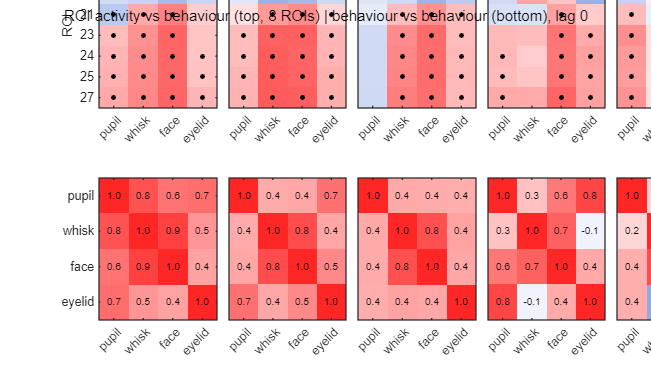


epp = find(ep_ok)';  nEpp = numel(epp);
if nEpp > 0
    h1 = max(3.5, 0.2 * nSel);  h2 = 3.0;  mT = 1.3;  mB = 1.5;  wc = (FW - 2.1 - 2.2) / nEpp;
    FH = mT + h1 + 1.5 + h2 + mB;
    bshort = cellfun(@(b) beh_short.(b), bn, 'UniformOutput', false);
    fh = newfig('Behaviour correlation', FW, FH);
    for j = 1:nEpp
        e = epp(j);  xj = 2.1 + (j - 1) * wc;
        p1 = [xj, FH - mT - h1, wc - 0.25, h1];
        ax1 = axes('Units', 'centimeters', 'Position', p1);
        imagesc(coup_r(sel_roi, :, e));  clim([-0.8 0.8]);  colormap(ax1, div_cmap);  hold on;
        [sr, sc] = find(coup_p(sel_roi, :, e) < 0.01);  plot(sc, sr, 'k*', 'MarkerSize', 3);
        xticks(1:nBeh);  xticklabels(bshort);  xtickangle(45);
        title({ep_lab(ep_names{e}), sprintf('%.0f s', ep_len(e))}, 'FontWeight', 'normal', 'FontSize', 7, 'Interpreter', 'none');
        if j == 1; yticks(1:roi_skip:nSel);  yticklabels(roi_lab(1:roi_skip:nSel));  ylabel('ROI'); else; yticks([]); end
        if j == nEpp; cb = colorbar(ax1);  cb.Label.String = 'r at best lag (* p < 0.01)';  cb.FontSize = 7;  set(ax1, 'Units', 'centimeters', 'Position', p1); end
        ax2 = axes('Units', 'centimeters', 'Position', [xj, mB, wc - 0.25, h2]);
        imagesc(beh_cc(:, :, e));  clim([-1 1]);  colormap(ax2, div_cmap);  hold on;
        for a = 1:nBeh; for b = 1:nBeh; if isfinite(beh_cc(a, b, e)); text(b, a, sprintf('%.1f', beh_cc(a, b, e)), 'HorizontalAlignment', 'center', 'FontSize', 6); end; end; end
        xticks(1:nBeh);  xticklabels(bshort);  xtickangle(45);
        if j == 1; yticks(1:nBeh);  yticklabels(bshort); else; yticks([]); end
    end
    annotation(fh, 'textbox', [0, 1 - 0.55 / FH, 1, 0.5 / FH], 'String', sprintf('ROI activity vs behaviour (top, %d ROIs) | behaviour vs behaviour (bottom), lag 0', nSel), 'EdgeColor', 'none', 'HorizontalAlignment', 'center', 'FontName', 'Arial', 'FontSize', 9);
    if save_figs; savef(fh, '04_behaviour_correlation'); end
end

## C. Extra diagnostic figures (extra_figs = true)

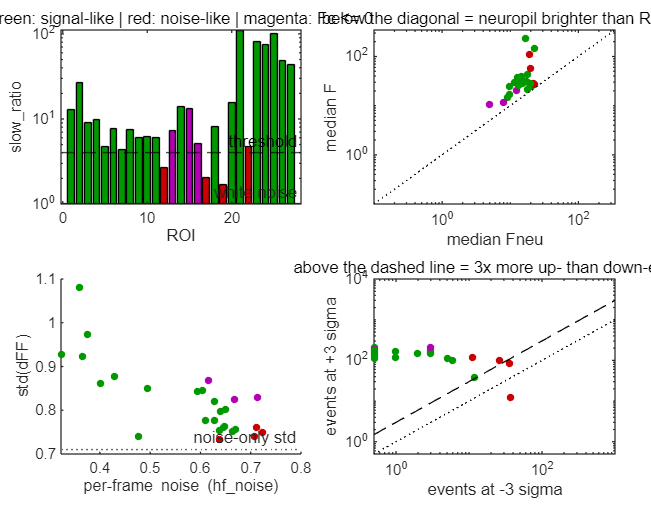

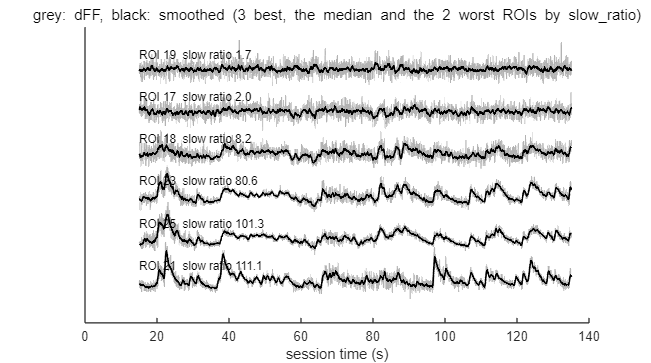

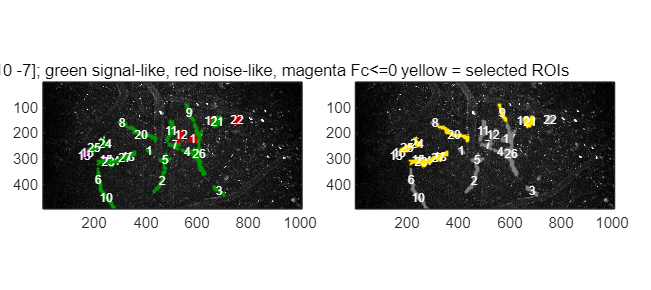

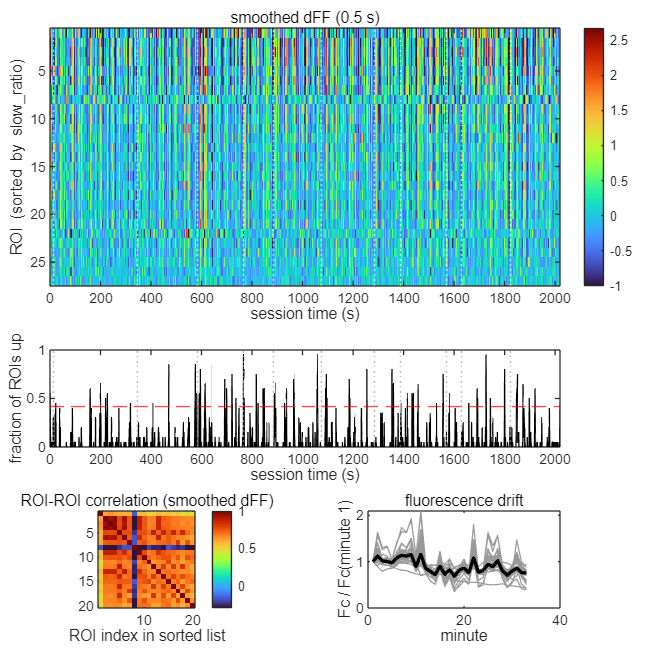

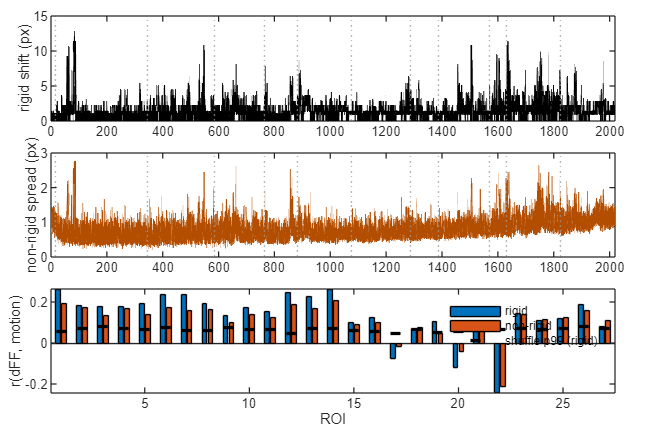

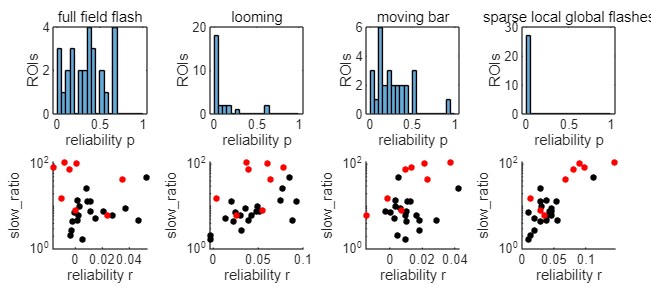

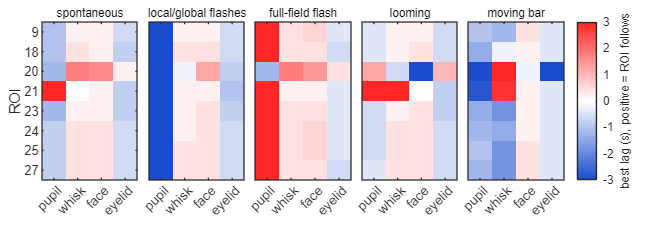

if extra_figs
    % C1 ROI signal quality
    cl = zeros(nROI, 3);  cl(signal_like, 2) = 0.6;  cl(noise_like & ~bad_F, 1) = 0.8;  cl(bad_F, :) = repmat([0.7 0 0.7], sum(bad_F), 1);
    fh = newfig('ROI signal quality', 18, 14);
    tiledlayout(fh, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    nexttile;  b = bar(slow_ratio, 'FaceColor', 'flat');  b.CData = cl;  set(gca, 'YScale', 'log');  yline(slow_ratio_thr, 'k--', 'threshold');  yline(1, ':', 'white noise');
    xlabel('ROI');  ylabel('slow\_ratio');  title('green: signal-like | red: noise-like | magenta: Fc <= 0', 'FontWeight', 'normal');
    nexttile;  loglog(max(median(Fneu, 2), 0.1), max(median(F, 2), 0.1), '.', 'MarkerSize', 1);  hold on;  scatter(max(median(Fneu, 2), 0.1), max(median(F, 2), 0.1), 20, cl, 'filled');
    lim = [0.1 max([median(F, 2); median(Fneu, 2)]) * 1.5];  plot(lim, lim, 'k:');  xlabel('median Fneu');  ylabel('median F');  title('below the diagonal = neuropil brighter than ROI', 'FontWeight', 'normal');
    nexttile;  scatter(hf_noise, std(dFF, 0, 2), 20, cl, 'filled');  hold on;  yline(0.71, ':', 'noise-only std');  xlabel('per-frame noise (hf\_noise)');  ylabel('std(dFF)');
    nexttile;  loglog(max(ev_neg, 0.5), max(ev_pos, 0.5), '.', 'MarkerSize', 1);  hold on;  scatter(max(ev_neg, 0.5), max(ev_pos, 0.5), 20, cl, 'filled');
    plot([0.5 1e3], [0.5 1e3], 'k:');  plot([0.5 1e3], 3*[0.5 1e3], 'k--');  xlabel('events at -3 sigma');  ylabel('events at +3 sigma');  title('above the dashed line = 3x more up- than down-events', 'FontWeight', 'normal');
    if save_figs; savef(fh, 'C1_roi_quality'); end

    % C2 example traces: best and worst ROIs, first 120 s of the spontaneous block (or of the session)
    if ~isempty(sp_blk); ex_t0 = b_t0(sp_blk); elseif bracketed && ~isempty(grey_seg); ex_t0 = grey_seg(1, 1); else; ex_t0 = tCa(1); end
    ex = tCa >= ex_t0 & tCa <= ex_t0 + 120;
    [~, ord] = sort(slow_ratio, 'descend');
    ex_rois = unique(ord([1 2 3 round(nROI/2) max(1, nROI-1) nROI])', 'stable');
    fh = newfig('Example ROI traces', 18, 10);  hold on;
    for j = 1:numel(ex_rois)
        r = ex_rois(j);
        plot(tCa(ex), double(dFF(r, ex)) / 6 + j, 'Color', [0.7 0.7 0.7]);
        plot(tCa(ex), double(dsm(r, ex)) / 6 + j, 'k', 'LineWidth', 1);
        text(tCa(find(ex, 1)), j + 0.35, sprintf('ROI %d  slow ratio %.1f', r, slow_ratio(r)), 'FontSize', 7);
    end
    yticks([]);  xlabel('session time (s)');  title('grey: dFF, black: smoothed (3 best, the median and the 2 worst ROIs by slow\_ratio)', 'FontWeight', 'normal');
    if save_figs; savef(fh, 'C2_example_traces'); end

    % C3 ROI map on the max projection
    if has_img
        fh = newfig('ROI map', 18, 8);
        tiledlayout(fh, 1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
        for pnl = 1:2
            nexttile;  imagesc(im);  axis image;  colormap(gca, gray);  clim(prctile(im(:), [1 99.8]));  hold on;
            for j = 1:numel(pl_rois)
                r = pl_rois(j);
                if pnl == 1; c = cl(r, :); elseif ismember(r, sel_roi); c = [1 0.9 0]; else; c = [0.5 0.5 0.5]; end
                plot(xp{j} + 1 + off(2), yp{j} + 1 + off(1), '.', 'Color', c, 'MarkerSize', 2);
                if nROI <= 80; text(cent(r, 2) + 1 + off(2), cent(r, 1) + 1 + off(1), sprintf('%d', r), 'Color', 'w', 'FontSize', 7, 'HorizontalAlignment', 'center'); end
            end
            if pnl == 1; title(sprintf('shift [%d %d]; green signal-like, red noise-like, magenta Fc<=0', off(1), off(2)), 'FontWeight', 'normal'); else; title('yellow = selected ROIs', 'FontWeight', 'normal'); end
        end
        if save_figs; savef(fh, 'C3_roi_map'); end
    end

    % C4 population: heatmap, FOV-wide events, ROI-ROI correlation, drift
    fh = newfig('Population', 18, 18);
    tiledlayout(fh, 4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    [~, so2] = sort(slow_ratio, 'descend');  show = so2(1:min(nROI, 200));
    nexttile([2 2]);  imagesc(tCa, 1:numel(show), double(dsm(show, :)));  clim([-1 max(prctile(double(dsm(:)), 99.7), 1)]);  colormap(gca, turbo);  colorbar;
    ylabel('ROI (sorted by slow\_ratio)');  xlabel('session time (s)');  title(sprintf('smoothed dFF (%.1f s)', smooth_s), 'FontWeight', 'normal');  xline(b_t0, 'w:');
    nexttile([1 2]);  plot(tCa, co, 'k');  hold on;  yline(co_thr, 'r--', 'FOV-wide threshold');  ylabel('fraction of ROIs up');  xlabel('session time (s)');  xlim([tCa(1) tCa(end)]);  xline(b_t0, 'Color', [0.6 0.6 0.6], 'LineStyle', ':');
    nexttile;  imagesc(Cm);  axis image;  clim([-0.3 1]);  colormap(gca, turbo);  colorbar;  title('ROI-ROI correlation (smoothed dFF)', 'FontWeight', 'normal');  xlabel('ROI index in sorted list');
    nexttile;  plot(1:nb, Fb_rel', 'Color', [0.6 0.6 0.6]);  hold on;  plot(1:nb, median(Fb_rel, 1, 'omitnan'), 'k', 'LineWidth', 2);  xlabel('minute');  ylabel('Fc / Fc(minute 1)');  title('fluorescence drift', 'FontWeight', 'normal');
    if save_figs; savef(fh, 'C4_population'); end

    % C5 motion
    if have_motion
        fh = newfig('Motion', 18, 12);
        tiledlayout(fh, 3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
        nexttile;  plot(tCa, rigid, 'k');  ylabel('rigid shift (px)');  xlim([tCa(1) tCa(end)]);  xline(b_t0, 'Color', [0.6 0.6 0.6], 'LineStyle', ':');
        nexttile;  plot(tCa, nonr, 'Color', [0.7 0.3 0]);  ylabel('non-rigid spread (px)');  xlim([tCa(1) tCa(end)]);  xline(b_t0, 'Color', [0.6 0.6 0.6], 'LineStyle', ':');
        nexttile;  bar([motion_r(:, 1) motion_r(:, 2)]);  hold on;  plot(thr99(:, 1), 'k_', 'LineWidth', 2);  ylabel('r(dFF, motion)');  xlabel('ROI');  legend([mot_names, {'shuffle p99 (rigid)'}]);
        if save_figs; savef(fh, 'C5_motion'); end
    end

    % C6 trial-to-trial reliability per stimulus type
    fh = newfig('Reliability', 18, 8);
    tiledlayout(fh, 2, numel(resp_types), 'TileSpacing', 'compact', 'Padding', 'compact');
    for ti = 1:numel(resp_types)
        R = resp.(resp_types{ti});
        nexttile(ti);  histogram(R.p, 0:0.05:1);  xlabel('reliability p');  ylabel('ROIs');  title(strrep(resp_types{ti}, '_', ' '), 'FontWeight', 'normal');
        nexttile(numel(resp_types) + ti);  scatter(R.rel, slow_ratio, 15, 'k', 'filled');  hold on;  scatter(R.rel(sel_roi), slow_ratio(sel_roi), 15, 'r', 'filled');  set(gca, 'YScale', 'log');  xlabel('reliability r');  ylabel('slow\_ratio');
    end
    if save_figs; savef(fh, 'C6_reliability'); end

    % C7 best lag of the behaviour correlations
    if nEpp > 0
        fh = newfig('Correlation lags', 18, 5 + 0.15 * nSel);
        tiledlayout(fh, 1, nEpp, 'TileSpacing', 'compact', 'Padding', 'compact');
        for j = 1:nEpp
            nexttile;  imagesc(coup_lag(sel_roi, :, epp(j)));  clim([-corr_max_lag_s corr_max_lag_s]);  colormap(gca, div_cmap);  title(ep_lab(ep_names{epp(j)}), 'FontWeight', 'normal', 'FontSize', 7);
            xticks(1:nBeh);  xticklabels(cellfun(@(b) beh_short.(b), bn, 'UniformOutput', false));  xtickangle(45);
            if j == 1; yticks(1:roi_skip:nSel);  yticklabels(roi_lab(1:roi_skip:nSel));  ylabel('ROI'); else; yticks([]); end
            if j == nEpp; cb = colorbar;  cb.Label.String = 'best lag (s), positive = ROI follows';  cb.FontSize = 7; end
        end
        if save_figs; savef(fh, 'C7_correlation_lags'); end
    end
end

## 11. Summary

fprintf('\n================ axon_analysis_V3 summary: %s ================\n', session);


================ axon_analysis_V3 summary: AnimalRB24_261021_1630 ================


cellfun(@(a, b, d) fprintf('[%s] %-36s %s\n', b, a, d), chk(:, 1), chk(:, 2), chk(:, 3));

[PASS] file: core variables                 4/4 present 
[PASS] file: optional variables             Behav 1, Locomotion 1, Img_max 1, SI_Info 1
[PASS] CaData: populated entry              CaData(1) has traces, 1 of 3 entries populated
[PASS] Ca arrays: same size                 dFF/F/Fneu/baseline/deconvolved: 27 ROIs x 60574 frames
[PASS] TimeCa: matches frames               60574 time stamps, 60574 frames
[PASS] ROI bookkeeping                      27 centroids, 27 cellstats
[PASS] dFF: finite                          0.0000% NaN/Inf
[PASS] planes                               1 plane(s); TimeCa has 1 row(s); row 1 is used as common time base
[PASS] Behav: rows == camera triggers       92631 camera triggers, 34 Behav fields
[PASS] VideoParams: frame selection         92631 selected frames
[PASS] Triggers: timing problems            TimingProblems = 0
[PASS] imaging: monotonic time              min dt 0.0333 s
[PASS] imaging: no dropped frames           fs 29.996 Hz, max dt / median 

fprintf('\n%d PASS, %d WARN, %d FAIL\n', sum(strcmp(chk(:, 2), 'PASS')), sum(strcmp(chk(:, 2), 'WARN')), sum(strcmp(chk(:, 2), 'FAIL')));


64 PASS, 15 WARN, 1 FAIL


fprintf('Candidate ROIs for analysis (signal-like, no Fc<=0, not motion-coupled): %s\n', lst(good_roi));

Candidate ROIs for analysis (signal-like, no Fc<=0, not motion-coupled): [9 18 20 21 23 24 25 27]


fprintf('Selected ROIs used for the figures (roi_sel): %s\n', lst(sel_roi));

Selected ROIs used for the figures (roi_sel): [9 18 20 21 23 24 25 27]


qc_table = cell2table(chk, 'VariableNames', {'check', 'status', 'detail'});
if save_figs
    writetable(roiq, fullfile(fig_dir, 'roi_quality.csv'));
    writetable(qc_table, fullfile(fig_dir, 'checks.csv'));
    writetable(corr_tbl, fullfile(fig_dir, 'behaviour_correlation.csv'));
    if ~isempty(loom_tbl); writetable(loom_tbl, fullfile(fig_dir, 'loom_spontaneous_pre_post.csv')); end
    if ~isempty(cmp_tbl); writetable(cmp_tbl, fullfile(fig_dir, 'loom_expand_vs_recede.csv')); end
end

## 12. ROI groups for the exploration

% The groups (sel_roi clustered on the correlation of the smoothed dF/F, section 7) are the units of every trial statistic below.
% Sections 13 and 14 need flashes and looming trials, section 15 the moving bar; a missing stimulus type skips its section (the bracketed design has no chirp / spontaneous block).
do_arousal = explore_stats && isfield(resp, 'sparse_local_global_flashes') && isfield(resp, 'looming');
do_bar     = explore_stats && isfield(resp, 'moving_bar');
if explore_stats && ~do_arousal; fprintf('\nSections 13 and 14 skipped: they need sparse_local_global_flashes and looming trials\n'); end
if explore_stats && ~do_bar; fprintf('\nSection 15 skipped: no moving_bar trials\n'); end
if explore_stats
    rng(2);
    flat_roi = find(noise_like & ~bad_F)';  npl_roi = find(bad_F)';
    fprintf('\nExploration groups (r > %g on the smoothed dF/F):\n', grp_r_thr);
    for g = 1:ng; fprintf('  group %d: %s\n', g, grp_lab{g}); end
    ex = cell(0, 5);
    exadd = @(c, a, b, v, ci, n) [c; {a, b, v, ci, n}];
    ci_str = @(x) sprintf('[%.2f, %.2f]', x(1), x(2));
    take = @(x, I) x(I);
end


Exploration groups (r > 0.8 on the smoothed dF/F):


  group 1: ROI 18,23,24,25,27
  group 2: ROI 9
  group 3: ROI 20
  group 4: ROI 21


## 13. Direction 1: arousal vs stimulus

13: 23 isolated whisking bouts in the spontaneous block (274 bouts in the whole session)


13: 86 quiet reference times, group-1 peak statistic on noise 0.19 +- 0.44 dF/F


13c ROI 18,23,24,25,27: dF/F per unit whisking 0.38 [0.16, 1.24] | extra response at equal whisking: flash -0.02 [-0.44, 0.60], looming -0.17 [-0.68, 0.61] (n=88 events)
13c ROI 9: dF/F per unit whisking 0.17 [0.05, 0.56] | extra response at equal whisking: flash -0.08 [-0.31, 0.25], looming -0.27 [-0.54, 0.13] (n=88 events)
13c ROI 20: dF/F per unit whisking 0.10 [-0.41, 0.23] | extra response at equal whisking: flash -0.12 [-0.50, 0.16], looming +0.02 [-0.55, 0.40] (n=88 events)
13c ROI 21: dF/F per unit whisking 0.45 [-0.02, 2.08] | extra response at equal whisking: flash -0.24 [-0.94, 0.90], looming +0.02 [-1.05, 1.60] (n=88 events)


13c flash trials without detectable whisking (n=18): mean peak dF/F 0.85 vs 0.19 +- 0.44 at quiet times (rank-sum p=9.5e-06), ROI 18,23,24,25,27
13c flash trials without detectable whisking (n=18): mean peak dF/F 0.86 vs 0.53 +- 0.24 at quiet times (rank-sum p=0.00031), ROI 9
13c looming trials without detectable whisking (n=3): mean peak dF/F 0.41 vs 0.19 +- 0.44 at quiet times (rank-sum p=0.35), ROI 18,23,24,25,27
13c looming trials without detectable whisking (n=3): mean peak dF/F 0.69 vs 0.53 +- 0.24 at quiet times (rank-sum p=0.95), ROI 9


13b spontaneous bout: ROI half-rise minus whisking half-rise median +0.16 s [0.14, 0.21] (n=21 events with a clear response in both)
13b flash: ROI half-rise minus whisking half-rise median +0.04 s [-0.09, 0.10] (n=26 events with a clear response in both)
13b looming: ROI half-rise minus whisking half-rise median +0.00 s [-0.52, 0.23] (n=9 events with a clear response in both)


13b flash lag minus spontaneous-bout lag: -0.12 s [-0.26, -0.05] (< 0: the ROI response follows whisking less closely after a flash than after a spontaneous bout)


13d ROI 18,23,24,25,27 | chirp blocks: held-out R2 behaviour 0.32, + stimulus 0.29 (gain -0.024; shifted-onset null -0.017 +- 0.036, p=0.67)
13d ROI 18,23,24,25,27 | looming blocks: held-out R2 behaviour 0.36, + stimulus 0.38 (gain +0.020; shifted-onset null -0.011 +- 0.028, p=0.14)
13d ROI 18,23,24,25,27 | bar sweep blocks: held-out R2 behaviour -0.40, + stimulus -0.50 (gain -0.100; shifted-onset null -0.120 +- 0.043, p=0.29)
13d ROI 18,23,24,25,27 | flash blocks: held-out R2 behaviour 0.23, + stimulus 0.25 (gain +0.018; shifted-onset null -0.038 +- 0.013, p=0.05)
13d ROI 9 | chirp blocks: held-out R2 behaviour 0.07, + stimulus 0.06 (gain -0.003; shifted-onset null -0.004 +- 0.011, p=0.52)
13d ROI 9 | looming blocks: held-out R2 behaviour 0.06, + stimulus 0.07 (gain +0.001; shifted-onset null -0.006 +- 0.009, p=0.24)
13d ROI 9 | bar sweep blocks: held-out R2 behaviour -0.10, + stimulus -0.12 (gain -0.022; shifted-onset null -0.027 +- 0.011, p=0.38)
13d ROI 9 | flash blocks: held-out R

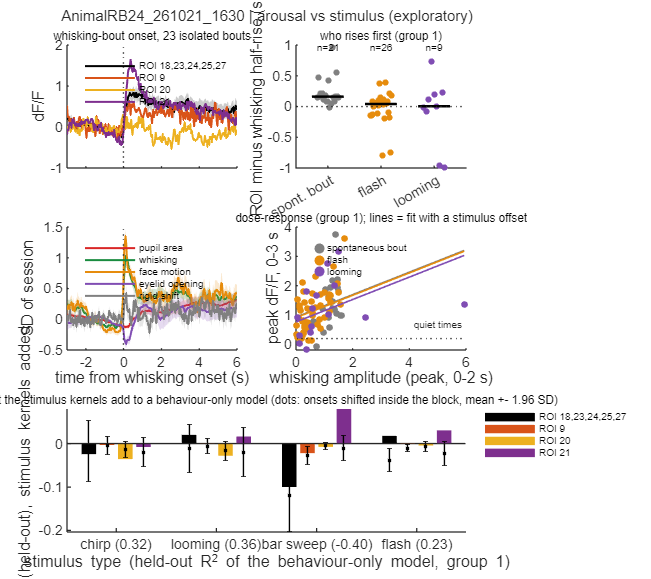

% Question: do the axons encode the animal's arousal / whisking, with the stimulus acting through the behaviour it evokes?
% 13a  whisking-bout-triggered averages in the spontaneous block (isolated bouts: whisking was off for whisk_bout_gap_s before the onset)
if do_arousal
    Bh     = data.Behav;
    wk_on  = double(Bh.WhiskOn(:)) > 0;
    e_idx  = find(diff([false; wk_on]) == 1);
    g_q    = round(whisk_bout_gap_s * cam_fs);
    cs_    = cumsum(wk_on);
    quiet  = e_idx > g_q + 1;
    quiet(quiet) = (cs_(e_idx(quiet) - 1) - cs_(e_idx(quiet) - 1 - g_q)) == 0;
    t_e    = tcam(e_idx);  t_e = t_e(:);
    if bracketed && ~isempty(grey_seg)
        sp_segs = grey_seg;  sp_what = 'grey windows around the looming';
    elseif isempty(sp_blk)
        sp_segs = [tCa(1) tCa(end)];  sp_what = 'whole session (no spontaneous block)';
    else
        sp_segs = [b_t0(sp_blk) b_t1(sp_blk)];  sp_what = 'spontaneous block';
    end
    in_sp = false(size(t_e));
    for s_ = 1:size(sp_segs, 1); in_sp = in_sp | (t_e >= sp_segs(s_, 1) + 3 & t_e <= sp_segs(s_, 2) - 6); end
    ons_sp = t_e(quiet & in_sp)';
    fprintf('13: %d isolated whisking bouts in the %s (%d bouts in the whole session)\n', numel(ons_sp), sp_what, numel(e_idx));

    rig_z = zeros(1, nT);  if have_motion; rig_z = (rigid - mean(rigid)) / std(rigid); end
    Xev   = [grp_mean; BZ];                                                      % rows: groups, then the behaviours of beh_names (session z-score)
    if have_motion; Xev = [Xev; rig_z]; end
    ev_names = [grp_lab, beh_names, repmat({'rigid shift'}, 1, have_motion)];
    pre_s = 3;  post_s = 6;  n_c = round((pre_s + post_s) * fs) + 1;  tev = linspace(-pre_s, post_s, n_c);
    Aev = align_trials_to_onsets(ons_sp, Xev, tCa, pre_s, post_s, n_c);          % [rows x time x bouts]
    Aev = Aev - mean(Aev(:, tev >= -2.5 & tev <= -0.5, :), 2, 'omitnan');

    % 13b / 13c  per event (spontaneous bout, flash, looming trial): whisking and ROI-group response, amplitude and half-rise time
    wamp_c = movmean(max(double(Bh.WhiskIndex(:))' - 1, 0), round(0.2 * cam_fs));         % whisking amplitude (0 = rest), camera grid, 0.2 s smoothing
    gsm_   = movmean(grp_mean, round(0.2 * fs), 2);
    nc_c = round(4 * cam_fs) + 1;  nc_i = round(4 * fs) + 1;
    t_c  = linspace(-1, 3, nc_c);  t_i  = linspace(-1, 3, nc_i);
    ons_f = resp.sparse_local_global_flashes.onsets(:)';
    ons_l = resp.looming.onsets(:)';
    ev_sets = {'spontaneous bout', ons_sp; 'flash', ons_f; 'looming', ons_l};
    evm = struct('name', {}, 'ons', {}, 'wh_mag', {}, 'wh_t', {}, 'roi_mag', {}, 'roi_t', {});
    for e = 1:size(ev_sets, 1)
        ons = ev_sets{e, 2};  nev = numel(ons);
        Wev = reshape(align_trials_to_onsets(ons, wamp_c, tcam, 1, 3, nc_c), nc_c, nev);
        Gev = align_trials_to_onsets(ons, gsm_, tCa, 1, 3, nc_i);
        m = struct('name', ev_sets{e, 1}, 'ons', ons, 'wh_mag', nan(1, nev), 'wh_t', nan(1, nev), 'roi_mag', nan(ng, nev), 'roi_t', nan(ng, nev));
        for i = 1:nev
            [m.wh_mag(i), m.wh_t(i)] = rise_stats(t_c, Wev(:, i), [0 2]);
            for g = 1:ng; [m.roi_mag(g, i), m.roi_t(g, i)] = rise_stats(t_i, squeeze(Gev(g, :, i)), [0 3]); end
        end
        evm(e) = m;
    end
    % quiet reference: the same statistics at random times of the spontaneous block without whisking (bias of a peak statistic on noise)
    qn = struct('roi_mag', nan(ng, 0));  tries = 0;
    sp_len = max(diff(sp_segs, 1, 2) - 9, 0);  sp_cum = cumsum(sp_len);
    while size(qn.roi_mag, 2) < 100 && tries < 2000
        tries = tries + 1;  u_ = rand * sp_cum(end);  s_ = find(u_ <= sp_cum, 1);  tq = sp_segs(s_, 1) + 3 + (u_ - (sp_cum(s_) - sp_len(s_)));
        if max(wamp_c(tcam >= tq - 1 & tcam <= tq + 3)) < whisk_lo
            Gq = align_trials_to_onsets(tq, gsm_, tCa, 1, 3, nc_i);
            mg = nan(ng, 1);  for g = 1:ng; mg(g) = rise_stats(t_i, squeeze(Gq(g, :, 1)), [0 3]); end
            qn.roi_mag(:, end+1) = mg; %#ok<SAGROW>
        end
    end
    fprintf('13: %d quiet reference times, group-1 peak statistic on noise %.2f +- %.2f dF/F\n', size(qn.roi_mag, 2), mean(qn.roi_mag(1, :)), std(qn.roi_mag(1, :)));

    % dose-response model: roi_mag ~ 1 + whisking + flash + looming, fit on all events; bootstrap over events
    wh_all = [evm.wh_mag];  ty_all = [ones(1, numel(evm(1).ons)), 2 * ones(1, numel(evm(2).ons)), 3 * ones(1, numel(evm(3).ons))];
    dose = struct('g', {}, 'b', {}, 'ci', {});
    for g = 1:ng
        y_ = [evm.roi_mag];  y_ = y_(g, :);
        X_ = [ones(numel(y_), 1), wh_all(:), ty_all(:) == 2, ty_all(:) == 3];
        ok = all(isfinite([y_(:), X_]), 2);
        b0 = X_(ok, :) \ y_(ok)';
        bb = nan(n_boot, 4);  idx_ok = find(ok);
        for b = 1:n_boot; r_ = idx_ok(randi(numel(idx_ok), numel(idx_ok), 1)); bb(b, :) = (X_(r_, :) \ y_(r_)')'; end
        dose(g).g = g;  dose(g).b = b0';  dose(g).ci = prctile(bb, [2.5 97.5]);
        fprintf('13c %s: dF/F per unit whisking %.2f %s | extra response at equal whisking: flash %+.2f %s, looming %+.2f %s (n=%d events)\n', grp_lab{g}, b0(2), ci_str(dose(g).ci(:, 2)), b0(3), ci_str(dose(g).ci(:, 3)), b0(4), ci_str(dose(g).ci(:, 4)), sum(ok));
        ex = exadd(ex, ['13c dose-response, ' grp_lab{g}], 'extra dF/F of a flash at equal whisking', b0(3), ci_str(dose(g).ci(:, 3)), sum(ok));
        ex = exadd(ex, ['13c dose-response, ' grp_lab{g}], 'extra dF/F of a looming trial at equal whisking', b0(4), ci_str(dose(g).ci(:, 4)), sum(ok));
    end
    % stimulus trials without whisking
    for e = 2:3
        lo = evm(e).wh_mag < whisk_lo | isnan(evm(e).wh_mag);  nlo = sum(lo);
        if nlo >= 2
            for g = 1:min(ng, 2)
                v = evm(e).roi_mag(g, lo);  v = v(isfinite(v));
                p_rs = ranksum(v, qn.roi_mag(g, :));
                fprintf('13c %s trials without detectable whisking (n=%d): mean peak dF/F %.2f vs %.2f +- %.2f at quiet times (rank-sum p=%.2g), %s\n', evm(e).name, nlo, mean(v), mean(qn.roi_mag(g, :)), std(qn.roi_mag(g, :)), p_rs, grp_lab{g});
                ex = exadd(ex, ['13c ' evm(e).name ' trials without detectable whisking, ' grp_lab{g}], 'mean peak dF/F vs quiet-time reference', mean(v), sprintf('ref %.2f+-%.2f, rank-sum p=%.2g', mean(qn.roi_mag(g, :)), std(qn.roi_mag(g, :)), p_rs), nlo);
            end
        end
    end
    % latency: ROI half-rise minus whisking half-rise, per event with a clear response in both
    lag = cell(1, 3);
    for e = 1:3; lag{e} = evm(e).roi_t(1, :) - evm(e).wh_t; end
    for e = 1:3
        v = lag{e}(isfinite(lag{e}));
        if numel(v) >= 3
            bs = arrayfun(@(b) median(v(randi(numel(v), numel(v), 1))), 1:n_boot);  ci = prctile(bs, [2.5 97.5]);
            fprintf('13b %s: ROI half-rise minus whisking half-rise median %+.2f s %s (n=%d events with a clear response in both)\n', evm(e).name, median(v), ci_str(ci), numel(v));
            ex = exadd(ex, ['13b latency ROI - whisking, ' evm(e).name], 'median lag (s)', median(v), ci_str(ci), numel(v));
        end
    end

    v1 = lag{1}(isfinite(lag{1}));  v2 = lag{2}(isfinite(lag{2}));
    if numel(v1) >= 3 && numel(v2) >= 3
        bd_ = arrayfun(@(b) median(v2(randi(numel(v2), 1, numel(v2)))) - median(v1(randi(numel(v1), 1, numel(v1)))), 1:n_boot);  ci = prctile(bd_, [2.5 97.5]);
        fprintf('13b flash lag minus spontaneous-bout lag: %+.2f s %s (< 0: the ROI response follows whisking less closely after a flash than after a spontaneous bout)\n', median(v2) - median(v1), ci_str(ci));
        ex = exadd(ex, '13b latency ROI - whisking', 'flash minus spontaneous bout (s)', median(v2) - median(v1), ci_str(ci), numel(v1) + numel(v2));
    end
    % 13d  encoding model, leave-one-block-out ridge: behaviour only vs behaviour + stimulus kernels
    blk_f  = zeros(nT, 1);  for k = 1:nB; blk_f(tCa >= b_t0(k) & tCa <= b_t1(k)) = k; end
    wbox = round(0.5 * fs);
    zf   = @(x) (x - mean(x, 'omitnan')) / std(x, 'omitnan');
    Rb   = max(beh_ca.WhiskIndex - 1, 0);
    bi_p = find(strcmp(beh_names, 'PupilArea'), 1);  bi_f = find(strcmp(beh_names, 'FacePadME'), 1);
    Rb   = [Rb; BZ([bi_p bi_f], :)];  if have_motion; Rb = [Rb; rig_z]; end
    Rb(isnan(Rb)) = 0;                                                           % outside the camera coverage the history counts as rest / session mean
    Xb   = cell2mat(arrayfun(@(i) box_lags(Rb(i, :), -2:7, wbox), 1:size(Rb, 1), 'UniformOutput', false));     % lags -1 s (future) to +4 s (past), 0.5 s boxcars
    st_names = {'full_field_flash', 'looming', 'moving_bar', 'sparse_local_global_flashes'};
    st_short = {'chirp', 'looming', 'bar sweep', 'flash'};
    st_has   = isfield(resp, st_names);  st_names = st_names(st_has);  st_short = st_short(st_has);  nq = numel(st_names);      % types this session does not have (no chirp in the bracketed design) are left out
    Xs = cell(1, nq);  ons_st = cell(1, nq);
    for q = 1:nq; ons_st{q} = resp.(st_names{q}).onsets(:)'; Xs{q} = stim_reg(ons_st{q}, tCa, 0:11, wbox); end
    Y_  = grp_mean';
    [sse1, sst1] = cv_ridge(Y_, Xb, blk_f, 0.05);
    [sse2, sst2] = cv_ridge(Y_, [Xb, cell2mat(Xs)], blk_f, 0.05);
    % null: stimulus onsets circularly shifted inside their block (same number of trials, timing destroyed)
    n_null = 20;  dnull = nan(n_null, nq, ng);  dobs = nan(nq, ng);  r2b = nan(nq, ng);  r2f = nan(nq, ng);
    for q = 1:nq
        kb = find(strcmp(b_type, st_names{q}))';
        r2b(q, :) = 1 - sum(sse1(kb, :), 1) ./ sum(sst1(kb, :), 1);
        r2f(q, :) = 1 - sum(sse2(kb, :), 1) ./ sum(sst2(kb, :), 1);
        dobs(q, :) = r2f(q, :) - r2b(q, :);
    end
    for it = 1:n_null
        Xn = cell2mat(arrayfun(@(q) stim_reg(shift_in_blocks(ons_st{q}, b_t0, b_t1), tCa, 0:11, wbox), 1:nq, 'UniformOutput', false));
        [sse3, sst3] = cv_ridge(Y_, [Xb, Xn], blk_f, 0.05);
        for q = 1:nq
            kb = find(strcmp(b_type, st_names{q}))';
            dnull(it, q, :) = (1 - sum(sse3(kb, :), 1) ./ sum(sst3(kb, :), 1)) - r2b(q, :);
        end
    end
    for g = 1:ng
        for q = 1:nq
            nl = dnull(:, q, g);  p_ = (1 + sum(nl >= dobs(q, g))) / (n_null + 1);
            fprintf('13d %s | %s blocks: held-out R2 behaviour %.2f, + stimulus %.2f (gain %+.3f; shifted-onset null %+.3f +- %.3f, p=%.2f)\n', grp_lab{g}, st_short{q}, r2b(q, g), r2f(q, g), dobs(q, g), mean(nl), std(nl), p_);
            ex = exadd(ex, ['13d encoding model, ' grp_lab{g}], ['held-out R2 gain from stimulus kernels, ' st_short{q} ' blocks'], dobs(q, g), sprintf('null %+.3f+-%.3f, p=%.2f', mean(nl), std(nl), p_), sum(sst1(strcmp(b_type, st_names{q}), 1) > 0));
        end
    end
    % ---- figure 05
    ecol = [0.5 0.5 0.5; 0.9 0.55 0.05; 0.5 0.3 0.7];
    fh = newfig('Arousal vs stimulus', 18, 16);
    tl = tiledlayout(fh, 3, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, [session ' | arousal vs stimulus (exploratory)'], 'FontSize', 9, 'FontWeight', 'normal', 'Interpreter', 'none');
    a1 = nexttile(tl, 1);  hold(a1, 'on');  hg = gobjects(1, ng);
    for g = 1:ng; hg(g) = sem_trace(a1, tev, squeeze(Aev(g, :, :)), gcol(g, :), g == 1); end
    xline(a1, 0, ':');  ylabel(a1, 'dF/F');  xlim(a1, tev([1 end]));  set(a1, 'XTickLabel', []);
    title(a1, sprintf('whisking-bout onset, %d isolated bouts', numel(ons_sp)), 'FontSize', 7, 'FontWeight', 'normal');
    legend(a1, hg, grp_lab, 'FontSize', 6, 'Location', 'northwest');
    a3 = nexttile(tl, 3);  hold(a3, 'on');  hb = gobjects(1, 0);  lb = {};
    for i = 1:numel(beh_names); hb(end+1) = sem_trace(a3, tev, squeeze(Aev(ng + i, :, :)), beh_cmap.(beh_names{i}), true); lb{end+1} = beh_lab.(beh_names{i}); end %#ok<SAGROW>
    if have_motion; hb(end+1) = sem_trace(a3, tev, squeeze(Aev(ng + numel(beh_names) + 1, :, :)), [0.5 0.5 0.5], true); lb{end+1} = 'rigid shift'; end
    xline(a3, 0, ':');  ylabel(a3, 'SD of session');  xlabel(a3, 'time from whisking onset (s)');  xlim(a3, tev([1 end]));  legend(a3, hb, lb, 'FontSize', 6, 'Location', 'northwest');
    a2 = nexttile(tl, 2);  hold(a2, 'on');
    for e = 1:3
        v = lag{e}(isfinite(lag{e}));
        scatter(a2, e + linspace(-0.2, 0.2, numel(v)), v, 14, ecol(e, :), 'filled');
        if ~isempty(v); plot(a2, e + [-0.3 0.3], median(v) * [1 1], 'k-', 'LineWidth', 1.5); end
        text(a2, e, 0.95, sprintf('n=%d', numel(v)), 'Units', 'data', 'HorizontalAlignment', 'center', 'FontSize', 6);
    end
    yline(a2, 0, ':');  xticks(a2, 1:3);  xticklabels(a2, {'spont. bout', 'flash', 'looming'});  xlim(a2, [0.4 3.6]);  ylim(a2, [-1 1]);
    ylabel(a2, 'ROI minus whisking half-rise (s)');  title(a2, 'who rises first (group 1)', 'FontSize', 7, 'FontWeight', 'normal');
    a4 = nexttile(tl, 4);  hold(a4, 'on');  hs = gobjects(1, 3);  wg = linspace(0, max(wh_all, [], 'omitnan'), 50);
    for e = 1:3
        hs(e) = scatter(a4, evm(e).wh_mag, evm(e).roi_mag(1, :), 16, ecol(e, :), 'filled');
        plot(a4, wg, dose(1).b(1) + dose(1).b(2) * wg + (e == 2) * dose(1).b(3) + (e == 3) * dose(1).b(4), '-', 'Color', ecol(e, :), 'LineWidth', 1);
    end
    yline(a4, mean(qn.roi_mag(1, :)), ':', 'quiet times', 'FontSize', 6);
    xlabel(a4, 'whisking amplitude (peak, 0-2 s)');  ylabel(a4, 'peak dF/F, 0-3 s');  title(a4, 'dose-response (group 1); lines = fit with a stimulus offset', 'FontSize', 7, 'FontWeight', 'normal');
    legend(a4, hs, {evm.name}, 'FontSize', 6, 'Location', 'northwest');
    a5 = nexttile(tl, 5, [1 2]);  hold(a5, 'on');
    bd = bar(a5, dobs, 'grouped');
    for g = 1:ng
        bd(g).FaceColor = gcol(g, :);  bd(g).EdgeColor = 'none';
        errorbar(a5, bd(g).XEndPoints, mean(dnull(:, :, g), 1), 1.96 * std(dnull(:, :, g), 0, 1), 'k.', 'CapSize', 3, 'MarkerSize', 6);
    end
    yline(a5, 0, '-');  xticks(a5, 1:nq);  xticklabels(a5, arrayfun(@(q) sprintf('%s (%.2f)', st_short{q}, r2b(q, 1)), 1:nq, 'UniformOutput', false));  xtickangle(a5, 0);  xlabel(a5, 'stimulus type (held-out R^2 of the behaviour-only model, group 1)');
    ylabel(a5, '\DeltaR^2 (held-out), stimulus kernels added');  legend(a5, bd, grp_lab, 'FontSize', 6, 'Location', 'northeastoutside');
    title(a5, 'what the stimulus kernels add to a behaviour-only model (dots: onsets shifted inside the block, mean +- 1.96 SD)', 'FontSize', 7, 'FontWeight', 'normal');
    if save_figs; savef(fh, '05_arousal_vs_stimulus'); end
end

## 14. Direction 2: is the flash response optical / motion, or a calcium response?

14b dF/F bundle            onset  0.05 s [0.03, 0.11] | 10-90% rise  0.28 s [0.20, 0.58] | peak at 0.63 s
14b dF/F other selected    onset  0.09 s [0.07, 0.23] | 10-90% rise  0.26 s [0.16, 0.53] | peak at 0.33 s
14b dF/F flat ROIs         onset  0.29 s [0.23, 0.41] | 10-90% rise  0.30 s [0.22, 0.41] | peak at 0.39 s
14b dF/F neuropil-limited  onset  0.07 s [0.07, 0.37] | 10-90% rise  0.36 s [0.20, 0.50] | peak at 0.39 s
14b F bundle               onset  0.03 s [0.01, 0.07] | 10-90% rise  0.28 s [0.20, 0.42] | peak at 0.33 s
14b Fneu bundle            onset  0.05 s [0.01, 0.21] | 10-90% rise  0.30 s [0.12, 0.32] | peak at 0.33 s
14b F flat ROIs            onset   NaN s [0.27, 0.39] | 10-90% rise  0.38 s [0.25, 0.38] | peak at 0.39 s
14b whisking               onset  0.01 s [0.01, 0.11] | 10-90% rise  0.12 s [0.08, 0.50] | peak at 0.19 s
14b face motion            onset  0.05 s [0.05, 0.29] | 10-90% rise  0.10 s [0.08, 1.42] | peak at 0.15 s
14b pupil (inverted)       onset  0.23 s [0.21

14c F     change in counts vs baseline across 27 ROIs: slope 0.011 [-0.01, 0.04] counts per count (multiplicative response expects > 0, additive offset ~ 0), Spearman 0.16, mean change 4.81 counts
14c Fneu  change in counts vs baseline across 27 ROIs: slope -0.013 [-0.02, -0.00] counts per count (multiplicative response expects > 0, additive offset ~ 0), Spearman -0.38, mean change 0.23 counts


    roi    F_base    dF_counts    dFneu_counts    dFF_resp       group   
    ___    ______    _________    ____________    _________    __________

     1     44.151      9.9178       0.027825        0.61171    {0×0 char}
     2     29.065       4.039        0.26866        0.53515    {0×0 char}
     3     28.226      3.3016      -0.048818        0.45982    {0×0 char}
     4     30.381      5.0634        0.32607        0.45403    {0×0 char}
     5     21.836      1.6597        0.20531        0.34504    {0×0 char}
     6     15.018      2.0857        0.15575        0.45666    {0×0 char}
     7      26.54       1.674        0.34233        0.25844    {0×0 char}
     8     27.575      5.2956        0.34205        0.47086    {0×0 char}
     9     25.738      2.4141        0.19319        0.3

14d bundle           flash response 0.2-1.5 s: low-whisking flashes 0.40 +- 0.10, high-whisking flashes 0.87 +- 0.11 dF/F, Spearman with evoked whisking 0.47
14d other selected   flash response 0.2-1.5 s: low-whisking flashes 0.25 +- 0.07, high-whisking flashes 0.58 +- 0.12 dF/F, Spearman with evoked whisking 0.33
14d flat ROIs        flash response 0.2-1.5 s: low-whisking flashes -0.01 +- 0.03, high-whisking flashes 0.09 +- 0.03 dF/F, Spearman with evoked whisking 0.42
14d neuropil-limited flash response 0.2-1.5 s: low-whisking flashes 0.23 +- 0.06, high-whisking flashes 0.51 +- 0.05 dF/F, Spearman with evoked whisking 0.52


14e synthetic additive      : slope 0.011 counts per count, 10-90% rise 0.18 s, onset 0.01 s
14e synthetic multiplicative: slope 0.201 counts per count, 10-90% rise 0.26 s, onset 0.01 s


14e [PASS] the slope / rise-time test separates an additive step from a multiplicative calcium-like response


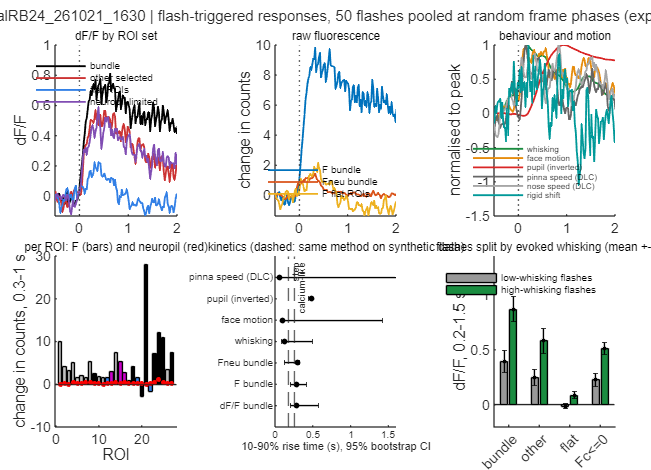

% Flash-triggered averages are pooled in 20 ms bins: the flashes fall at random phases of the 33 ms frame clock, so 50 flashes sample the
% response finer than one frame. A light leak is a step within one frame, identical in F and in the neuropil, and additive (the same counts in every ROI
% whatever its brightness); a calcium response rises over several frames and scales with the baseline fluorescence.
if do_arousal
    nF = numel(ons_f);
    W_ = round(4 * fs) + 4;
    i0 = arrayfun(@(t) find(tCa >= t - 1, 1), ons_f);
    idxF = i0(:) + (0:W_-1);
    okF = all(idxF <= nT, 2);  idxF = idxF(okF, :);  onsF = ons_f(okF);  nF = numel(onsF);
    Trel = tCa(idxF) - onsF(:);
    mk_b = Trel >= -1 & Trel < -0.1;
    sub_b = @(Y) Y - sum(Y .* mk_b, 2) ./ sum(mk_b, 2);
    edges = -1:0.02:3;
    sets   = {grp_rois{1}, setdiff(sel_roi, grp_rois{1}), flat_roi, npl_roi};
    snames = {'bundle', 'other selected', 'flat ROIs', 'neuropil-limited'};  snames_s = {'bundle', 'other', 'flat', 'Fc<=0'};
    kp = ~cellfun(@isempty, sets);  sets = sets(kp);  snames = snames(kp);  snames_s = snames_s(kp);  nS = numel(sets);
    sig_defs = {};                                                               % name, data [nF x W_] (baseline subtracted), time [nF x W_]
    for s = 1:nS
        sig_defs(end+1, :) = {['dF/F ' snames{s}], sub_b(take(mean(dFFd(sets{s}, :), 1), idxF)), Trel}; %#ok<SAGROW>
    end
    sig_defs(end+1, :) = {'F bundle', sub_b(take(double(mean(F(sets{1}, :), 1)), idxF)), Trel};
    sig_defs(end+1, :) = {'Fneu bundle', sub_b(take(double(mean(Fneu(sets{1}, :), 1)), idxF)), Trel};
    if nS >= 3; sig_defs(end+1, :) = {'F flat ROIs', sub_b(take(double(mean(F(sets{3}, :), 1)), idxF)), Trel}; end
    % camera grid signals
    Wc_ = round(4 * cam_fs) + 4;
    i0c = arrayfun(@(t) find(tcam >= t - 1, 1), onsF);
    idxC = i0c(:) + (0:Wc_-1);  idxC(idxC > numel(tcam)) = numel(tcam);
    TrelC = tcam(idxC) - onsF(:);
    mk_bc = TrelC >= -1 & TrelC < -0.1;
    sub_bc = @(Y) Y - sum(Y .* mk_bc, 2) ./ sum(mk_bc, 2);
    cam_defs = {'whisking', sub_bc(take(double(Bh.WhiskIndex(:))', idxC)); 'face motion', sub_bc(take(double(Bh.FacePadME(:))', idxC)); 'pupil (inverted)', -sub_bc(take(double(Bh.PupilArea(:))', idxC))};
    for q = 1:size(cam_defs, 1); sig_defs(end+1, :) = {cam_defs{q, 1}, cam_defs{q, 2}, TrelC}; end %#ok<SAGROW>
    % movement from DLC points (positions, not image intensity: unaffected by a change of the illumination of the video)
    spd = @(P) movmean([0; hypot(diff(double(P(:, 1))), diff(double(P(:, 2))))]', 3, 'omitnan') * cam_fs;
    dlc_names = {'noseTip', 'PinnaRightTip', 'whiskerFollicleA1'};  dlc_lab = {'nose speed (DLC)', 'pinna speed (DLC)', 'whisker follicle speed (DLC)'};
    for q = 1:numel(dlc_names); sig_defs(end+1, :) = {dlc_lab{q}, sub_bc(take(spd(Bh.(dlc_names{q})), idxC)), TrelC}; end %#ok<SAGROW>
    if have_motion; sig_defs(end+1, :) = {'rigid shift', sub_b(rigid(idxF)), Trel}; end
    nSig = size(sig_defs, 1);
    kin = struct('name', {}, 'onset', {}, 'rise', {}, 'peak_t', {}, 'peak', {}, 'ci', {}, 'tb', {}, 'm', {});
    for s = 1:nSig
        Yd = sig_defs{s, 2};  Tr = sig_defs{s, 3};
        [m_, tb] = pool_bin(Tr, Yd, edges);
        k0 = kin_stats(tb, m_);
        kb_ = nan(n_boot, 3);
        for b = 1:n_boot; r_ = randi(nF, nF, 1); kk = kin_stats(tb, pool_bin(Tr(r_, :), Yd(r_, :), edges)); kb_(b, :) = [kk.onset kk.rise kk.peak_t]; end
        kin(s).name = sig_defs{s, 1};  kin(s).onset = k0.onset;  kin(s).rise = k0.rise;  kin(s).peak_t = k0.peak_t;  kin(s).peak = k0.peak;
        kin(s).ci = prctile(kb_, [2.5 97.5]);  kin(s).tb = tb;  kin(s).m = m_;
        fprintf('14b %-22s onset %5.2f s %s | 10-90%% rise %5.2f s %s | peak at %4.2f s\n', kin(s).name, k0.onset, ci_str(kin(s).ci(:, 1)), k0.rise, ci_str(kin(s).ci(:, 2)), k0.peak_t);
        ex = exadd(ex, ['14b flash kinetics, ' kin(s).name], 'onset latency (s) / 10-90% rise (s)', k0.onset, sprintf('rise %.2f s %s', k0.rise, ci_str(kin(s).ci(:, 2))), nF);
    end
    % 14c  additive or multiplicative: change in raw counts against the pre-flash baseline across all ROIs
    mk_r = Trel >= 0.3 & Trel <= 1;
    MR = mk_r ./ sum(mk_r, 2);  MB = mk_b ./ sum(mk_b, 2);
    addt = struct();
    for nm = {'F', 'Fneu'}
        X_ = double(eval(nm{1}));
        Fg = reshape(X_(:, idxF(:)), nROI, nF, W_);
        dFk = sum(Fg .* reshape(MR - MB, [1 nF W_]), 3);                          % [nROI x nF] change in counts
        F0k = sum(Fg .* reshape(MB, [1 nF W_]), 3);                               % baseline counts
        dm = mean(dFk, 2);  f0 = mean(F0k, 2);
        p_ = polyfit(f0, dm, 1);
        sb = nan(n_boot, 1);  for b = 1:n_boot; r_ = randi(nF, nF, 1); sb(b) = slope_of(mean(F0k(:, r_), 2), mean(dFk(:, r_), 2)); end
        rho = corr(f0, dm, 'Type', 'Spearman');
        addt.(nm{1}) = struct('dF', dm, 'F0', f0, 'slope', p_(1), 'icpt', p_(2), 'ci', prctile(sb, [2.5 97.5]), 'rho', rho);
        fprintf('14c %-5s change in counts vs baseline across %d ROIs: slope %.3f %s counts per count (multiplicative response expects > 0, additive offset ~ 0), Spearman %.2f, mean change %.2f counts\n', nm{1}, nROI, p_(1), ci_str(prctile(sb, [2.5 97.5])), rho, mean(dm));
        ex = exadd(ex, ['14c flash change vs baseline, ' nm{1}], 'slope of change in counts against baseline counts', p_(1), ci_str(prctile(sb, [2.5 97.5])), nROI);
    end
    % per ROI: a uniform light leak adds the same counts to every ROI and to the neuropil, a calcium response is confined to the ROIs that carry signal
    Fd_ = double(F);  Nd_ = double(Fneu);
    Fg = reshape(Fd_(:, idxF(:)), nROI, nF, W_);  Ng = reshape(Nd_(:, idxF(:)), nROI, nF, W_);
    dF_roi  = mean(sum(Fg .* reshape(MR - MB, [1 nF W_]), 3), 2);
    dN_roi  = mean(sum(Ng .* reshape(MR - MB, [1 nF W_]), 3), 2);
    dFF_roi = mean(sum(reshape(dFFd(:, idxF(:)), nROI, nF, W_) .* reshape(MR - MB, [1 nF W_]), 3), 2);
    roi_tag = repmat({''}, nROI, 1);  roi_tag(sel_roi) = {'sel'};  roi_tag(flat_roi) = {'flat'};  roi_tag(npl_roi) = {'Fc<=0'};
    disp(table((1:nROI)', addt.F.F0, dF_roi, dN_roi, dFF_roi, roi_tag, 'VariableNames', {'roi', 'F_base', 'dF_counts', 'dFneu_counts', 'dFF_resp', 'group'}));
    % 14d  behaviour mediation: flashes split at the median evoked whisking
    mk_ev = Trel >= 0.2 & Trel <= 1.5;
    whf = evm(2).wh_mag;  whf = whf(okF);
    mh = whf > median(whf, 'omitnan');
    set_resp = nan(nS, nF);
    for s = 1:nS; Y1 = sub_b(take(mean(dFFd(sets{s}, :), 1), idxF)); set_resp(s, :) = (sum(Y1 .* mk_ev, 2) ./ sum(mk_ev, 2))'; end
    split_stats = nan(nS, 4);
    for s = 1:nS
        lo = set_resp(s, ~mh);  hi = set_resp(s, mh);
        bl = arrayfun(@(b) mean(lo(randi(numel(lo), 1, numel(lo)))), 1:n_boot);  bh = arrayfun(@(b) mean(hi(randi(numel(hi), 1, numel(hi)))), 1:n_boot);
        split_stats(s, :) = [mean(lo) std(bl) mean(hi) std(bh)];
        rr = corr(set_resp(s, :)', whf(:), 'Type', 'Spearman', 'Rows', 'complete');
        fprintf('14d %-16s flash response 0.2-1.5 s: low-whisking flashes %.2f +- %.2f, high-whisking flashes %.2f +- %.2f dF/F, Spearman with evoked whisking %.2f\n', snames{s}, mean(lo), std(bl), mean(hi), std(bh), rr);
        ex = exadd(ex, ['14d flash response by evoked whisking, ' snames{s}], 'dF/F low vs high whisking flashes', mean(hi) - mean(lo), sprintf('lo %.2f+-%.2f hi %.2f+-%.2f, rho %.2f', mean(lo), std(bl), mean(hi), std(bh), rr), nF);
    end
    % 14e  does the test tell the two cases apart? synthetic data with a known additive step / multiplicative calcium-like response
    Fa = double(F);  Fm = double(F);
    for k = 1:nF
        tt = tCa - onsF(k);
        Fa(:, tt >= 0 & tt < 0.3) = Fa(:, tt >= 0 & tt < 0.3) + 3;
        mkm = tt >= 0 & tt < 6;  Fm(:, mkm) = Fm(:, mkm) .* (1 + 0.3 * ((1 - exp(-tt(mkm) / 0.15)) .* exp(-tt(mkm) / 1.5)));
    end
    unit = struct();
    for nm = {'additive', 'multiplicative'}
        if strcmp(nm{1}, 'additive'); X_ = Fa; else; X_ = Fm; end
        Fg = reshape(X_(:, idxF(:)), nROI, nF, W_);
        dFk = sum(Fg .* reshape(MR - MB, [1 nF W_]), 3);  F0k = sum(Fg .* reshape(MB, [1 nF W_]), 3);
        p_ = polyfit(mean(F0k, 2), mean(dFk, 2), 1);
        Yb = sub_b(take(mean(X_(sets{1}, :), 1), idxF));  [m_, tb] = pool_bin(Trel, Yb, edges);  kk = kin_stats(tb, m_);
        unit.(nm{1}) = struct('slope', p_(1), 'rise', kk.rise, 'onset', kk.onset);
        fprintf('14e synthetic %-14s: slope %.3f counts per count, 10-90%% rise %.2f s, onset %.2f s\n', nm{1}, p_(1), kk.rise, kk.onset);
    end
    chk_ok = unit.additive.slope < 0.02 && unit.multiplicative.slope > 0.05 && unit.additive.rise < unit.multiplicative.rise;
    fprintf('14e [%s] the slope / rise-time test separates an additive step from a multiplicative calcium-like response\n', sev{1 + ~chk_ok});
    % ---- figure 06
    scol = [0 0 0; 0.8 0.2 0.2; 0.2 0.5 0.9; 0.5 0.3 0.7];
    sm3  = @(m) movmean(m, 3, 'omitnan');
    getk = @(nm) kin(find(strcmp({kin.name}, nm), 1));
    fh = newfig('Flash artifact check', 18, 13);
    tl = tiledlayout(fh, 2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, sprintf('%s | flash-triggered responses, %d flashes pooled at random frame phases (exploratory)', session, nF), 'FontSize', 9, 'FontWeight', 'normal', 'Interpreter', 'none');
    a = nexttile(tl, 1);  hold(a, 'on');  hh = gobjects(1, nS);
    for s = 1:nS; k = getk(['dF/F ' snames{s}]);  hh(s) = plot(a, k.tb, sm3(k.m), 'Color', scol(s, :), 'LineWidth', 1.1); end
    xline(a, 0, ':');  xlim(a, [-0.5 2]);  ylabel(a, 'dF/F');  title(a, 'dF/F by ROI set', 'FontSize', 7, 'FontWeight', 'normal');  legend(a, hh, snames, 'FontSize', 6, 'Location', 'northeast');
    a = nexttile(tl, 2);  hold(a, 'on');  rawn = {'F bundle', 'Fneu bundle', 'F flat ROIs'};  hr = gobjects(1, 0);  lr = {};
    for i = 1:numel(rawn); ii = find(strcmp({kin.name}, rawn{i}), 1); if isempty(ii); continue; end; hr(end+1) = plot(a, kin(ii).tb, sm3(kin(ii).m), 'LineWidth', 1.1); lr{end+1} = rawn{i}; end %#ok<SAGROW>
    xline(a, 0, ':');  xlim(a, [-0.5 2]);  ylabel(a, 'change in counts');  title(a, 'raw fluorescence', 'FontSize', 7, 'FontWeight', 'normal');  legend(a, hr, lr, 'FontSize', 6, 'Location', 'southeast');
    a = nexttile(tl, 3);  hold(a, 'on');
    bn_ = {'whisking', 'face motion', 'pupil (inverted)', 'pinna speed (DLC)', 'nose speed (DLC)', 'rigid shift'};
    bc_ = [col.whisk; col.face; col.pupil; 0.4 0.4 0.4; 0.65 0.65 0.65; 0 0.6 0.6];  hbn = gobjects(1, 0);  lbn = {};
    for i = 1:numel(bn_)
        ii = find(strcmp({kin.name}, bn_{i}), 1);  if isempty(ii); continue; end
        mm = sm3(kin(ii).m);  pk = max(mm(kin(ii).tb >= 0 & kin(ii).tb <= 2));  if ~(pk > 0); continue; end
        hbn(end+1) = plot(a, kin(ii).tb, mm / pk, 'Color', bc_(i, :), 'LineWidth', 1.1);  lbn{end+1} = bn_{i}; %#ok<SAGROW>
    end
    xline(a, 0, ':');  xlim(a, [-0.5 2]);  ylabel(a, 'normalised to peak');  title(a, 'behaviour and motion', 'FontSize', 7, 'FontWeight', 'normal');  legend(a, hbn, lbn, 'FontSize', 5, 'Location', 'southeast');
    a = nexttile(tl, 4);  hold(a, 'on');
    cl_ = repmat([0.75 0.75 0.75], nROI, 1);  cl_(flat_roi, :) = repmat([0.2 0.5 0.9], numel(flat_roi), 1);  cl_(npl_roi, :) = repmat([0.8 0 0.8], numel(npl_roi), 1);  cl_(sel_roi, :) = repmat([0 0 0], nSel, 1);
    bb = bar(a, dF_roi, 'FaceColor', 'flat');  bb.CData = cl_;  plot(a, 1:nROI, dN_roi, 'r.', 'MarkerSize', 9);  yline(a, 0);
    xlabel(a, 'ROI');  ylabel(a, 'change in counts, 0.3-1 s');  title(a, 'per ROI: F (bars) and neuropil (red)', 'FontSize', 7, 'FontWeight', 'normal');
    a = nexttile(tl, 5);  hold(a, 'on');
    rn_ = {'dF/F bundle', 'F bundle', 'Fneu bundle', 'whisking', 'face motion', 'pupil (inverted)', 'pinna speed (DLC)'};  yy = 0;  yl_ = {};
    for i = 1:numel(rn_)
        ii = find(strcmp({kin.name}, rn_{i}), 1);  if isempty(ii) || ~isfinite(kin(ii).rise); continue; end
        yy = yy + 1;  yl_{yy} = rn_{i};  errorbar(a, kin(ii).rise, yy, [], [], kin(ii).rise - kin(ii).ci(1, 2), kin(ii).ci(2, 2) - kin(ii).rise, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 3, 'CapSize', 3);
    end
    xline(a, unit.additive.rise, '--', 'step', 'FontSize', 6);  xline(a, unit.multiplicative.rise, '--', 'calcium-like', 'FontSize', 6);
    xlim(a, [0 1.6]);  ylim(a, [0 yy + 1]);  yticks(a, 1:yy);  yticklabels(a, yl_);  set(a, 'FontSize', 6);  xlabel(a, '10-90% rise time (s), 95% bootstrap CI');  title(a, 'kinetics (dashed: same method on synthetic data)', 'FontSize', 7, 'FontWeight', 'normal');
    a = nexttile(tl, 6);  hold(a, 'on');
    bs_ = bar(a, split_stats(:, [1 3]), 'grouped');  bs_(1).FaceColor = [0.6 0.6 0.6];  bs_(2).FaceColor = col.whisk;
    errorbar(a, bs_(1).XEndPoints, split_stats(:, 1), split_stats(:, 2), 'k.', 'CapSize', 3);  errorbar(a, bs_(2).XEndPoints, split_stats(:, 3), split_stats(:, 4), 'k.', 'CapSize', 3);
    xticks(a, 1:nS);  xticklabels(a, snames_s);  ylabel(a, 'dF/F, 0.2-1.5 s');  ylim(a, [-0.2 1.35]);  legend(a, bs_, {'low-whisking flashes', 'high-whisking flashes'}, 'FontSize', 6, 'Location', 'northeast');
    title(a, 'flashes split by evoked whisking (mean +- SE)', 'FontSize', 7, 'FontWeight', 'normal');
    if save_figs; savef(fh, '06_flash_artifact_check'); end
end

## 15. Direction 3: is the moving-bar direction tuning real?

15a block 5 order [315 225 270 90 180 135 0 45] | block 10 order [45 135 180 90 315 270 0 225] | identical order: 0, identical RNG state: 0


15c tuning of block 5 vs block 10: by direction r=-0.15 (label-permutation p=0.692, shifted-label p=0.591, null 0.01+-0.29) | by sequence position r=0.38 (permutation p=0.109, rotation p=0.250, null 0.02+-0.29)


     ROI 18,23,24,25,27: Spearman between the two blocks over 8 directions -0.45
     ROI 9: Spearman between the two blocks over 8 directions -0.05
     ROI 20: Spearman between the two blocks over 8 directions 0.67
     ROI 21: Spearman between the two blocks over 8 directions -0.60


15c block 5: tuning correlation between repeats [-0.39 -0.05 0.34]
15c block 10: tuning correlation between repeats [0.17 0.11 0.02]


15d evoked PupilArea differs between bar directions: Kruskal-Wallis p=0.011
15d evoked WhiskIndex differs between bar directions: Kruskal-Wallis p=0.677
15d evoked FacePadME differs between bar directions: Kruskal-Wallis p=0.915
15d evoked EyeLidOpening differs between bar directions: Kruskal-Wallis p=0.565


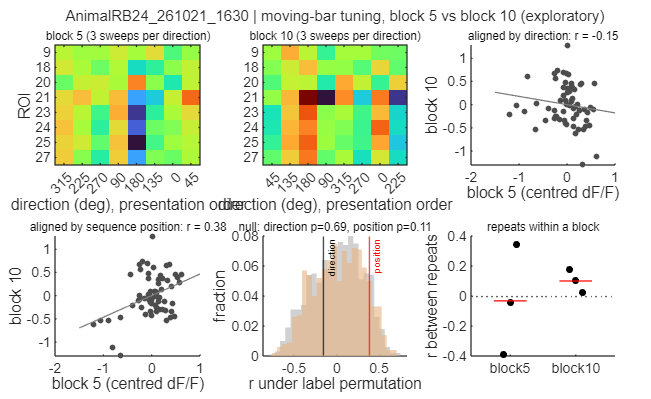

if do_bar
    Rb_ = resp.moving_bar;
    kbar = find(strcmp(b_type, 'moving_bar'))';
    dirs = unique(Rb_.dir(~isnan(Rb_.dir)));  nd = numel(dirs);
    ib   = Rb_.tcom >= awin.moving_bar(1) & Rb_.tcom <= awin.moving_bar(2);
    amp_b = reshape(mean(Rb_.Cb(sel_roi, ib, :), 2, 'omitnan'), nSel, []);       % [nSel x sweeps]
    orders = cell(1, numel(kbar));  rs = cell(1, numel(kbar));
    for q = 1:numel(kbar); orders{q} = reconstruct_direction_order(S(kbar(q)), 'bar_orientations'); rs{q} = S(kbar(q)).randomseed; end
    same_order = numel(kbar) >= 2 && isequal(orders{1}, orders{2});
    same_rng   = numel(kbar) >= 2 && isequal(rs{1}, rs{2});
    fprintf('15a block %d order %s | block %d order %s | identical order: %d, identical RNG state: %d\n', kbar(1), mat2str(orders{1}), kbar(min(2, end)), mat2str(orders{min(2, end)}), same_order, same_rng);
    ex = exadd(ex, '15a bar direction orders', 'same direction order in both blocks', same_order, sprintf('same RNG state: %d', same_rng), numel(kbar));
    ctr = @(M) M - mean(M, 2);
    tun = cell(1, numel(kbar));  tun_pos = tun;  amp_k = tun;  dir_k = tun;  tun_rep = tun;
    for q = 1:numel(kbar)
        ik = find(Rb_.blk == kbar(q));  amp_k{q} = amp_b(:, ik);  dir_k{q} = Rb_.dir(ik);
        tun{q} = nan(nSel, nd);  for d = 1:nd; tun{q}(:, d) = mean(amp_k{q}(:, dir_k{q} == dirs(d)), 2); end
        pos = mod(0:numel(ik)-1, nd) + 1;
        tun_pos{q} = nan(nSel, nd);  for d = 1:nd; tun_pos{q}(:, d) = mean(amp_k{q}(:, pos == d), 2); end
        nrep = floor(numel(ik) / nd);  tun_rep{q} = nan(nSel, nd, nrep);
        for r = 1:nrep; tun_rep{q}(:, :, r) = amp_k{q}(:, (r - 1) * nd + (1:nd)); end
    end
    rep_res = nan(1, 4);
    if numel(kbar) >= 2
        A1 = ctr(tun{1});  A2 = ctr(tun{2});
        r_dir = corr(A1(:), A2(:));
        P1 = ctr(tun_pos{1});  P2 = ctr(tun_pos{2});
        r_pos = corr(P1(:), P2(:));
        perms_ = zeros(n_boot, nd);  for b = 1:n_boot; perms_(b, :) = randperm(nd); end
        r_perm = arrayfun(@(b) corr(reshape(A1(:, perms_(b, :)), [], 1), A2(:)), 1:n_boot);
        nsh = setdiff(1:numel(dir_k{1}) - 1, nd:nd:numel(dir_k{1}));                % shifts that are not whole repeats
        r_shift = nan(1, numel(nsh));
        for j = 1:numel(nsh)
            dsh = circshift(dir_k{1}, nsh(j));
            T_ = nan(nSel, nd);  for d = 1:nd; T_(:, d) = mean(amp_k{1}(:, dsh == dirs(d)), 2); end
            Tc = ctr(T_);  r_shift(j) = corr(Tc(:), A2(:));
        end
        p_perm  = (1 + sum(r_perm >= r_dir)) / (n_boot + 1);
        p_shift = (1 + sum(r_shift >= r_dir)) / (numel(r_shift) + 1);
        r_pos_perm = arrayfun(@(b) corr(reshape(P1(:, perms_(b, :)), [], 1), P2(:)), 1:n_boot);              % same position labels permuted
        r_pos_rot  = arrayfun(@(j) corr(reshape(P1(:, circshift(1:nd, j)), [], 1), P2(:)), 1:nd-1);            % cycle rotated by 1..7 positions
        p_pos_perm = (1 + sum(r_pos_perm >= r_pos)) / (n_boot + 1);
        p_pos_rot  = (1 + sum(r_pos_rot >= r_pos)) / (nd - 1 + 1);
        rep_res = [r_dir r_pos p_perm p_shift p_pos_perm p_pos_rot];
        fprintf('15c tuning of block %d vs block %d: by direction r=%.2f (label-permutation p=%.3f, shifted-label p=%.3f, null %.2f+-%.2f) | by sequence position r=%.2f (permutation p=%.3f, rotation p=%.3f, null %.2f+-%.2f)\n', kbar(1), kbar(2), r_dir, p_perm, p_shift, mean(r_perm), std(r_perm), r_pos, p_pos_perm, p_pos_rot, mean(r_pos_perm), std(r_pos_perm));
        ex = exadd(ex, '15c bar tuning replication', sprintf('r(block %d vs block %d) by direction', kbar(1), kbar(2)), r_dir, sprintf('perm p=%.3f, shift p=%.3f', p_perm, p_shift), nSel * nd);
        ex = exadd(ex, '15c bar tuning replication', sprintf('r(block %d vs block %d) by sequence position', kbar(1), kbar(2)), r_pos, sprintf('perm p=%.3f, rotation p=%.3f', p_pos_perm, p_pos_rot), nSel * nd);
        % per group (8 directions each)
        for g = 1:ng
            a = mean(tun{1}(ismember(sel_roi, grp_rois{g}), :), 1);  b_ = mean(tun{2}(ismember(sel_roi, grp_rois{g}), :), 1);
            rg = corr(a', b_', 'Type', 'Spearman');
            fprintf('     %s: Spearman between the two blocks over %d directions %.2f\n', grp_lab{g}, nd, rg);
            ex = exadd(ex, ['15c bar tuning replication, ' grp_lab{g}], sprintf('Spearman block %d vs %d over directions', kbar(1), kbar(2)), rg, '', nd);
        end
    end
    % within-block repeats (the order repeats exactly, so these replicate the sequence-locked pattern, not the direction by itself)
    for q = 1:numel(kbar)
        rr = [];  for a = 1:size(tun_rep{q}, 3) - 1; for b = a + 1:size(tun_rep{q}, 3); x1 = ctr(tun_rep{q}(:, :, a));  x2 = ctr(tun_rep{q}(:, :, b));  rr(end+1) = corr(x1(:), x2(:)); end; end %#ok<SAGROW>
        fprintf('15c block %d: tuning correlation between repeats %s\n', kbar(q), mat2str(round(rr, 2)));
        ex = exadd(ex, ['15c bar tuning, block ' num2str(kbar(q))], 'r between repeats (mean of pairs)', mean(rr), mat2str(round(rr, 2)), numel(rr));
    end
    % 15d  behaviour per direction
    bar_beh = reshape(mean(Rb_.Bal(:, ib, :), 2, 'omitnan'), numel(beh_names), []);
    for bq = 1:numel(beh_names)
        p_kw = kruskalwallis(bar_beh(bq, :), Rb_.dir, 'off');
        fprintf('15d evoked %s differs between bar directions: Kruskal-Wallis p=%.3f\n', beh_names{bq}, p_kw);
        ex = exadd(ex, '15d behaviour per bar direction', ['Kruskal-Wallis p, ' beh_names{bq}], p_kw, '', size(bar_beh, 2));
    end
    % ---- figure 07
    if numel(kbar) >= 2
        fh = newfig('Bar tuning replication', 18, 11);
        tl = tiledlayout(fh, 2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
        title(tl, sprintf('%s | moving-bar tuning, block %d vs block %d (exploratory)', session, kbar(1), kbar(2)), 'FontSize', 9, 'FontWeight', 'normal', 'Interpreter', 'none');
        clm = max(0.3, prctile(abs([tun{1}(:); tun{2}(:)]), 98));  roi_l = string(sel_roi);
        for q = 1:2
            a = nexttile(tl, q);  imagesc(a, tun{q});  clim(a, [-clm clm]);  colormap(a, turbo);
            xticks(a, 1:nd);  xticklabels(a, string(orders{q}));  xlabel(a, 'direction (deg), presentation order');  yticks(a, 1:nSel);  yticklabels(a, roi_l);
            if q == 1; ylabel(a, 'ROI'); end
            title(a, sprintf('block %d (3 sweeps per direction)', kbar(q)), 'FontSize', 7, 'FontWeight', 'normal');
        end
        a = nexttile(tl, 3);  hold(a, 'on');
        scatter(a, A1(:), A2(:), 12, [0.3 0.3 0.3], 'filled');  lsline(a);
        xlabel(a, sprintf('block %d (centred dF/F)', kbar(1)));  ylabel(a, sprintf('block %d', kbar(2)));  title(a, sprintf('aligned by direction: r = %.2f', rep_res(1)), 'FontSize', 7, 'FontWeight', 'normal');
        a = nexttile(tl, 4);  hold(a, 'on');
        scatter(a, P1(:), P2(:), 12, [0.3 0.3 0.3], 'filled');  lsline(a);
        xlabel(a, sprintf('block %d (centred dF/F)', kbar(1)));  ylabel(a, sprintf('block %d', kbar(2)));  title(a, sprintf('aligned by sequence position: r = %.2f', rep_res(2)), 'FontSize', 7, 'FontWeight', 'normal');
        a = nexttile(tl, 5);  hold(a, 'on');
        histogram(a, r_perm, 25, 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none', 'Normalization', 'probability');
        histogram(a, r_pos_perm, 25, 'FaceColor', [0.9 0.7 0.5], 'EdgeColor', 'none', 'Normalization', 'probability');
        xline(a, rep_res(1), 'k-', 'direction', 'FontSize', 6);  xline(a, rep_res(2), 'r-', 'position', 'FontSize', 6);
        xlabel(a, 'r under label permutation');  ylabel(a, 'fraction');  title(a, sprintf('null: direction p=%.2f, position p=%.2f', rep_res(3), rep_res(5)), 'FontSize', 7, 'FontWeight', 'normal');
        a = nexttile(tl, 6);  hold(a, 'on');
        for q = 1:numel(kbar)
            rr = [];  for i1 = 1:size(tun_rep{q}, 3) - 1; for i2 = i1 + 1:size(tun_rep{q}, 3); x1 = ctr(tun_rep{q}(:, :, i1));  x2 = ctr(tun_rep{q}(:, :, i2));  rr(end+1) = corr(x1(:), x2(:)); end; end %#ok<SAGROW>
            scatter(a, q + linspace(-0.1, 0.1, numel(rr)), rr, 18, 'k', 'filled');  plot(a, q + [-0.25 0.25], mean(rr) * [1 1], 'r-');
        end
        yline(a, 0, ':');  xticks(a, 1:numel(kbar));  xticklabels(a, strcat('block ', string(kbar)));  xlim(a, [0.4 numel(kbar) + 0.6]);  ylabel(a, 'r between repeats');  title(a, 'repeats within a block', 'FontSize', 7, 'FontWeight', 'normal');
        if save_figs; savef(fh, '07_bar_tuning_replication'); end
    end
end

## 16. Summary

if explore_stats
    fprintf('\n================ exploration summary (exploratory, one session) ================\n');
    for i = 1:size(ex, 1)
        v = ex{i, 3};  if isnumeric(v) || islogical(v); vs = sprintf('%.3g', v); else; vs = char(v); end
        fprintf('%-62s | %-58s | %10s | %s (n=%s)\n', ex{i, 1}, ex{i, 2}, vs, ex{i, 4}, num2str(ex{i, 5}));
    end
    explore_tbl = table(string(ex(:, 1)), string(ex(:, 2)), string(cellfun(@(v) num2str(v, 3), ex(:, 3), 'UniformOutput', false)), string(ex(:, 4)), cell2mat(ex(:, 5)), ...
        'VariableNames', {'analysis', 'statistic', 'value', 'ci_or_p', 'n'});
    if save_figs; writetable(explore_tbl, fullfile(fig_dir, 'explore_findings.csv')); end
end


================ exploration summary (exploratory, one session) ================


13c dose-response, ROI 18,23,24,25,27                          | extra dF/F of a flash at equal whisking                    |    -0.0242 | [-0.44, 0.60] (n=88)
13c dose-response, ROI 18,23,24,25,27                          | extra dF/F of a looming trial at equal whisking            |     -0.167 | [-0.68, 0.61] (n=88)
13c dose-response, ROI 9                                       | extra dF/F of a flash at equal whisking                    |    -0.0775 | [-0.31, 0.25] (n=88)
13c dose-response, ROI 9                                       | extra dF/F of a looming trial at equal whisking            |     -0.269 | [-0.54, 0.13] (n=88)
13c dose-response, ROI 20                                      | extra dF/F of a flash at equal whisking                    |     -0.119 | [-0.50, 0.16] (n=88)
13c dose-response, ROI 20                                      | extra dF/F of a looming trial at equal whisking            |     0.0185 | [-0.55, 0.40] (n=88)
13c dose-response, ROI 21               

## local functions

function save_fig(fh, base)
% PNG (300 dpi) and vector PDF of a figure
exportgraphics(fh, [base '.png'], 'Resolution', 300);
exportgraphics(fh, [base '.pdf'], 'ContentType', 'vector');
end

function [gid, grp_rois] = roi_groups(dsm, sel_roi, thr)
% cluster the selected ROIs on the correlation of their smoothed dF/F (average linkage, cut at 1 - thr); group 1 = the largest group
nSel = numel(sel_roi);
ds = double(dsm(sel_roi, :));
if nSel >= 2; gid = cluster(linkage(pdist(ds, 'correlation'), 'average'), 'cutoff', 1 - thr, 'criterion', 'distance'); else; gid = ones(nSel, 1); end
gid = gid(:)';
gsz = accumarray(gid(:), 1)';  gmn = accumarray(gid(:), sel_roi(:), [], @min)';
[~, gord] = sort(-1000 * gsz + gmn);
[~, gid] = ismember(gid, gord);
grp_rois = arrayfun(@(g) sel_roi(gid == g), 1:max(gid), 'UniformOutput', false);
end

function [rel, p_rel] = trial_reliability(Cb, tcom, grp, n_perm)
% Reliability of the responses across trials: mean pairwise correlation between the trials (within each group of grp, e.g. each bar direction) of the
% baseline-subtracted dF/F from the onset on, per ROI, tested against independently circularly shifted trials (n_perm)
pm   = @(M) mean(nonzeros(tril(corrcoef(M, 'Rows', 'pairwise'), -1)), 'omitnan');
nROI = size(Cb, 1);  ridx = find(tcom >= 0);
rel = nan(nROI, 1);  p_rel = nan(nROI, 1);
for r = 1:nROI
    Mr = squeeze(Cb(r, ridx, :));                                                   % [time x trials]
    rel(r) = mean(arrayfun(@(g) pm(Mr(:, grp == g)), unique(grp)), 'omitnan');
    nul = zeros(1, n_perm);
    for p = 1:n_perm
        sh  = randi(numel(ridx), 1, size(Mr, 2));
        Ms  = Mr(sub2ind(size(Mr), mod((0:numel(ridx)-1)' + sh, numel(ridx)) + 1, repmat(1:size(Mr, 2), numel(ridx), 1)));
        nul(p) = mean(arrayfun(@(g) pm(Ms(:, grp == g)), unique(grp)), 'omitnan');
    end
    p_rel(r) = (1 + sum(nul >= rel(r))) / (n_perm + 1);
end
end

function st = prepost_stats(Xpre, Xpost, n_boot)
% Change between a pre and a post window of several blocks (section 9b). Xpre, Xpost [blocks x chunks]: one value per chunk of the window.
%   delta  mean over the blocks of (mean of the post chunks - mean of the pre chunks)
%   ci     95% bootstrap interval of delta (chunks resampled with replacement inside each window of each block)
%   p      two-sided, from exchanging the pre / post labels of the chunks inside each block (n_boot random exchanges)
%   ref    the same delta between the second and the first half of the PRE window (nothing happened in between: the scale of drift / arousal change)
%   d_blk  delta of every block
[nb, nc] = size(Xpre);
mm   = @(X) mean(X, 2, 'omitnan');
d_blk = mm(Xpost) - mm(Xpre);
obs  = mean(d_blk, 'omitnan');
bi   = repmat((1:nb)', 1, nc);
bs   = zeros(n_boot, 1);
for b = 1:n_boot
    a = Xpre(sub2ind([nb nc], bi, randi(nc, nb, nc)));  c = Xpost(sub2ind([nb nc], bi, randi(nc, nb, nc)));
    bs(b) = mean(mm(c) - mm(a), 'omitnan');
end
Xall = [Xpre Xpost];  bi2 = repmat((1:nb)', 1, 2 * nc);  pn = zeros(n_boot, 1);
for b = 1:n_boot
    [~, o] = sort(rand(nb, 2 * nc), 2);
    Xp = Xall(sub2ind([nb 2 * nc], bi2, o));
    pn(b) = mean(mm(Xp(:, nc+1:end)) - mm(Xp(:, 1:nc)), 'omitnan');
end
h = floor(nc / 2);
p = (1 + sum(abs(pn) >= abs(obs))) / (n_boot + 1);
if ~isfinite(obs); p = NaN; end
st = struct('pre', mean(mm(Xpre), 'omitnan'), 'post', mean(mm(Xpost), 'omitnan'), 'delta', obs, 'ci', prctile(bs, [2.5 97.5]), 'p', p, ...
    'ref', mean(mm(Xpre(:, nc-h+1:end)) - mm(Xpre(:, 1:h)), 'omitnan'), 'd_blk', d_blk');
end

function R = whisk_resid(Y, W)
% residual of Y after a linear fit on W over all finite pairs (any equal-sized arrays of chunk values); NaN when there are fewer than 10 pairs
R = nan(size(Y));  m = isfinite(Y) & isfinite(W);
if nnz(m) < 10 || std(W(m)) == 0; return; end
p = polyfit(W(m), Y(m), 1);
R = Y - polyval(p, W);
end

function shade_trace(ax, t, M, c, show_rep, lw)
% mean over the columns of M [time x repeats] as a thick line (width lw, default 1.8), +- SD across repeats as a cloud, single repeats in grey if show_rep
if nargin < 6; lw = 1.8; end
mu = mean(M, 2, 'omitnan');  sd = std(M, 0, 2, 'omitnan');
t = t(:);  mu = mu(:);  sd = sd(:);
ok = isfinite(mu) & isfinite(sd);
hold(ax, 'on');
if show_rep; plot(ax, t, M, 'Color', [0.88 0.88 0.88], 'LineWidth', 0.3); end
fill(ax, [t(ok); flipud(t(ok))], [mu(ok) + sd(ok); flipud(mu(ok) - sd(ok))], c, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(ax, t, mu, 'Color', c, 'LineWidth', lw);
end

function s = spear_str(x, y)
% Spearman rho and p of two vectors (pairs with a NaN are dropped), as a title string
x = x(:);  y = y(:);  v = isfinite(x) & isfinite(y);
if sum(v) < 4; s = 'n/a'; return; end
[r, p] = corr(x(v), y(v), 'Type', 'Spearman');
if p < 0.001; ps = 'p < 0.001'; else; ps = sprintf('p = %.3f', p); end
s = sprintf('\\rho = %.2f, %s (n = %d)', r, ps, sum(v));
end

function split_plot(ax, t, M, st, c)
% mean +- SEM of the columns of M [time x trials] for the trials below / above the median of the state vector st (grey / colour c)
v = isfinite(st);  hold(ax, 'on');
if sum(v) < 4; text(ax, 0.5, 0.5, 'n/a', 'Units', 'normalized', 'HorizontalAlignment', 'center', 'FontSize', 7, 'Color', [0.4 0.4 0.4]); return; end
m = median(st(v));  t = t(:);
for q = 1:2
    if q == 1; k = v & st <= m;  cc = [0.55 0.55 0.55]; else; k = v & st > m;  cc = c; end
    if sum(k) < 2; continue; end
    mu = mean(M(:, k), 2, 'omitnan');  se = std(M(:, k), 0, 2, 'omitnan') / sqrt(sum(k));
    fill(ax, [t; flipud(t)], [mu + se; flipud(mu - se)], cc, 'FaceAlpha', 0.25, 'EdgeColor', 'none');
    plot(ax, t, mu, 'Color', cc, 'LineWidth', 1.5);
end
xline(ax, 0, ':', 'Color', [0.5 0.5 0.5]);
end

function plabel(fh, FW, FH, x, y, s)
% bold panel letter with its top-left corner at (x, y) cm from the bottom-left of the figure
annotation(fh, 'textbox', [x / FW, (y - 0.6) / FH, 1.2 / FW, 0.6 / FH], 'String', s, 'EdgeColor', 'none', 'FontWeight', 'bold', 'FontSize', 10, 'FontName', 'Arial', 'Margin', 0, 'VerticalAlignment', 'top');
end

function r = xc_lags(X, y, seg, lags)
% correlation of every row of X with y at each lag; X (rows) and y are z-scored over the epoch, which is the concatenation of the
% segments seg (rows [first last] sample), and pairs are only formed inside a segment. Positive lag = X follows y.
n = sum(seg(:, 2) - seg(:, 1) + 1);
r = zeros(size(X, 1), numel(lags));
for li = 1:numel(lags)
    lg = lags(li);  acc = zeros(size(X, 1), 1);
    for s = 1:size(seg, 1)
        a = seg(s, 1);  b = seg(s, 2);
        if lg >= 0; xa = X(:, a+lg:b); ya = y(a:b-lg); else; xa = X(:, a:b+lg); ya = y(a-lg:b); end
        acc = acc + xa * ya';
    end
    r(:, li) = acc / (n - 1);
end
end

function b = slope_of(x, y)
p = polyfit(x(:), y(:), 1);  b = p(1);
end

function h = sem_trace(ax, t, M, c, band)
% mean over the columns of M [time x events] (line, returned handle), +- SEM as a cloud if band
t = t(:);  mu = mean(M, 2, 'omitnan');  se = std(M, 0, 2, 'omitnan') / sqrt(size(M, 2));
hold(ax, 'on');
ok = isfinite(mu) & isfinite(se);
if band; fill(ax, [t(ok); flipud(t(ok))], [mu(ok) + se(ok); flipud(mu(ok) - se(ok))], c, 'FaceAlpha', 0.2, 'EdgeColor', 'none'); end
h = plot(ax, t, mu, 'Color', c, 'LineWidth', 1.2);
end

function [mag, th] = rise_stats(t, y, pkwin)
% amplitude (peak minus baseline) and half-maximum rise time (s, linear interpolation) of one event trace y(t); baseline = [-1, -0.1] s;
% th is NaN when the peak does not exceed 3 SD of the baseline noise
t = t(:)';  y = y(:)';
bi = t >= -1 & t < -0.1;  b = mean(y(bi), 'omitnan');  sd = std(y(bi), 'omitnan');
pw = find(t >= pkwin(1) & t <= pkwin(2));
[pk, k] = max(y(pw));  ipk = pw(k);
mag = pk - b;  th = NaN;
if ~(isfinite(mag) && mag > 3 * sd); return; end
half = b + 0.5 * mag;
seg = find(t >= 0, 1):ipk;
j = find(y(seg) >= half, 1);
if isempty(j); return; end
if j == 1; th = t(seg(1)); else; th = interp1(y(seg([j-1 j])), t(seg([j-1 j])), half); end
end

function X = box_lags(x, js, w)
% regressors: for each tap j the mean of x over the w samples [t - j*w - (w-1), t - j*w] (j > 0 past, j < 0 future); NaN where undefined
x = x(:)';  nT = numel(x);
m = movmean(x, [w - 1 0]);  m(1:w-1) = NaN;
X = nan(nT, numel(js));
for q = 1:numel(js)
    s = js(q) * w;
    if s >= 0; X(s+1:end, q) = m(1:nT-s); else; X(1:nT+s, q) = m(1-s:end); end
end
end

function X = stim_reg(ons, tCa, js, w)
% boxcar-basis regressors of a stimulus: impulse at the nearest imaging frame of every onset, lagged like box_lags
imp = zeros(1, numel(tCa));
if ~isempty(ons); imp(unique(interp1(tCa, 1:numel(tCa), ons, 'nearest', 'extrap'))) = 1; end
X = box_lags(imp, js, w);
end

function on2 = shift_in_blocks(ons, t0, t1)
% circularly shift the onsets inside their own block by a random offset (keeps the trial spacing, destroys the timing against the data)
on2 = ons;
for k = 1:numel(t0)
    ii = ons >= t0(k) & ons <= t1(k);
    if ~any(ii); continue; end
    dur = t1(k) - t0(k);  d = (0.2 + 0.6 * rand) * dur;
    on2(ii) = t0(k) + mod(ons(ii) - t0(k) + d, dur);
end
end

function [sse, sst] = cv_ridge(Y, X, blk_f, lam_frac)
% leave-one-block-out ridge regression. Y [nT x nG], X [nT x p], blk_f block index per sample (0 = outside a block). Returns SSE and SST [nBlocks x nG]
% of every held-out block (SST around the training mean); ridge penalty = lam_frac x number of training samples on standardised columns
nB = max(blk_f);  nG = size(Y, 2);  sse = nan(nB, nG);  sst = nan(nB, nG);
ok = all(isfinite(X), 2) & all(isfinite(Y), 2) & blk_f > 0;
for k = 1:nB
    te = ok & blk_f == k;  tr = ok & blk_f ~= k;
    if nnz(te) < 30; continue; end
    mu = mean(X(tr, :), 1);  sd = std(X(tr, :), 0, 1);  sd(sd == 0) = 1;
    Xtr = (X(tr, :) - mu) ./ sd;  Xte = (X(te, :) - mu) ./ sd;
    ym  = mean(Y(tr, :), 1);
    B = (Xtr' * Xtr + lam_frac * nnz(tr) * eye(size(X, 2))) \ (Xtr' * (Y(tr, :) - ym));
    e = (Y(te, :) - ym) - Xte * B;
    sse(k, :) = sum(e .^ 2, 1);  sst(k, :) = sum((Y(te, :) - ym) .^ 2, 1);
end
end

function [m, tb] = pool_bin(T, Y, edges)
% mean of Y over all samples whose relative time T falls in each bin (flashes pooled at random frame phases)
b = discretize(T(:), edges);  v = Y(:);  ok = ~isnan(b) & isfinite(v);
nb = numel(edges) - 1;
s = accumarray(b(ok), v(ok), [nb 1]);  c = accumarray(b(ok), 1, [nb 1]);
m = (s ./ c)';  tb = (edges(1:end-1) + edges(2:end)) / 2;
end

function k = kin_stats(tb, m)
% onset (first of 3 consecutive bins above 3 SD of the pre-stimulus bins), 10-90% rise time and peak of a binned mean trace; NaN when there is no response
k = struct('onset', NaN, 'rise', NaN, 'peak_t', NaN, 'peak', NaN);
bs = tb < -0.1;  sd = std(m(bs), 'omitnan');  b = mean(m(bs), 'omitnan');
ms = movmean(m - b, 3, 'omitnan');
pw = find(tb >= 0 & tb <= 2);
[pk, i] = max(ms(pw));  ipk = pw(i);
k.peak = pk;  k.peak_t = tb(ipk);
if ~(pk > 3 * sd); return; end
above = (m - b) > 3 * sd;
on = find(above(1:end-2) & above(2:end-1) & above(3:end) & tb(1:end-2) >= 0, 1);
if ~isempty(on); k.onset = tb(on); end
seg = find(tb >= 0 & tb <= tb(ipk));
c10 = find(ms(seg) >= 0.1 * pk, 1);  c90 = find(ms(seg) >= 0.9 * pk, 1);
if ~isempty(c10) && ~isempty(c90); k.rise = tb(seg(c90)) - tb(seg(c10)); end
end